# 데이타 읽어 들이기.

%['ap:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-05-12_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2017-06-30_batchdata_updated_struct_errorcorrect.mat',
%           'C:/nobackup/_phd_work/_battery_soh/_dataset/data.matr.io/2018-04-12_batchdata_updated_struct_errorcorrect.mat']

clear ;
close all;

batchNum = 1;
load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-05-12_batchdata_updated_struct_errorcorrect.mat
trainData = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2017-06-30_batchdata_updated_struct_errorcorrect.mat
trainData2 = batch;
clear batch
clear batch_date

load C:\nobackup\_phd_work\_battery_soh\_dataset\data.matr.io\2018-04-12_batchdata_updated_struct_errorcorrect.mat
trainData3 = batch;
clear batch
clear batch_date

# 기본 데이타 분석

i=3 

i = 3

policy = trainData(i).policy 

policy = '3_6C-80PER_3_6C'

policy_readable = trainData(i).policy_readable 

policy_readable = '3.6C(80%)-3.6C'

channel_id = trainData(i).channel_id

channel_id = "3"

cycle_life = trainData(i).cycle_life

cycle_life = 1177

chargetime = trainData(i).summary.chargetime

chargetime =          0
   13.3414
   13.3415
   13.4258
   13.3412
   13.3413
   13.4257
   13.4256
   13.3414
   13.3413


cycle = trainData(i).summary.cycle

cycle =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


IR = trainData(i).summary.IR

IR =          0
    0.0169
    0.0168
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167
    0.0167


QCharge = trainData(i).summary.QCharge

QCharge =          0
    1.0798
    1.0811
    1.0819
    1.0825
    1.0828
    1.0831
    1.0834
    1.0835
    1.0836


QDischarge = trainData(i).summary.QDischarge

QDischarge =          0
    1.0799
    1.0813
    1.0822
    1.0827
    1.0830
    1.0833
    1.0837
    1.0837
    1.0838


Vdlin = trainData(i).Vdlin

Vdlin =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


trainData(i).Vdlin

ans =     3.5000
    3.4985
    3.4970
    3.4955
    3.4940
    3.4925
    3.4910
    3.4895
    3.4880
    3.4865


cycleNum = 2

cycleNum = 2

cycleNum1 = 100

cycleNum1 = 100

size ( trainData(3).cycles(2).t )

ans =         1124           1


trainData(3).cycles(2).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


% trainData(3).cycles(1).t(2:3,:)
 
trainData(3).cycles(cycleNum).t 

ans =          0
    0.0025
    0.0029
    0.0032
    0.0036
    0.0040
    0.0043
    0.0045
    0.0048
    0.0051


# 그래프로 확인

# 전체 전류 ( 충/방전 )

#### 테스트 환경 설정

test_bat = 6 ;
cycle_div = 500;

# 측정 포인트 대비 시간 - 1:1 이 아니다.

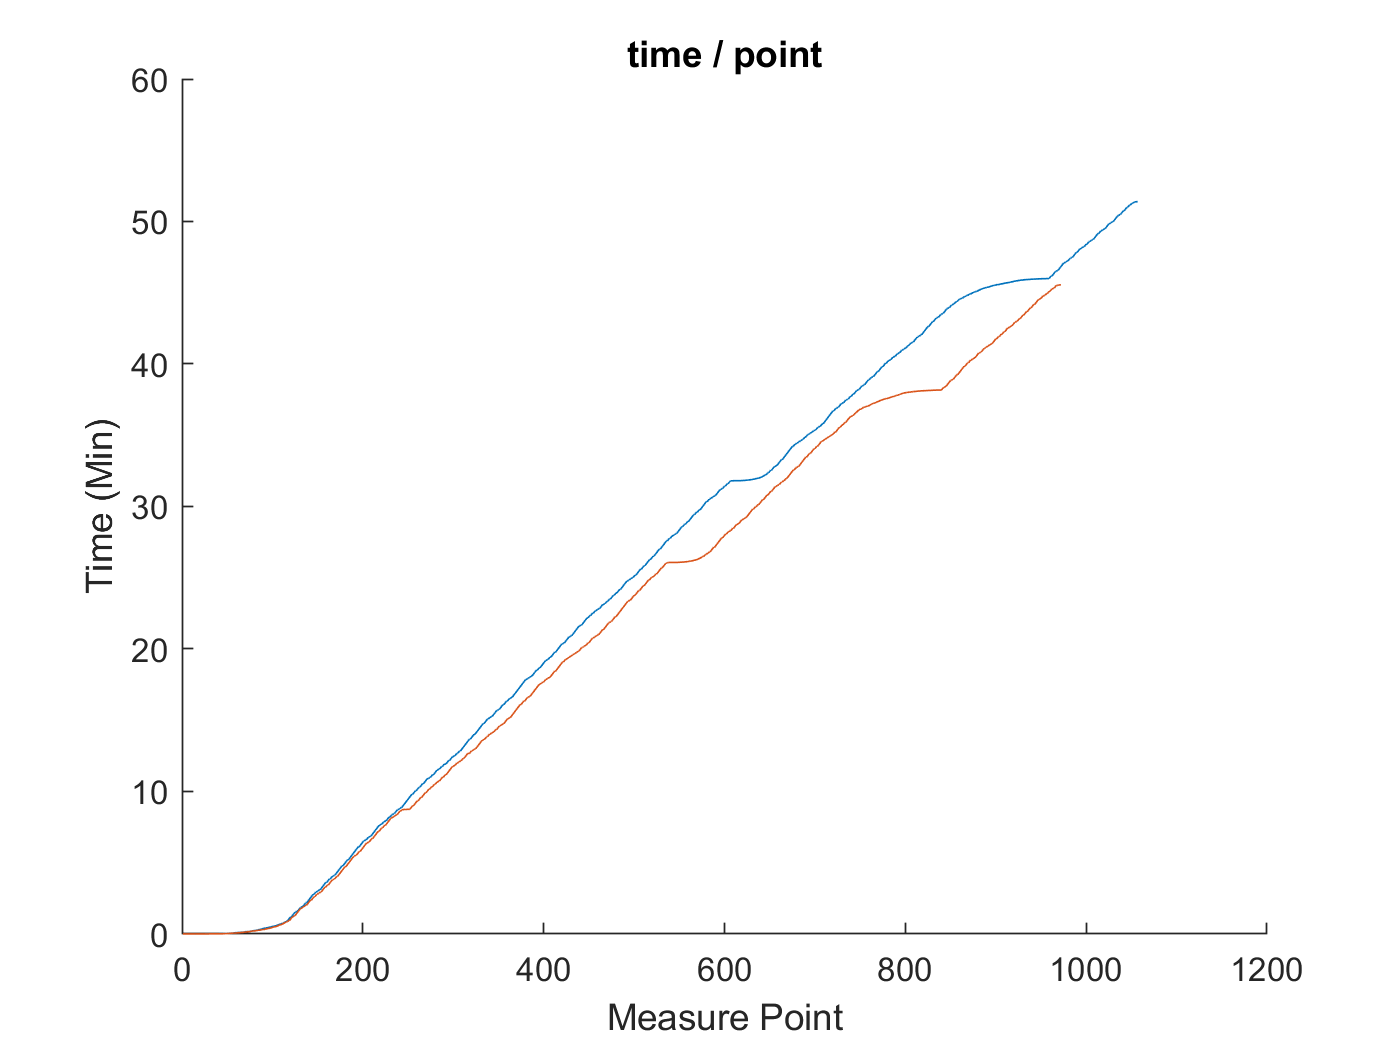

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t)
    end
end
hold off , xlabel 'Measure Point' , ylabel 'Time (Min)' , title 'time / point'

#### Charge Q / Meature Point

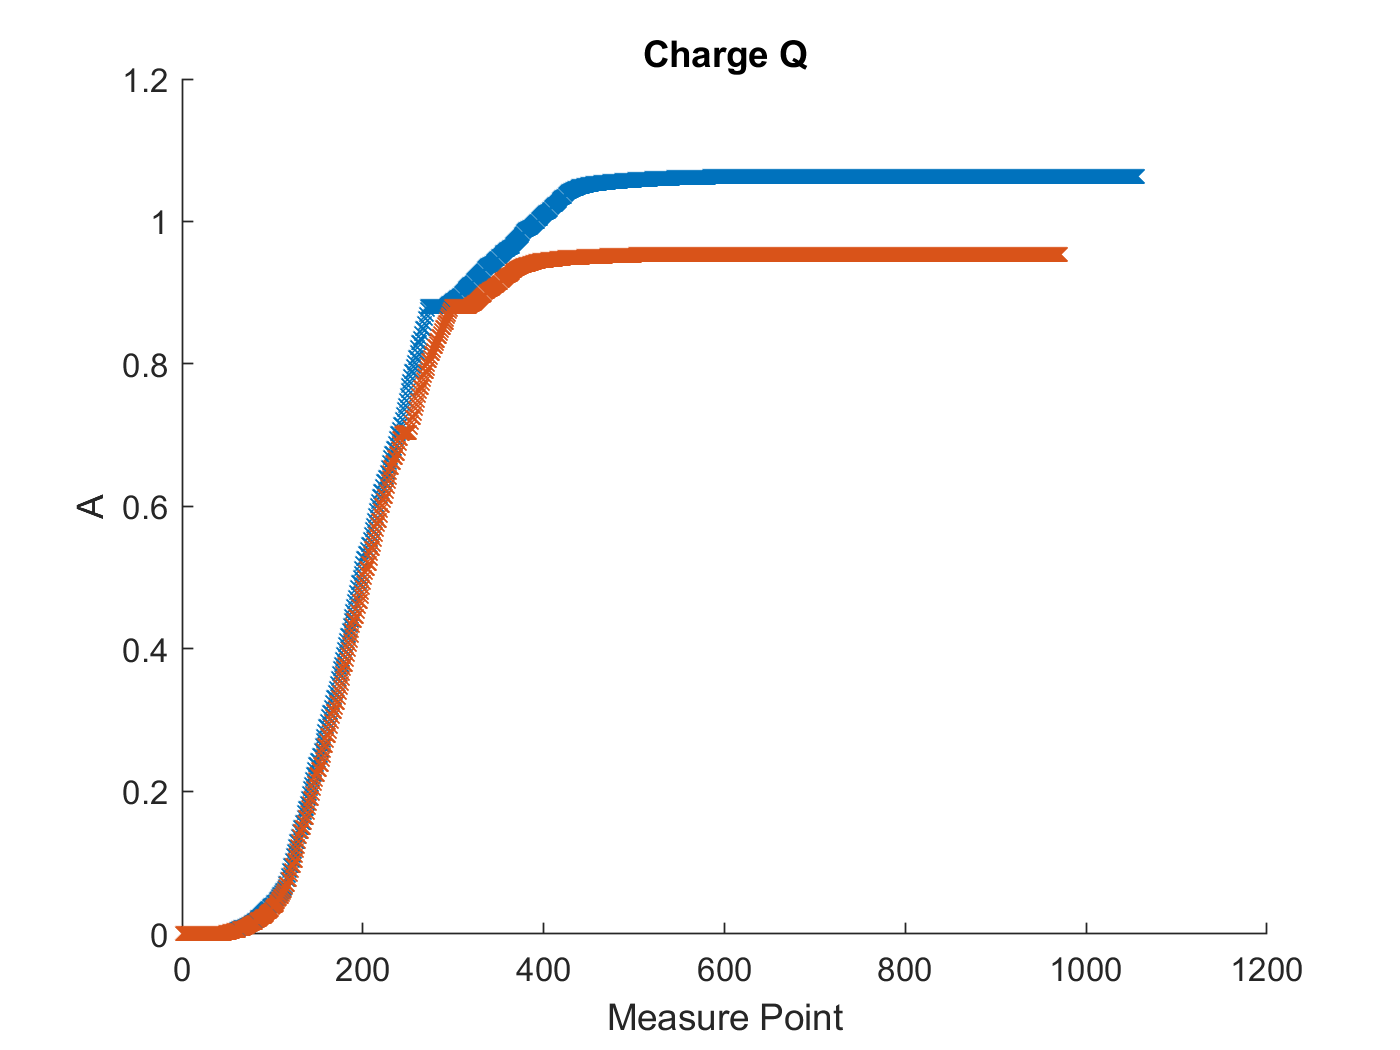


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Q'

#### Charge Q / Time

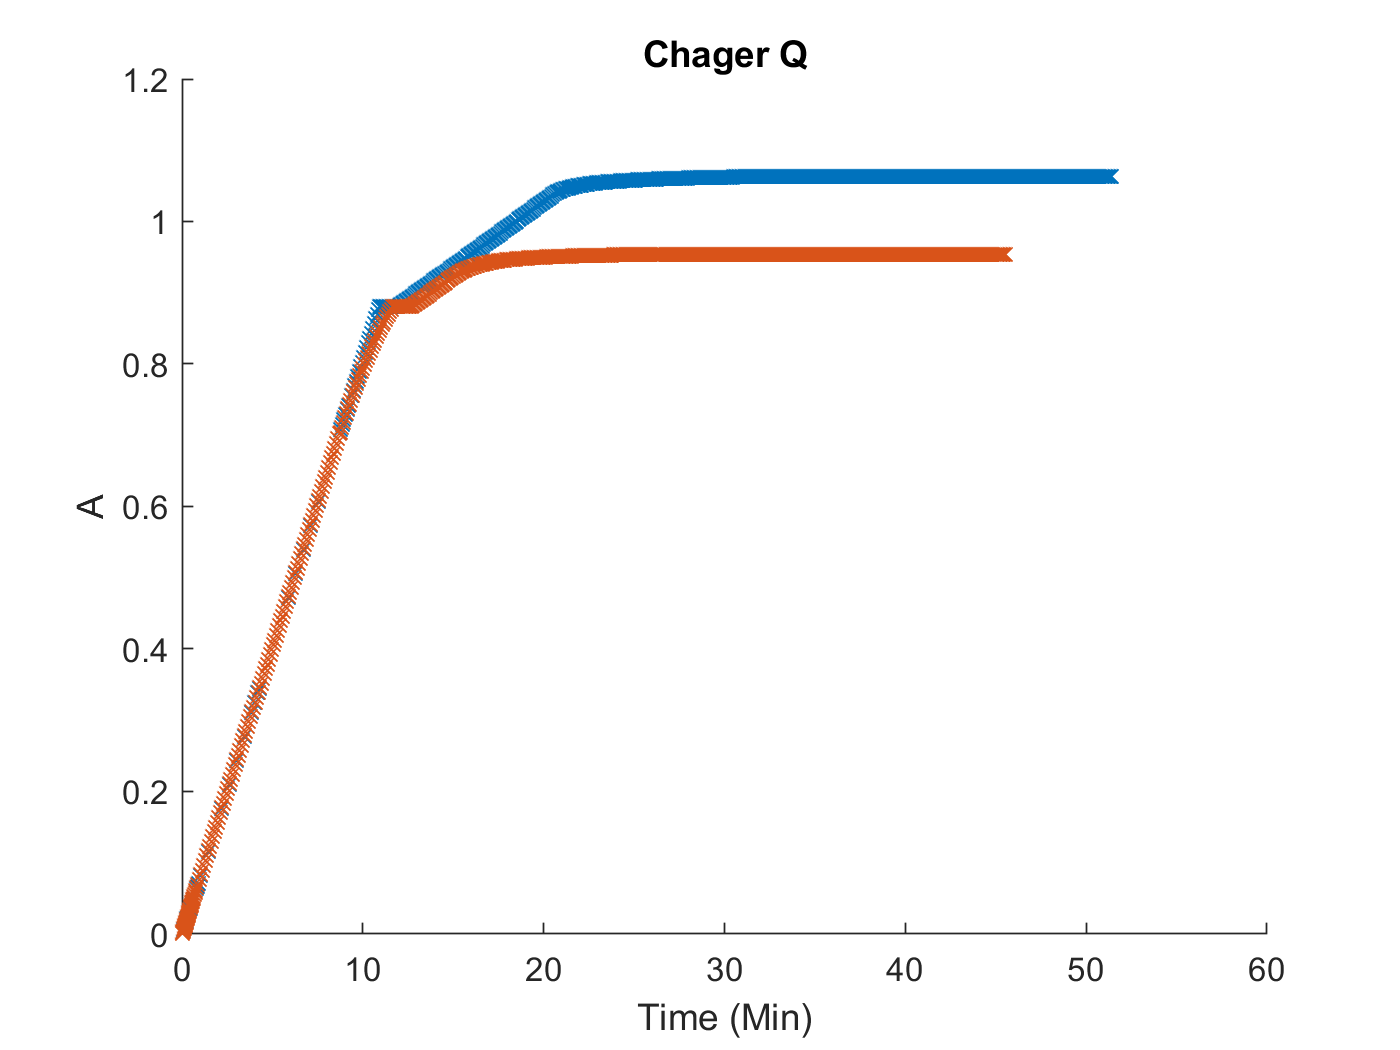

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Chager Q'

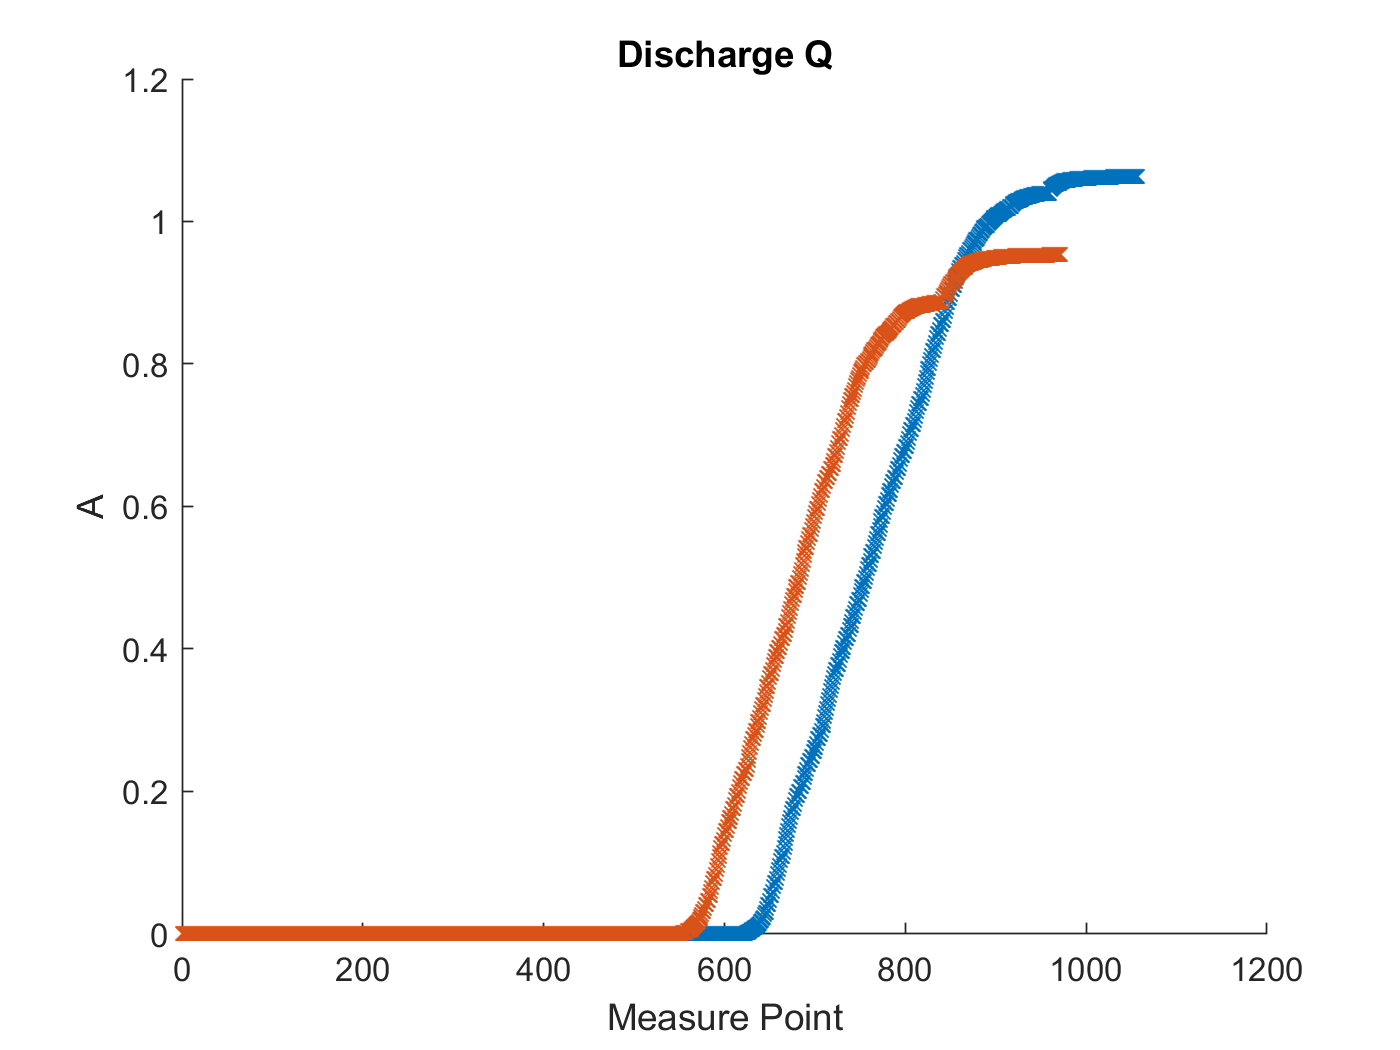

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Discharge Q'

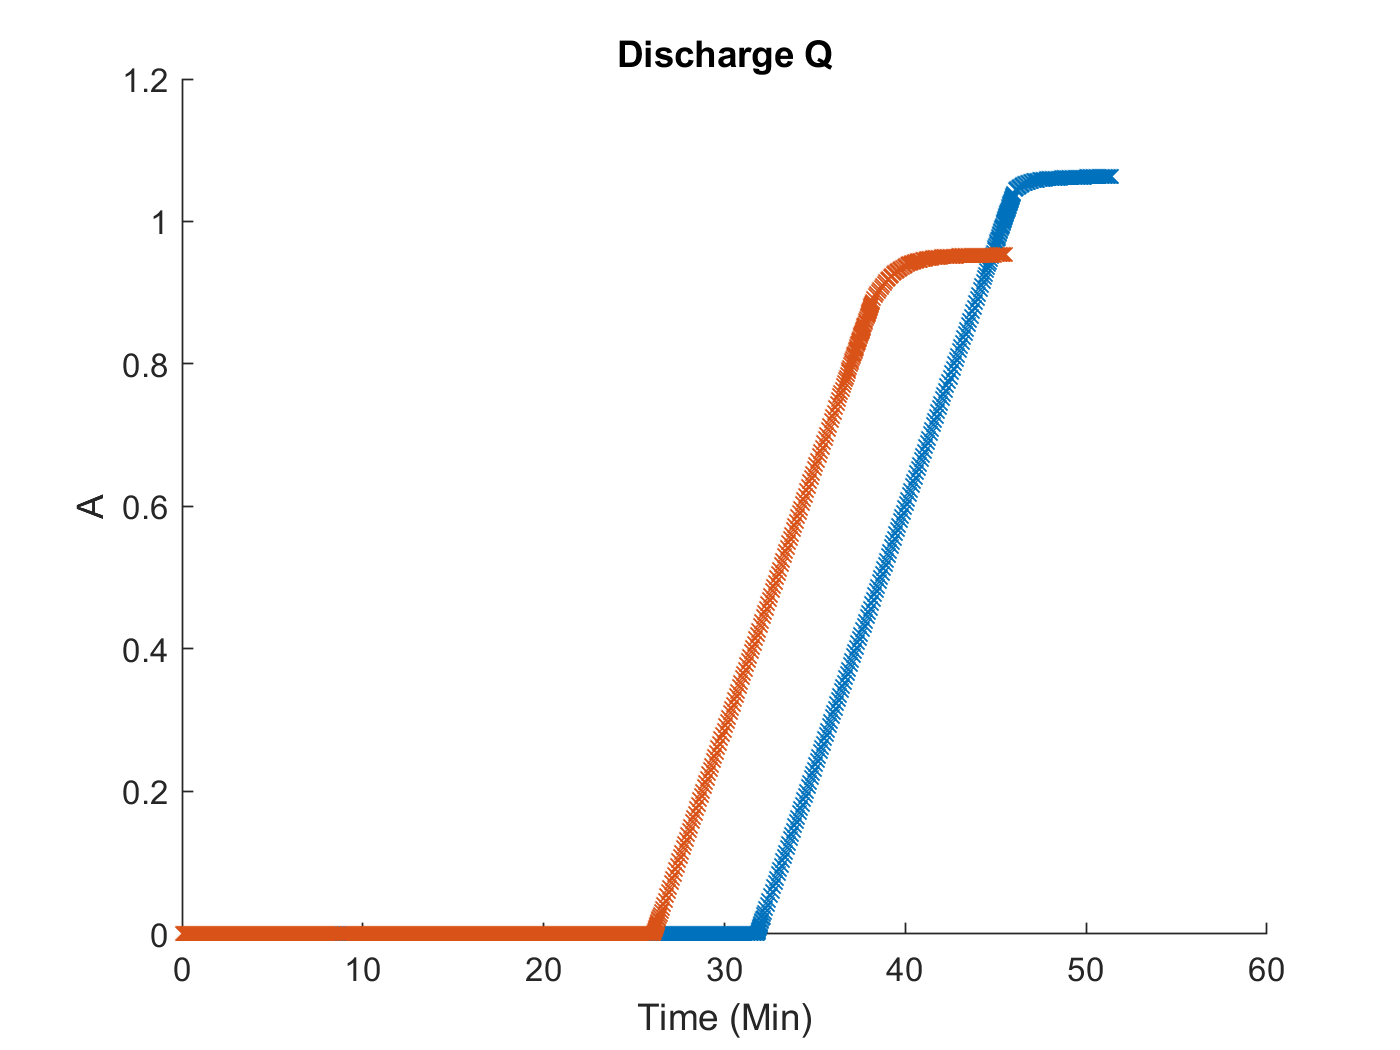


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'x')
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Discharge Q'

#### Qc 와 Qd 를 보면 이를 통해 충전 사이클과 방전 사이클을 확인할 수 있다.

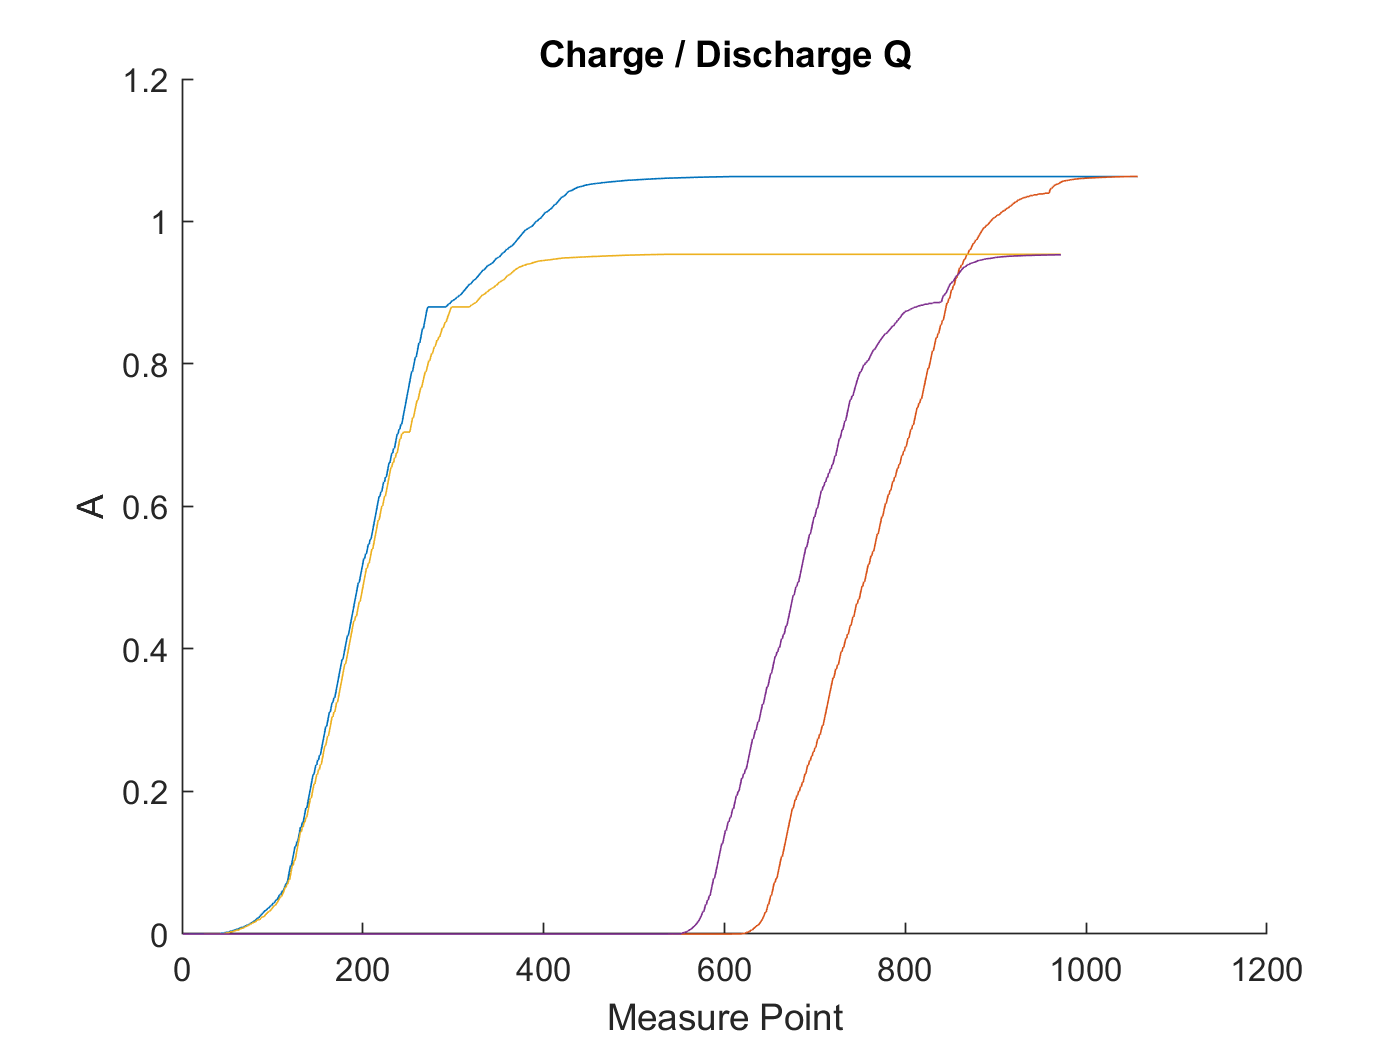

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

# 충전 전류 분석

#### I는 충방전 전체 사이클에 대한 정보이다.

#### 충전시와 방전시로 분리하자.

#### Measure Point 는 Cycle 이 증가할 수로 줄어든다.

#### Measure Time 는 Cycle 이 증가할 수로 줄어든다.

#### x 축의 마지막 값이 cycle 에 따라 달라지면 이를 이용하기 힘들다.

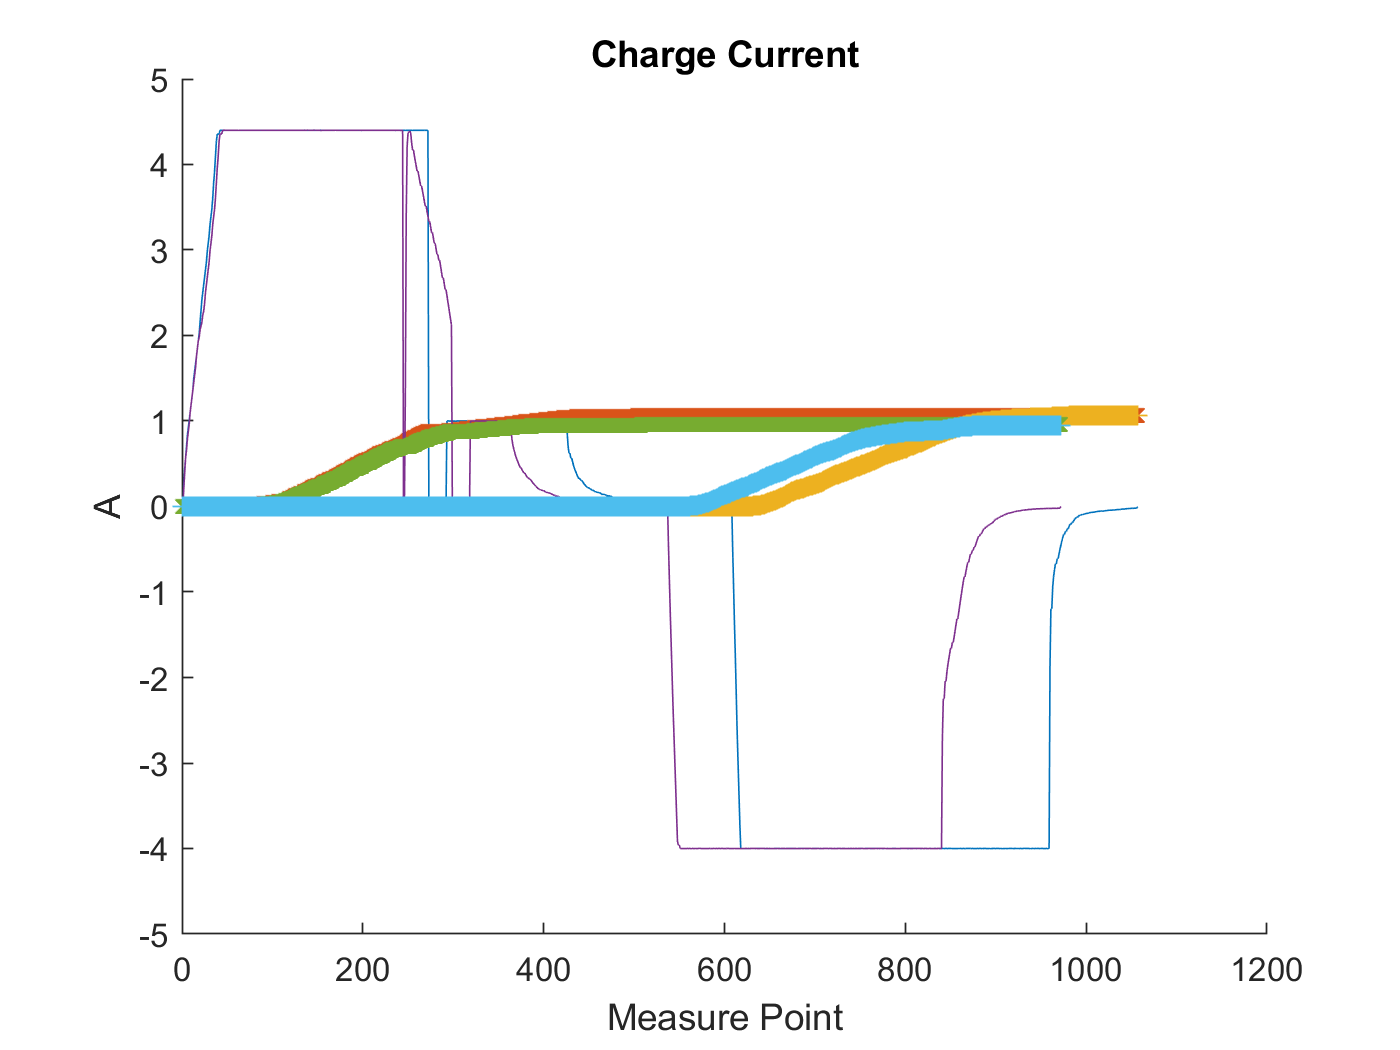

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Current'

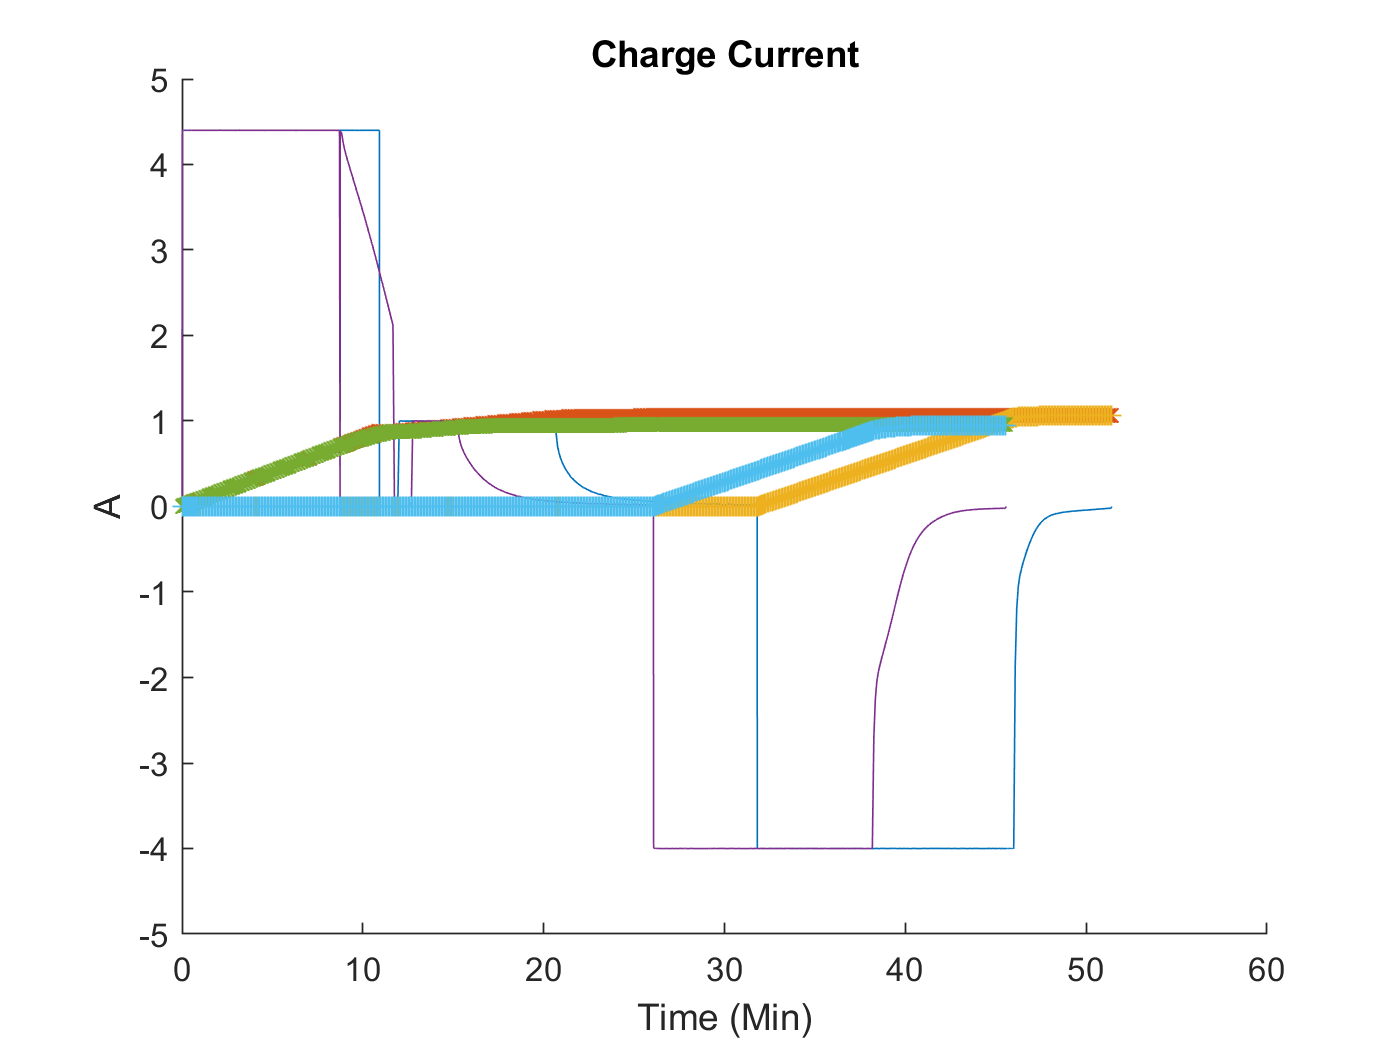

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).I)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Current'

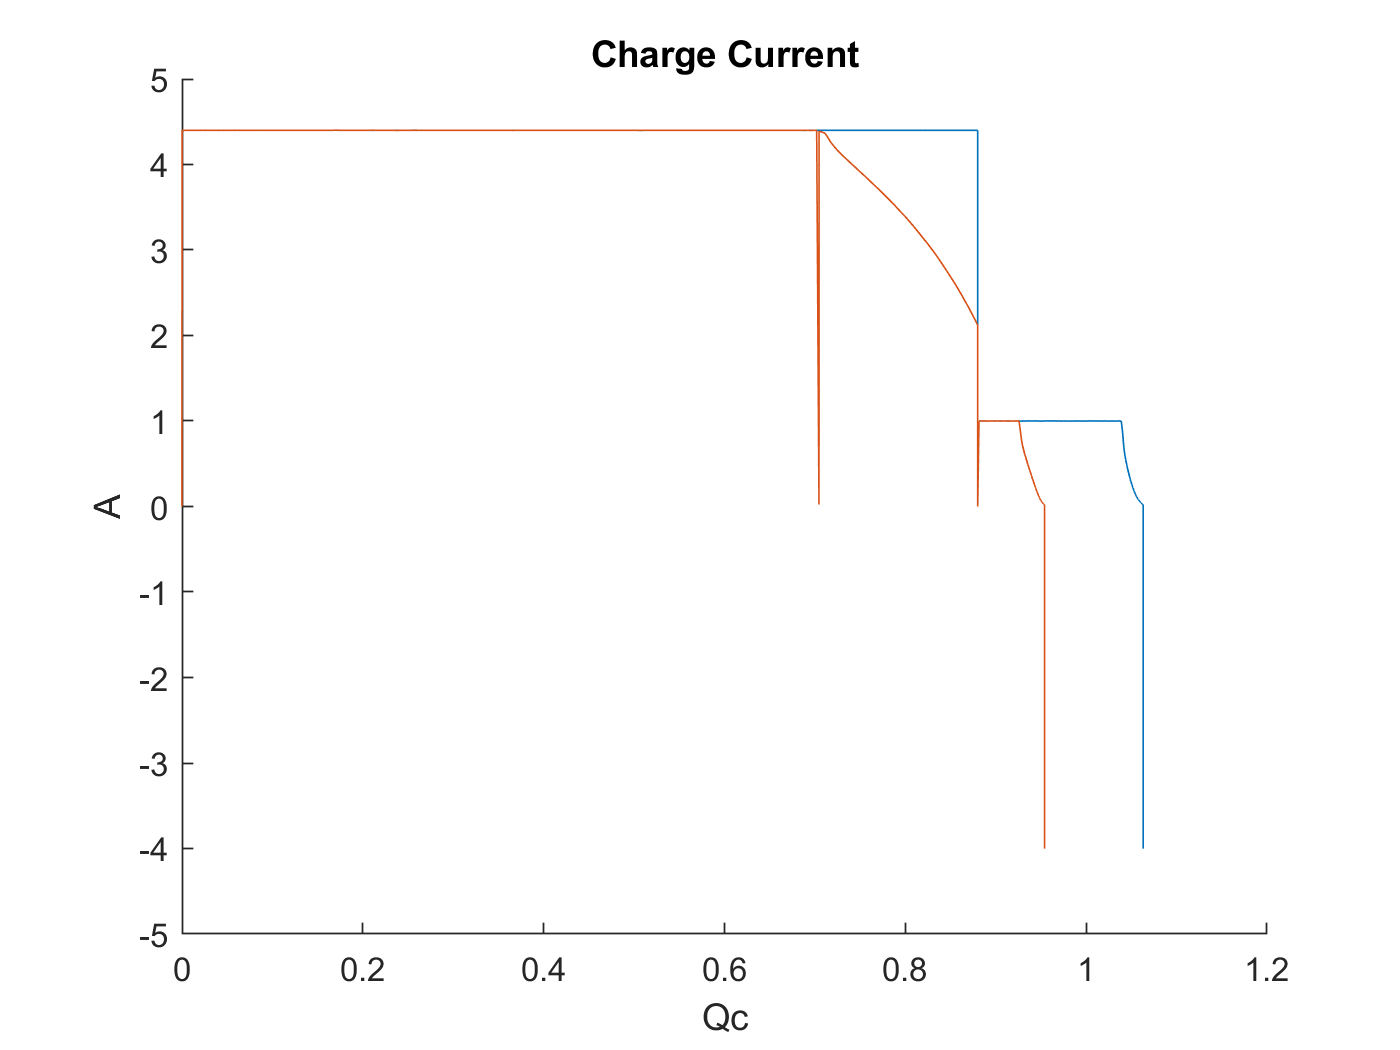


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

#### 아래 그래프에서 이상치가 있어 smooth함수를 사용했지만 큰 개선은 없다.

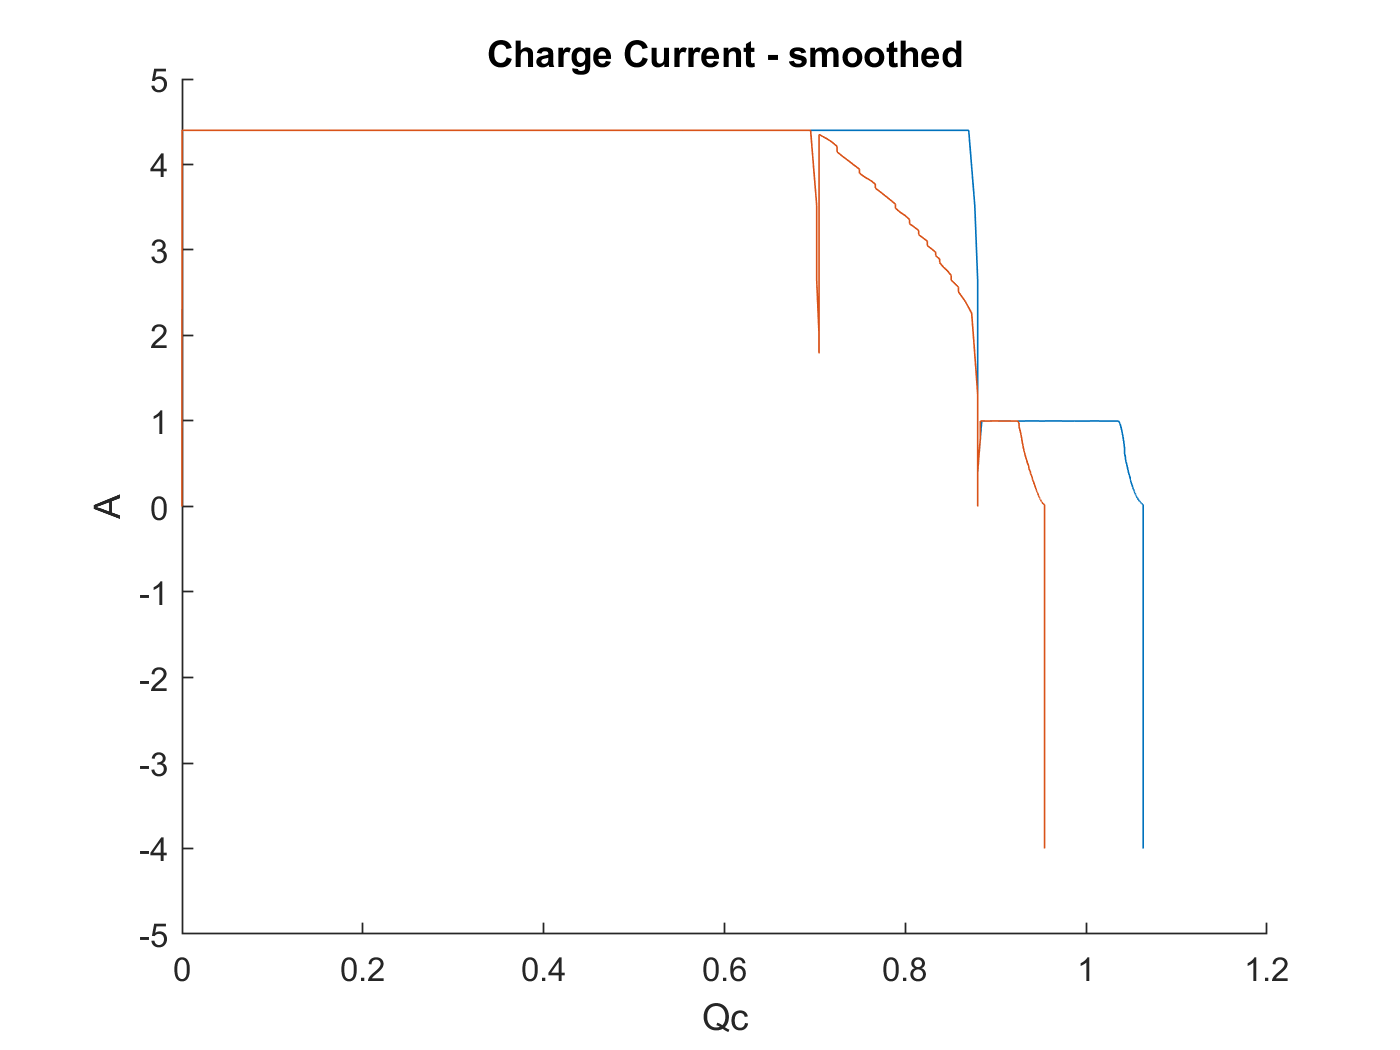

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,smooth(trainData(test_bat).cycles(i).I))     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current - smoothed'

#### x축의 단위를 용량기준으로 0 부터 1.2까지의 100개의 포인트로 전환하자. 

#### 변환에서 중요한 것은 Qc에 해당하는 I를 구하는 것이다.   

#### uniq함수에서  first 인자를 사용하면 동일한 용량값 여려개 있을때 첫번째를 선정하고

#### last 인자를 사용하면 동일한 용량값 여러개 있을대 제일 마지막 것을 선정한다.

#### 아래 그림에서 Ic를 얻기 위해서는 동일 Qc 의 첫번째 것을 선택해야 하고

#### Id를 얻기위해서는 Qd의 마지막 것을 선택해야 한다.

#### 그러나 실험결과 first 든 last 든 큰 차이가 없다.

#### .

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc)
        plot(trainData(test_bat).cycles(i).Qd,'-')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge / Discharge Q'

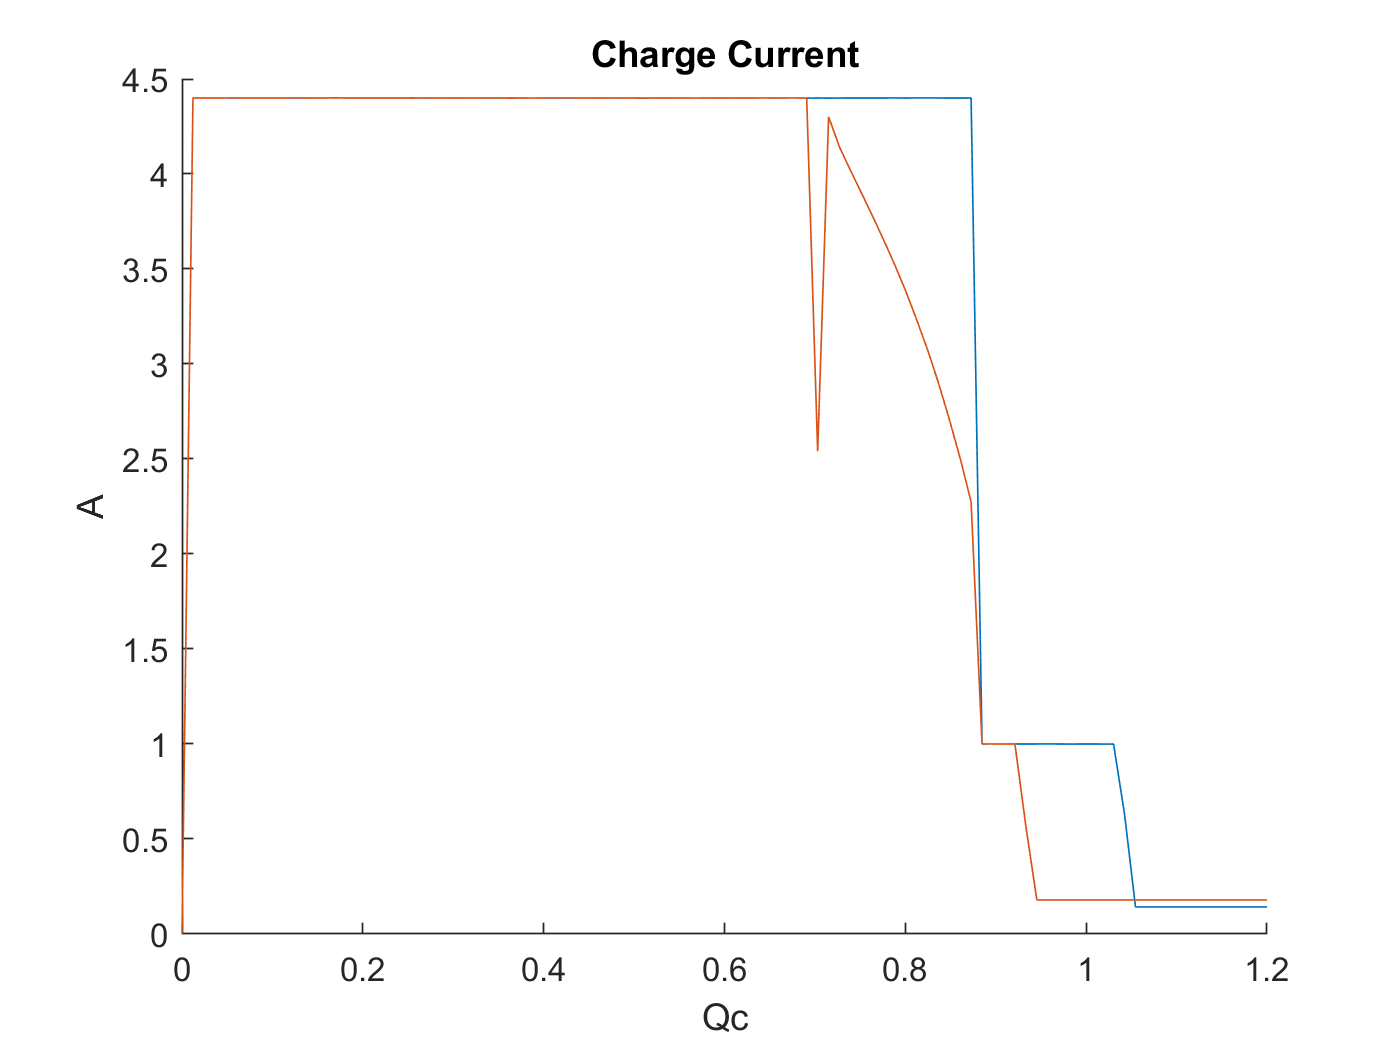


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"first");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'


length(new_x_c)

ans = 100

index_first = index

index_first =      1
     2
    25
    48
    53
    57
    60
    64
    66
    69


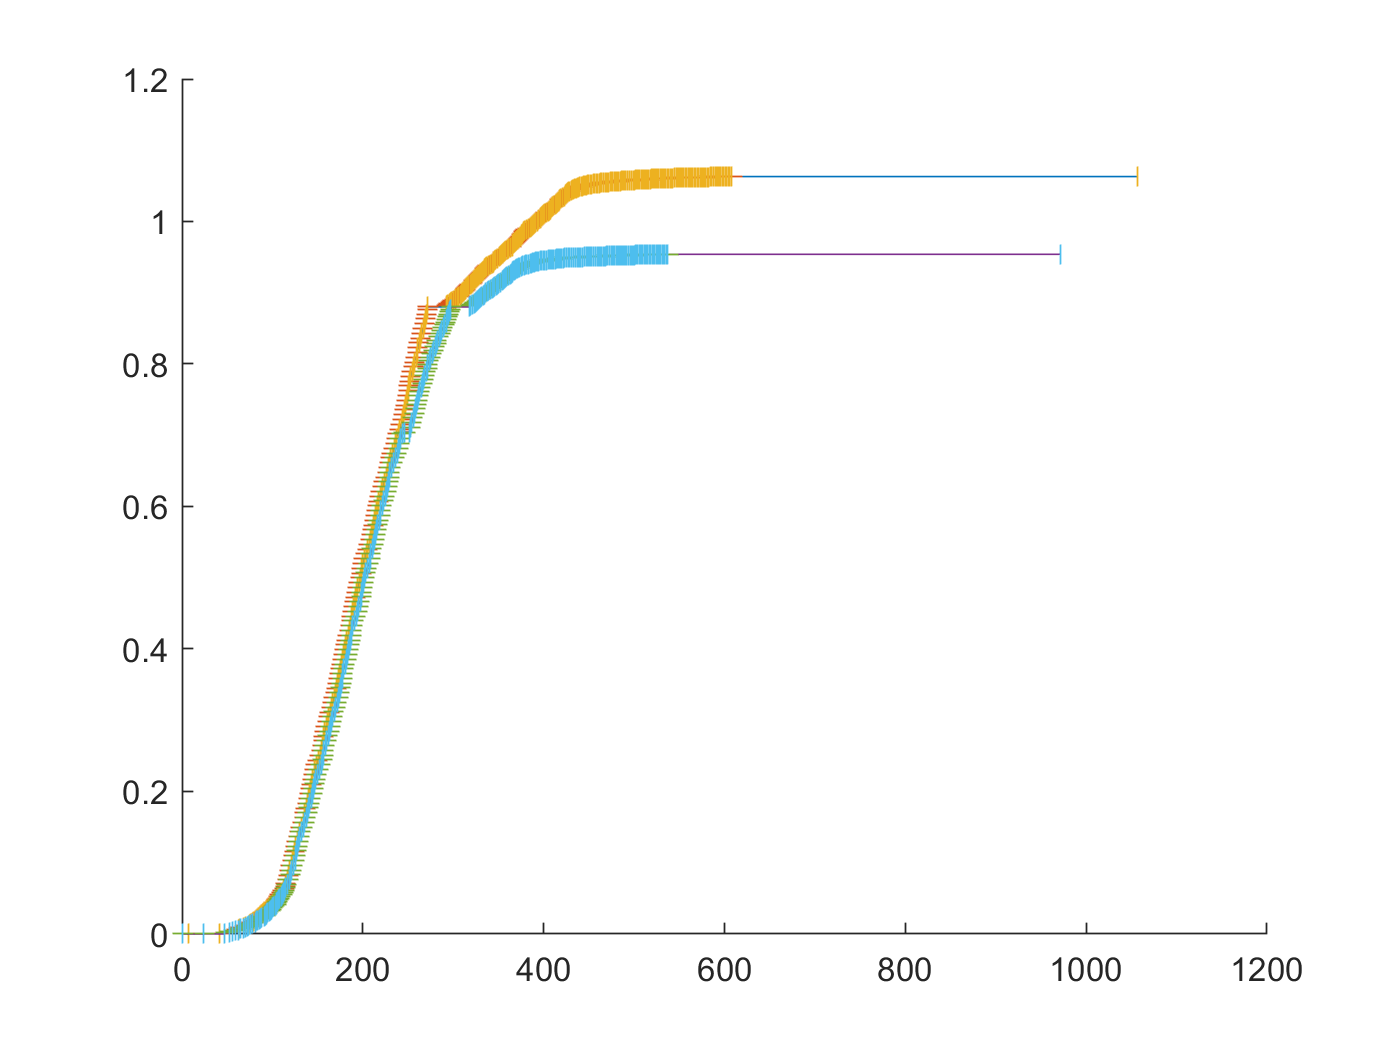

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c_first, index_first] = unique(trainData(test_bat).cycles(i).Qc,"first");
    [x_c_last, index_last] = unique(trainData(test_bat).cycles(i).Qc,"last");
    plot(trainData(test_bat).cycles(i).Qc)
    plot(index_first,x_c_first,'_')
    plot(index_last,x_c_last,'|')
    end
end
hold off

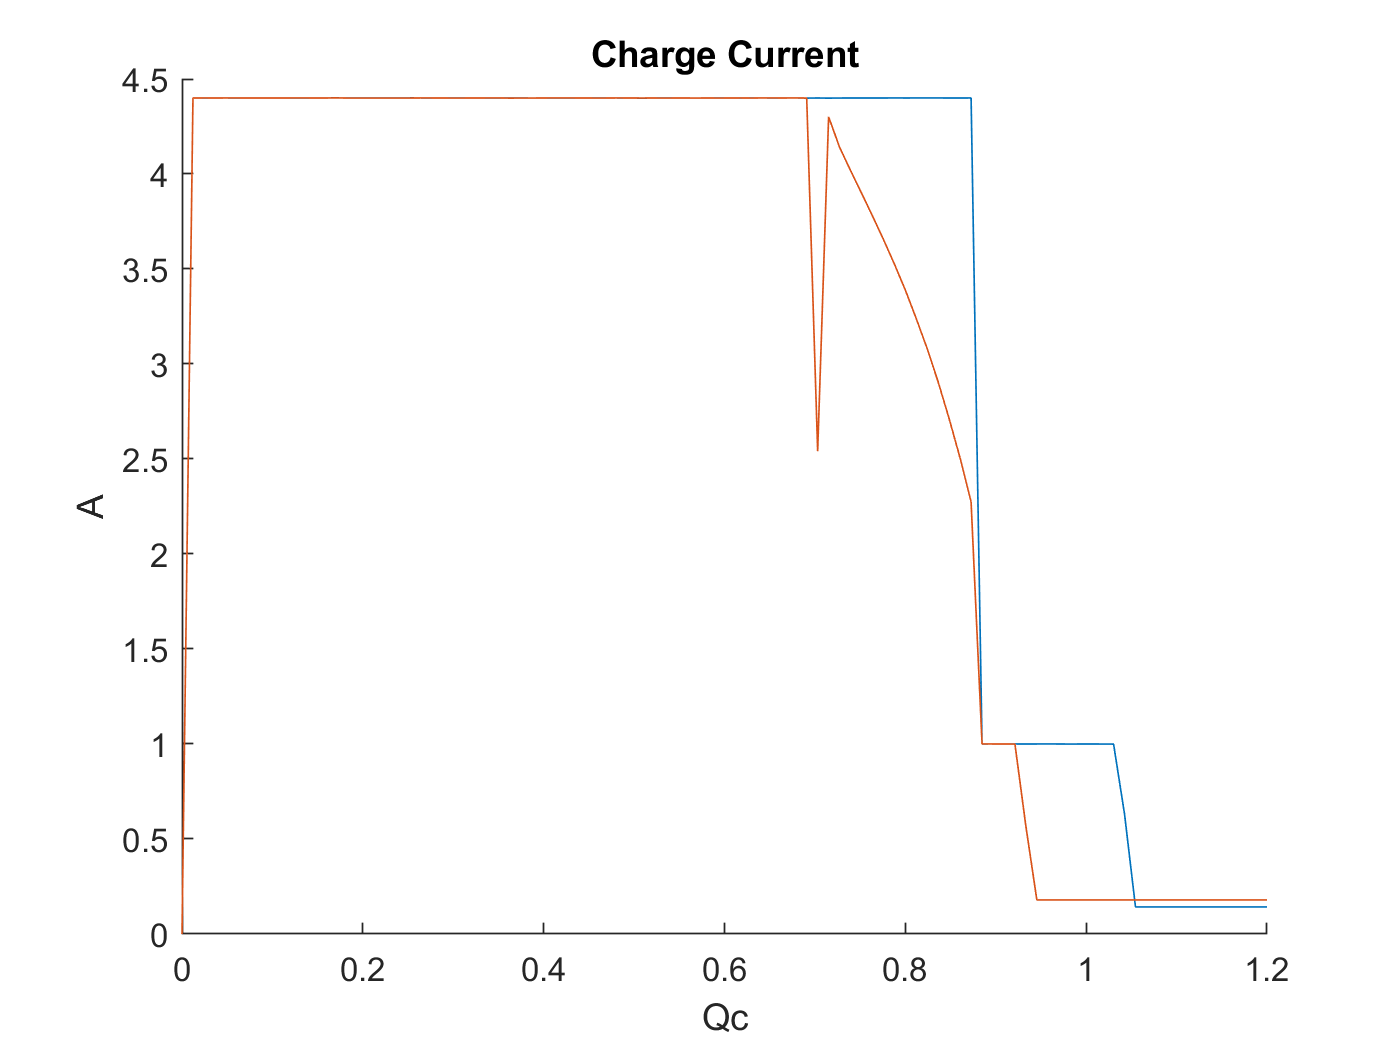


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
    [x_c, index] = unique(trainData(test_bat).cycles(i).Qc,"last");
    %[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
    y_c = trainData(test_bat).cycles(i).I(index);
    new_x_c = linspace(0,1.2,100);
    new_y_c = interp1(x_c,y_c,new_x_c,'linear');
    new_y_c = fillmissing(new_y_c,'nearest');
    plot(new_x_c,new_y_c);  
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Current'

length(new_x_c)

ans = 100

index_last = index

index_last =      1
    24
    47
    52
    56
    59
    63
    65
    68
    70



indexs = [index_first index_last]

indexs =      1     1
     2    24
    25    47
    48    52
    53    56
    57    59
    60    63
    64    65
    66    68
    69    70


indexs_gap = index_last - index_first

indexs_gap =      0
    22
    22
     4
     3
     2
     3
     1
     2
     1


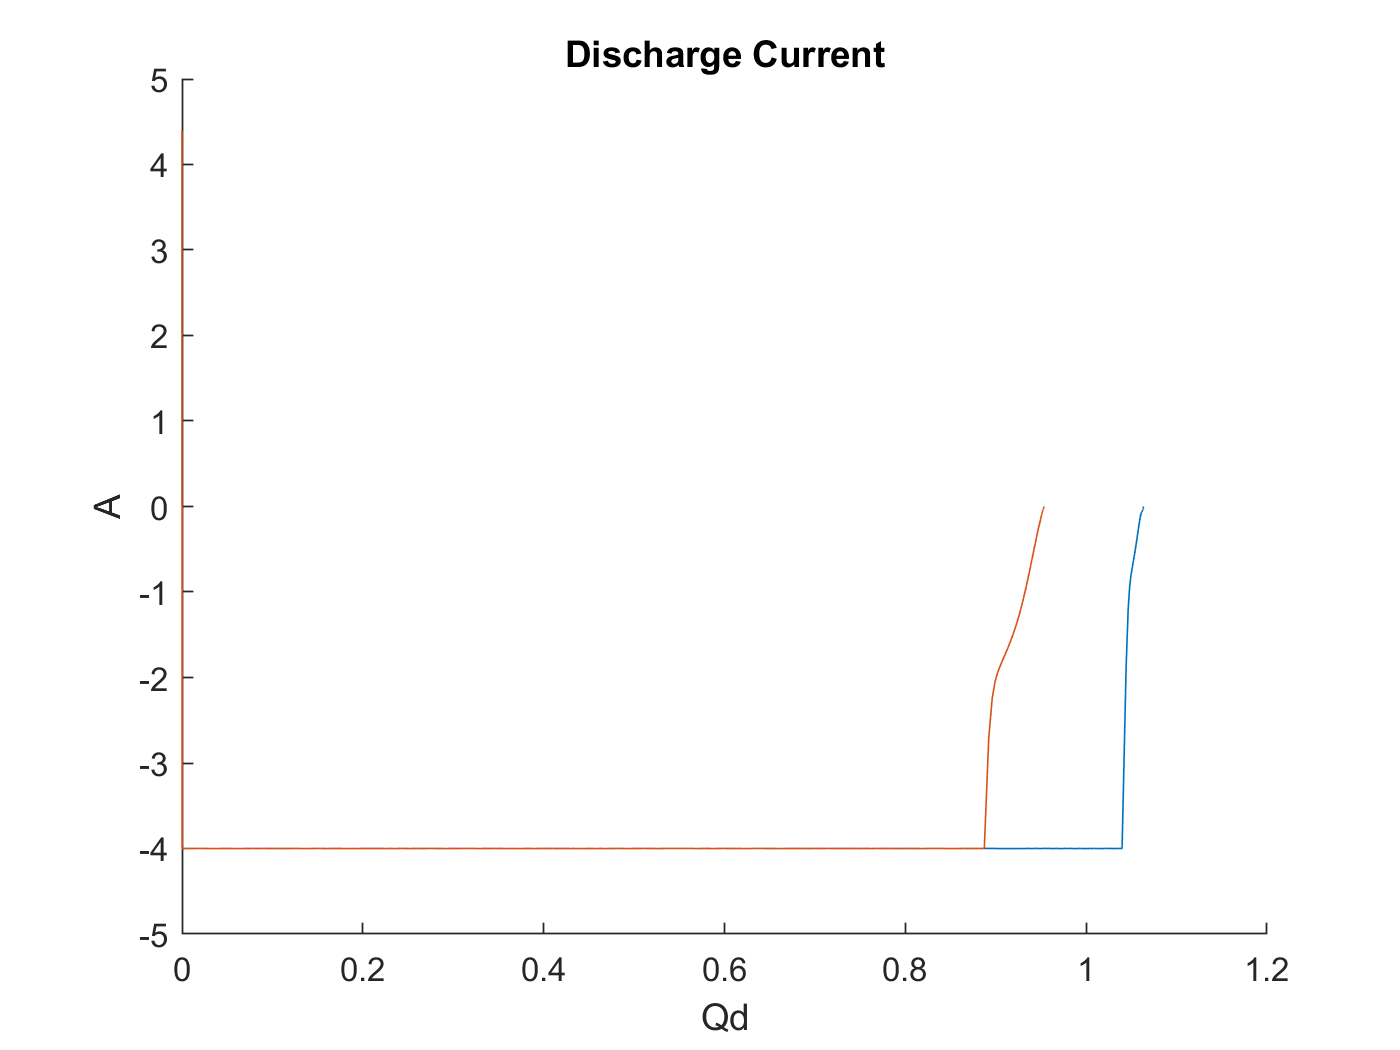


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).I)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Current'

# 테스트 한것들 

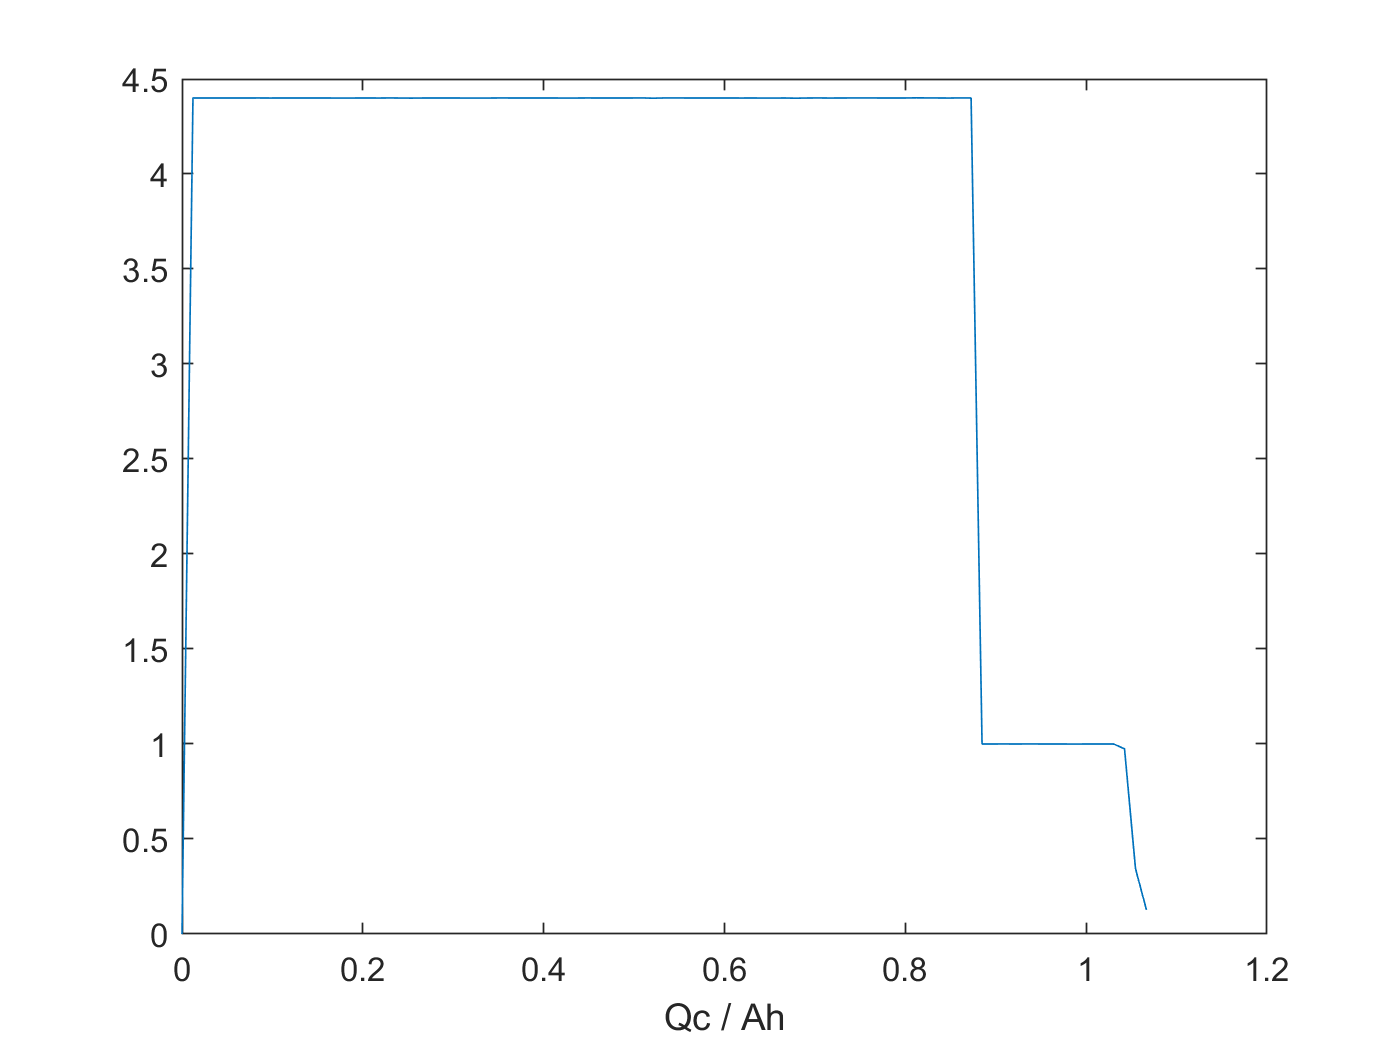


[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).I(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxNon = isnan(new_y_c )

idxNon = 1×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =          0    4.4001    4.4000    4.4001    4.4001    4.3999    4.4000    4.4001    4.3998    4.4001    4.4001    4.4001    4.4000    4.4000    4.3998    4.3997    4.3999    4.4000    4.3998    4.4003    4.3997    4.3994    4.3999    4.3999    4.4001    4.4000    4.3997    4.3998    4.3998    4.4002    4.4001    4.4000    4.4000    4.4001    4.3999    4.3998    4.3999    4.4002    4.3999    4.3999    4.4001    4.4000    4.4004    4.3990    4.4002    4.4002    4.4001    4.4000    4.3999    4.3999


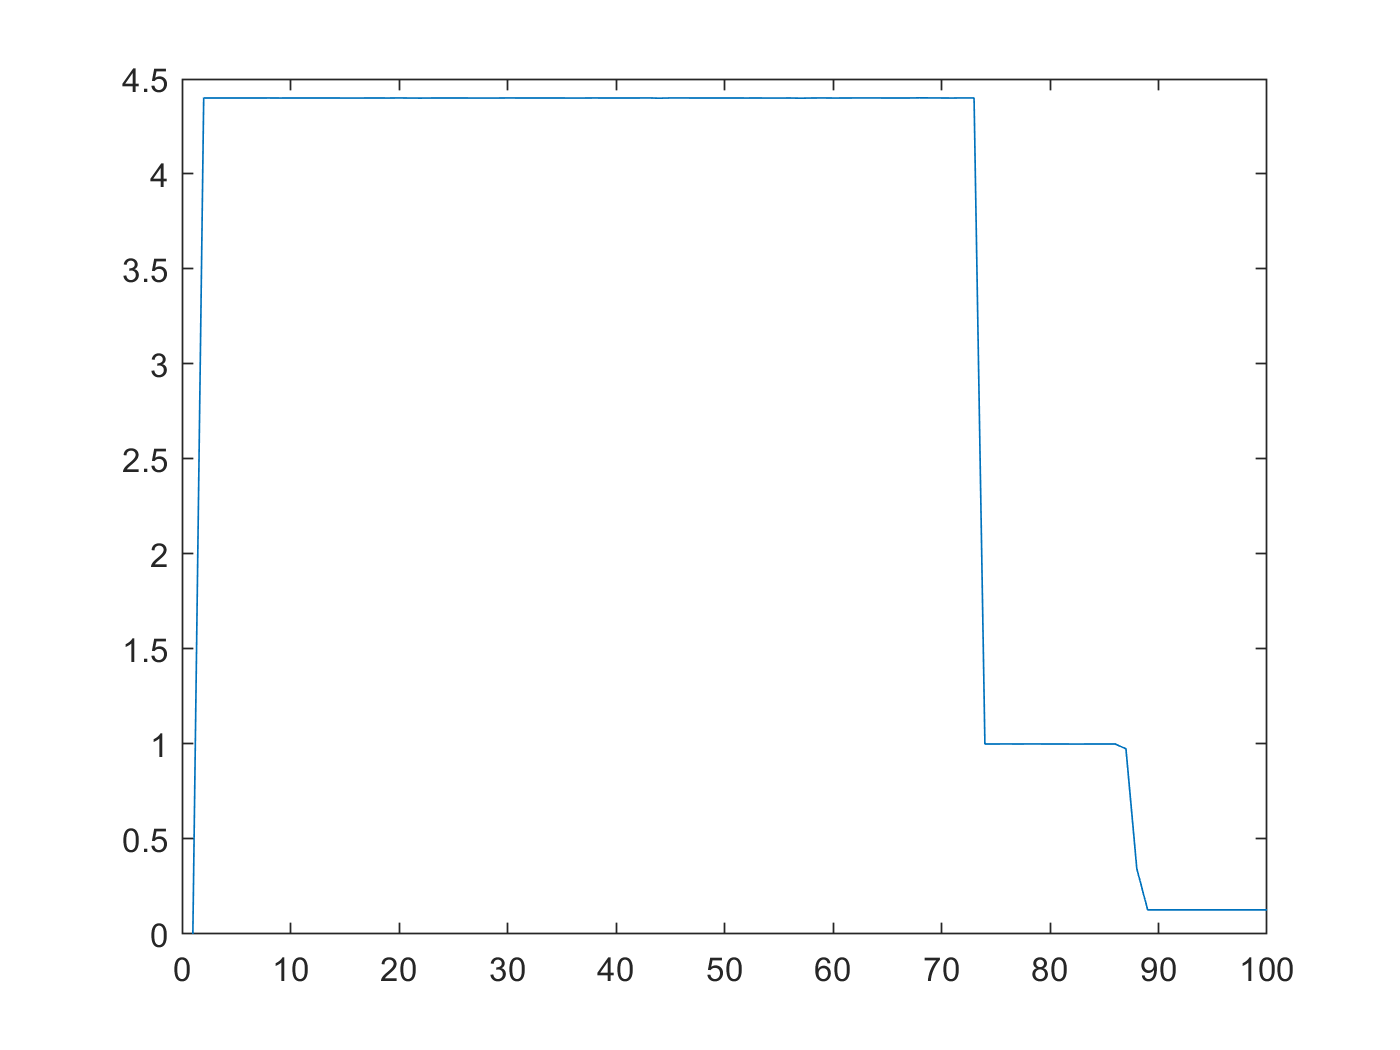

plot(new_y_c_fix)

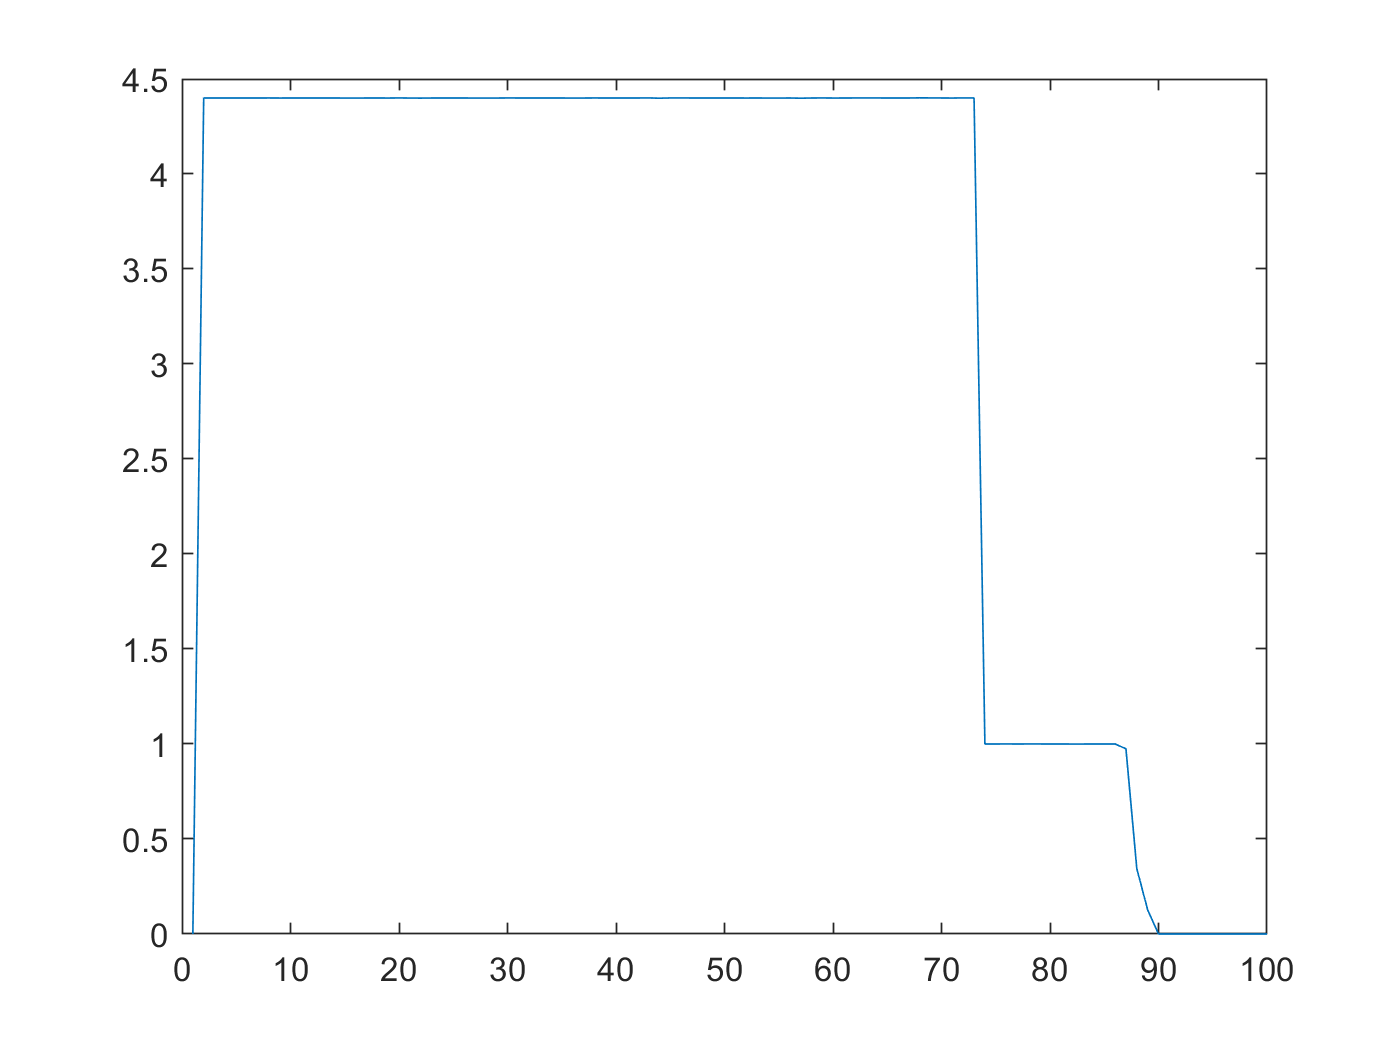

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

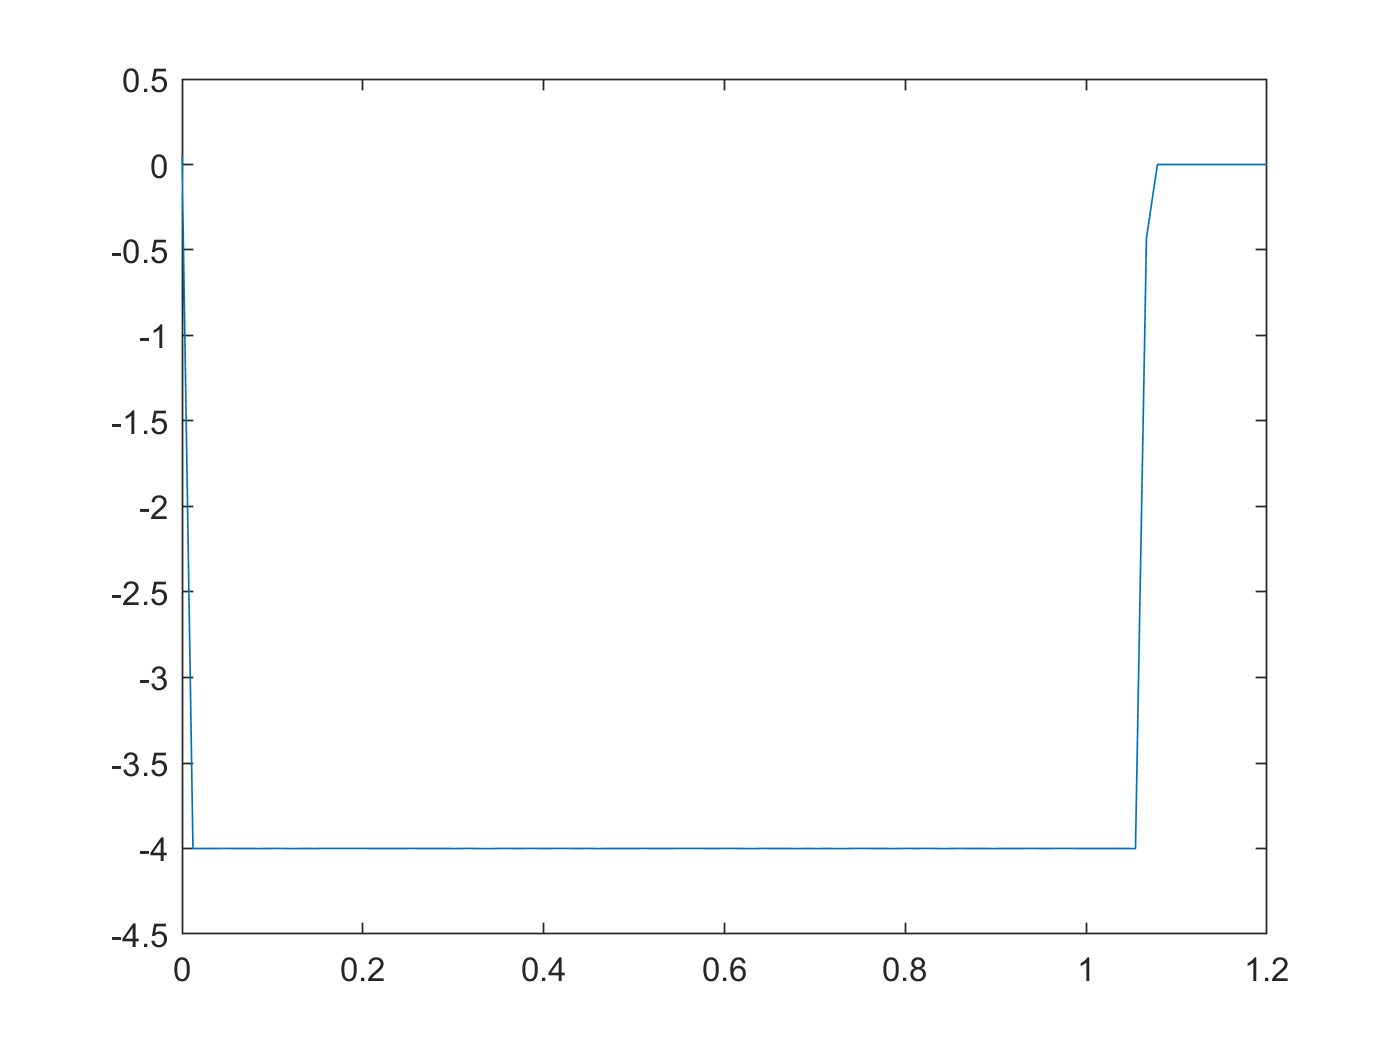

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).I(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

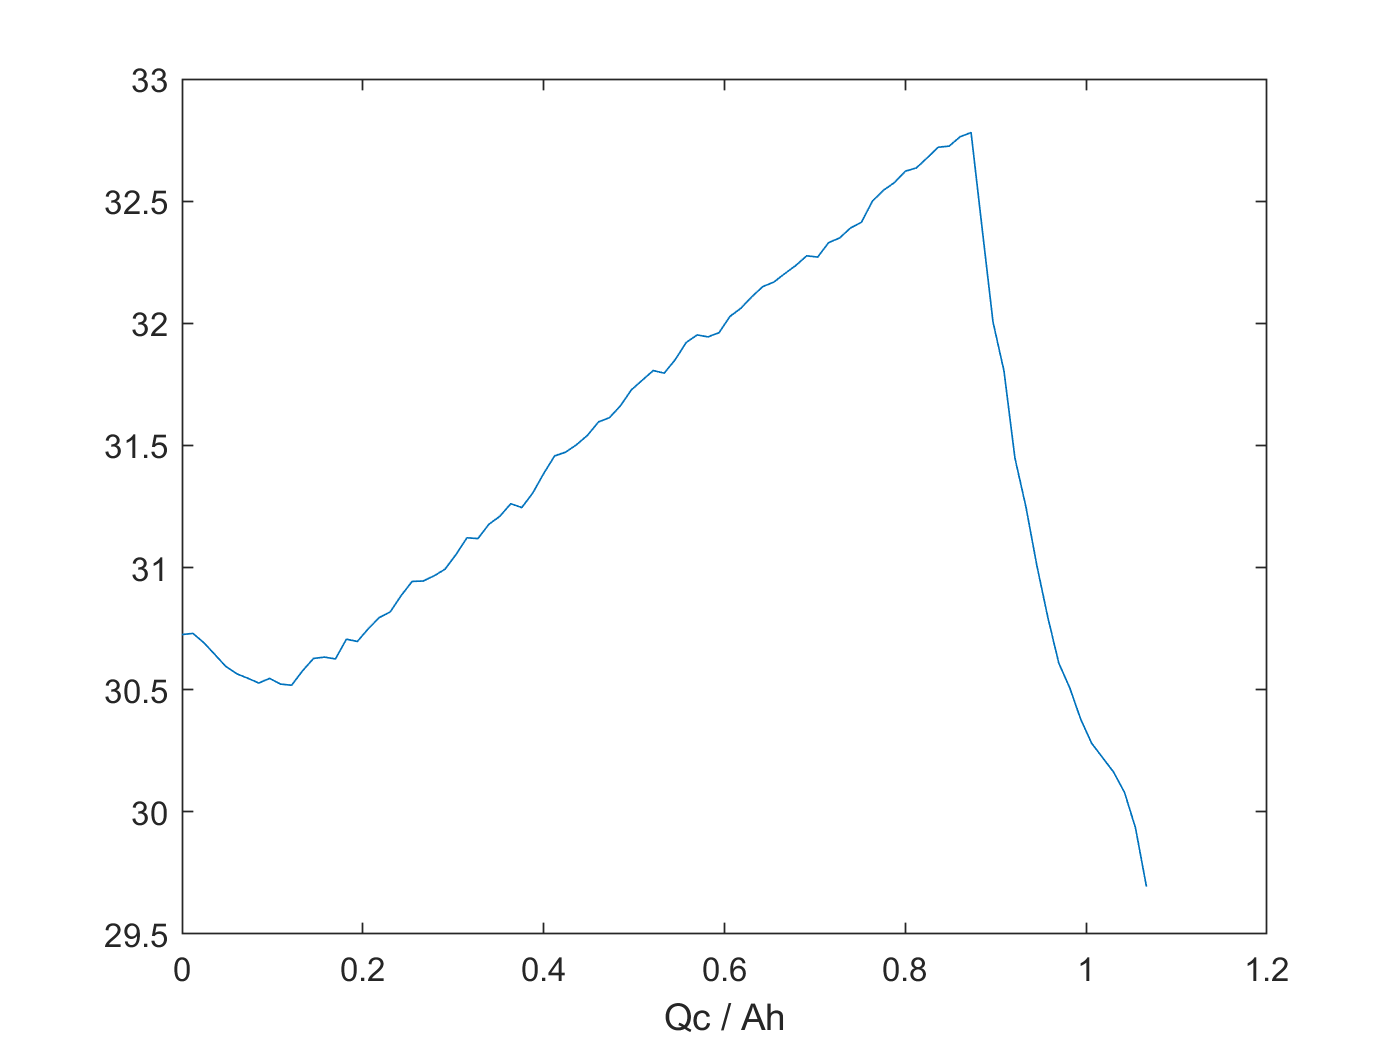

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).T(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =    30.7258   30.7306   30.6922   30.6439   30.5951   30.5652   30.5472   30.5274   30.5463   30.5230   30.5182   30.5774   30.6280   30.6334   30.6259   30.7066   30.6976   30.7497   30.7953   30.8187   30.8856   30.9434   30.9449   30.9660   30.9935   31.0532   31.1220   31.1186   31.1772   31.2099   31.2614   31.2456   31.3049   31.3848   31.4571   31.4723   31.5030   31.5415   31.5961   31.6135   31.6619   31.7274   31.7671   31.8066   31.7959   31.8510   31.9211   31.9523   31.9445   31.9616


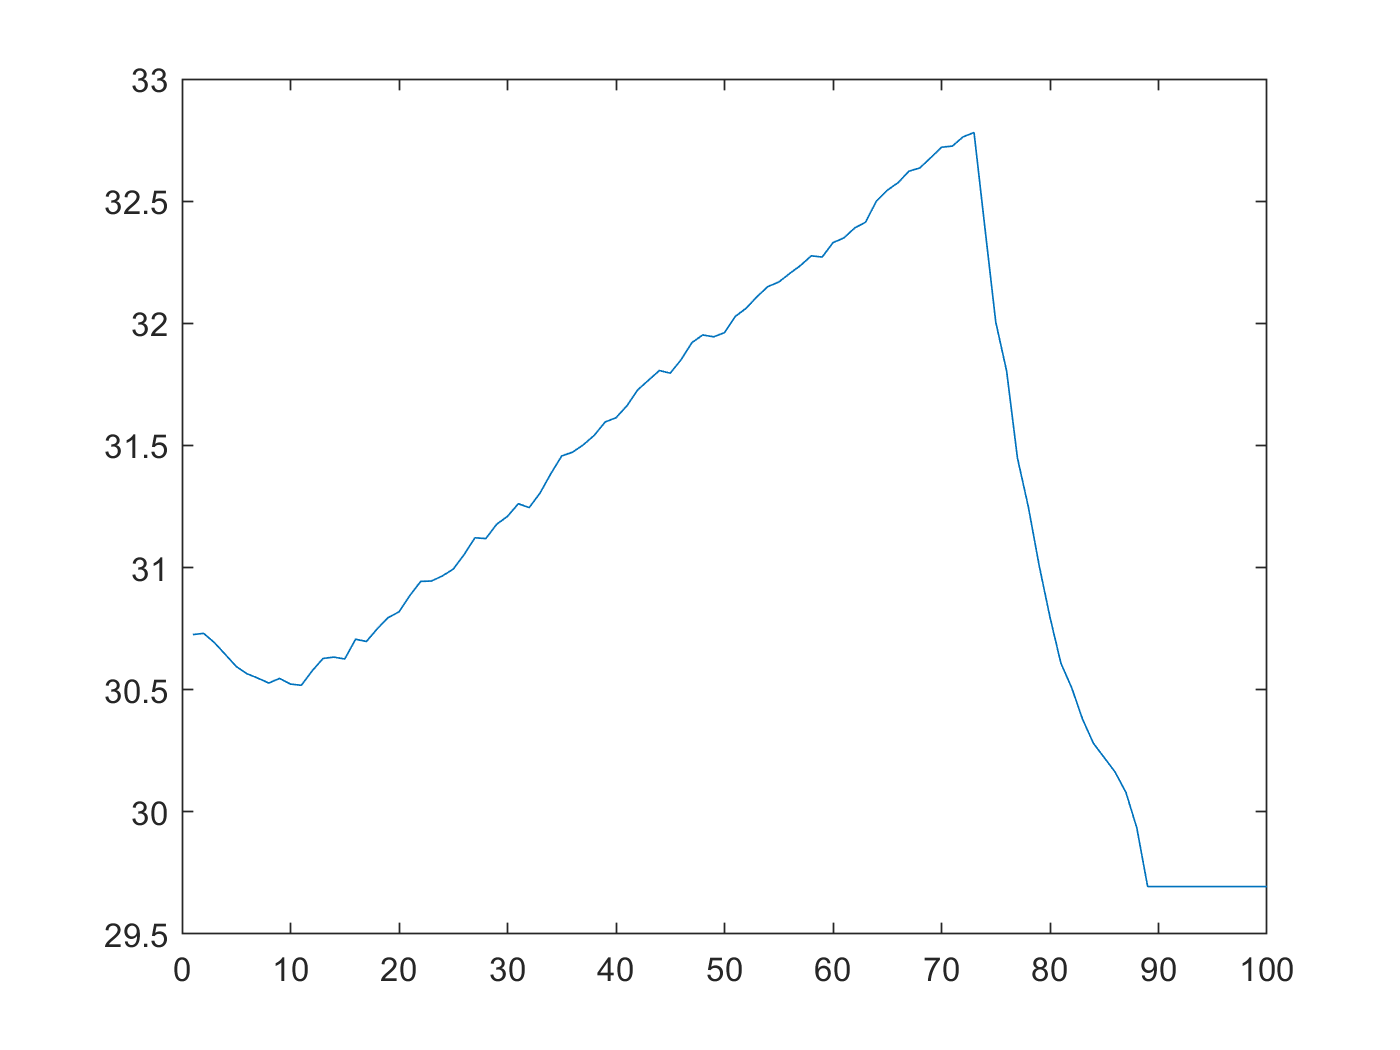

plot(new_y_c_fix)

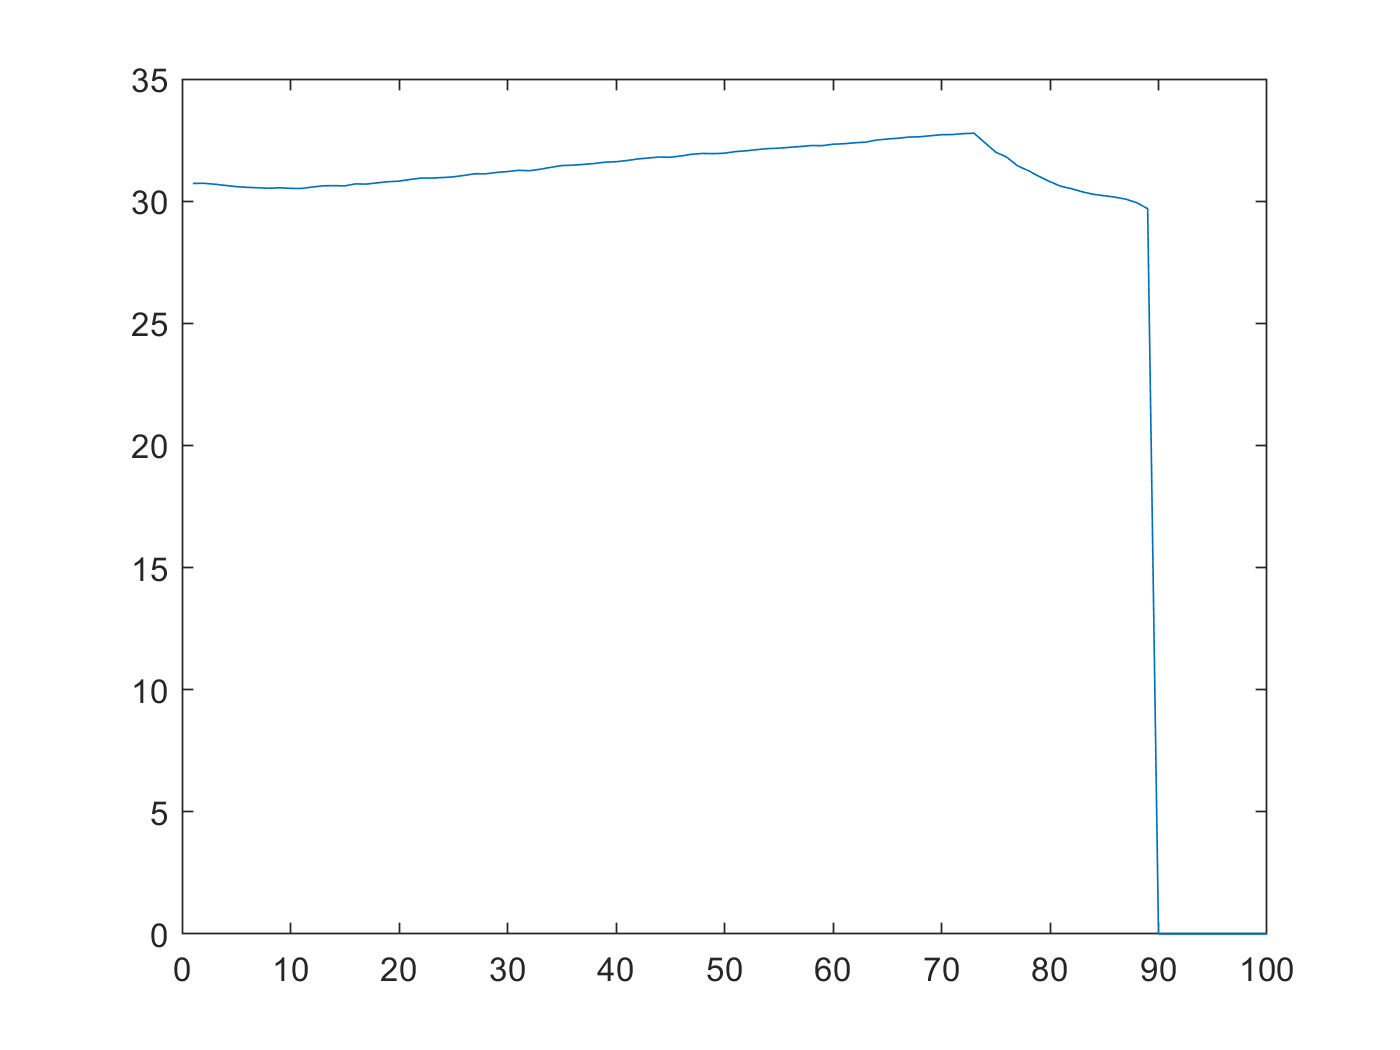

% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

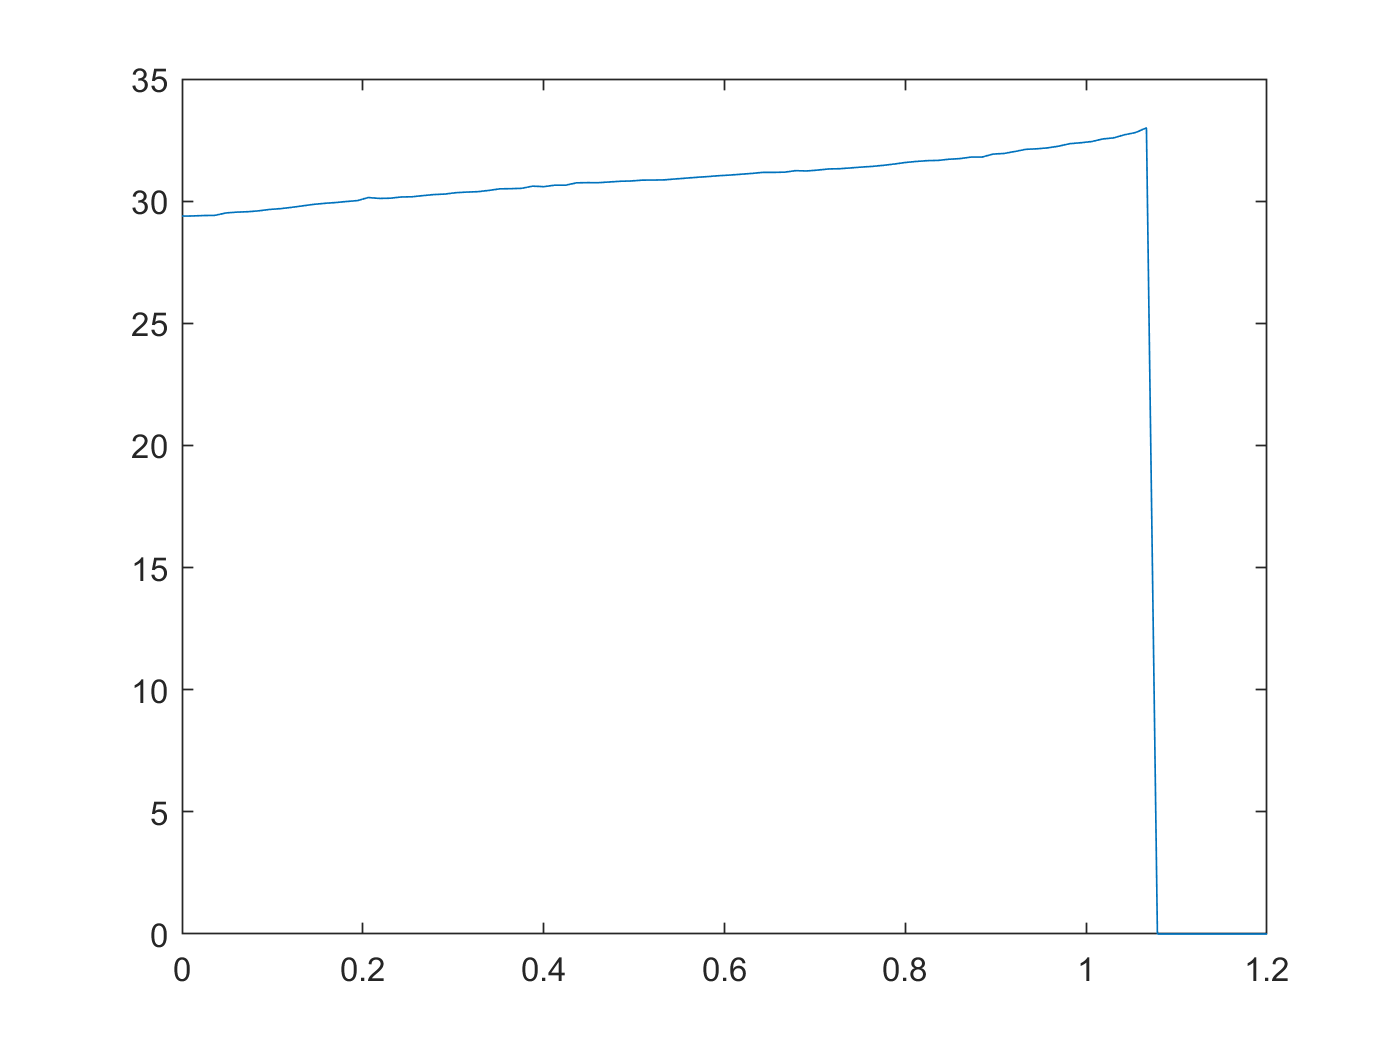

%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).T(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

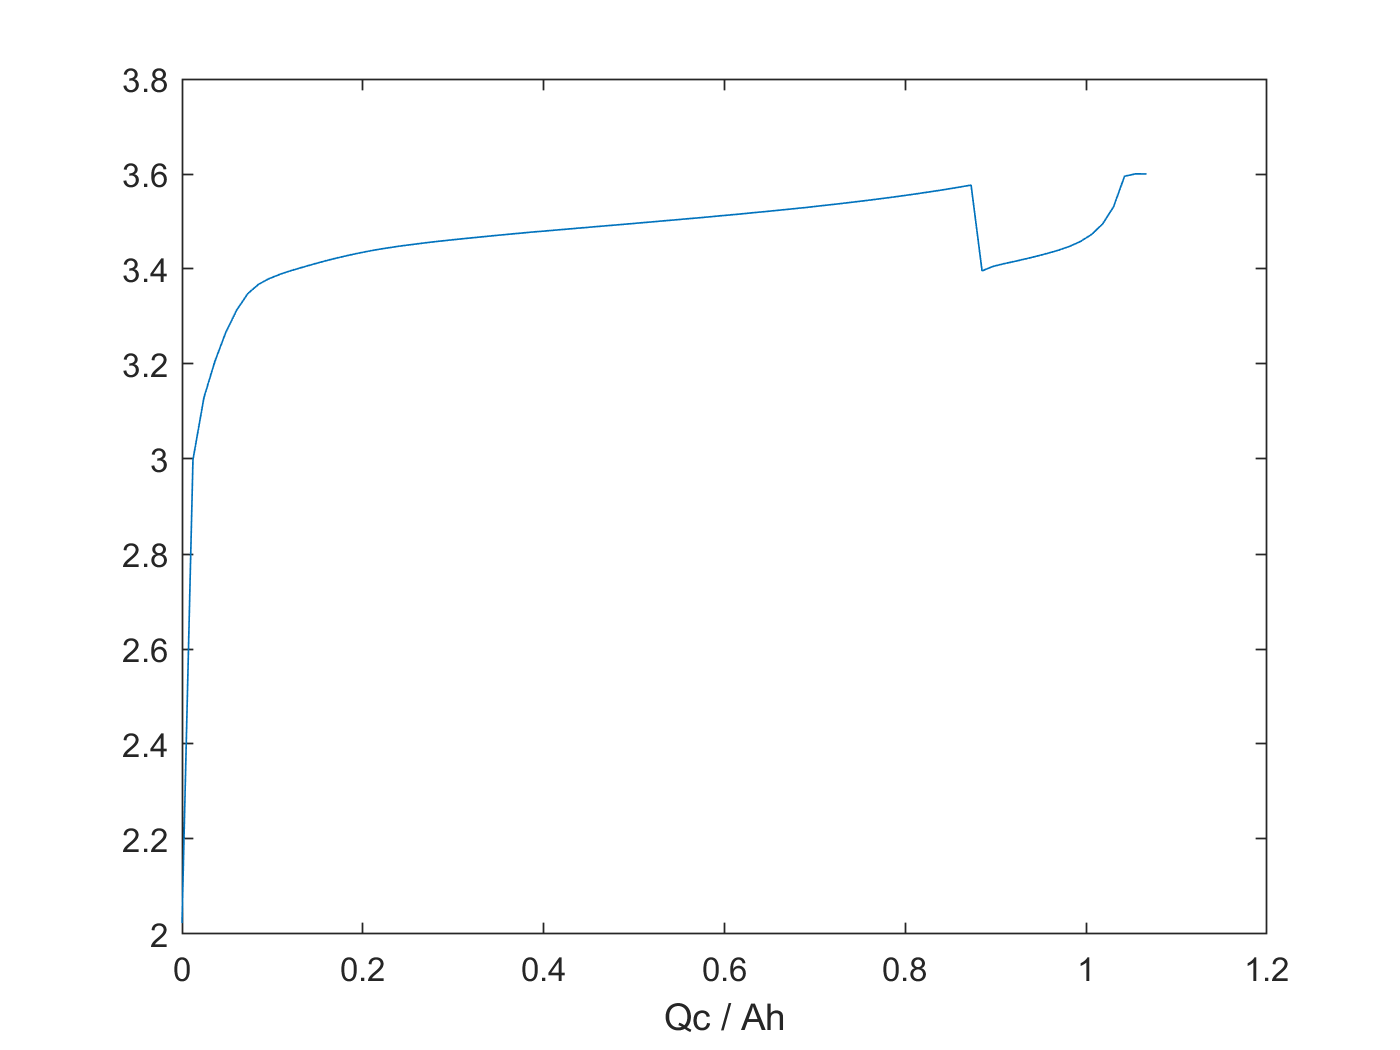

[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc,"last");
%[x_c, index] = unique(trainData(test_bat).cycles(cycleNum).Qc)
y_c = trainData(test_bat).cycles(cycleNum).V(index);
new_x_c = linspace(0,1.2,100);
new_y_c = interp1(x_c,y_c,new_x_c,'linear');
plot(new_x_c,new_y_c);
xlabel("Qc / Ah")

% https://kr.mathworks.com/matlabcentral/answers/88808-fill-nans-in-array-with-last-value?s_tid=ta_ans_results
% https://kr.mathworks.com/matlabcentral/answers/29481-last-non-nan-observation
idx = (~isnan(new_y_c ))

idx = 1×100 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


vr = new_y_c(idx); %v non nan
new_y_c_fix = vr(cumsum(idx)) %use cumsum to build index into vr

new_y_c_fix =     2.0230    2.9983    3.1292    3.2055    3.2669    3.3139    3.3482    3.3681    3.3802    3.3894    3.3969    3.4037    3.4103    3.4165    3.4224    3.4278    3.4329    3.4375    3.4416    3.4452    3.4486    3.4516    3.4545    3.4573    3.4598    3.4622    3.4646    3.4668    3.4692    3.4714    3.4736    3.4757    3.4779    3.4797    3.4817    3.4837    3.4857    3.4876    3.4897    3.4915    3.4935    3.4954    3.4975    3.4994    3.5015    3.5034    3.5055    3.5074    3.5096    3.5117


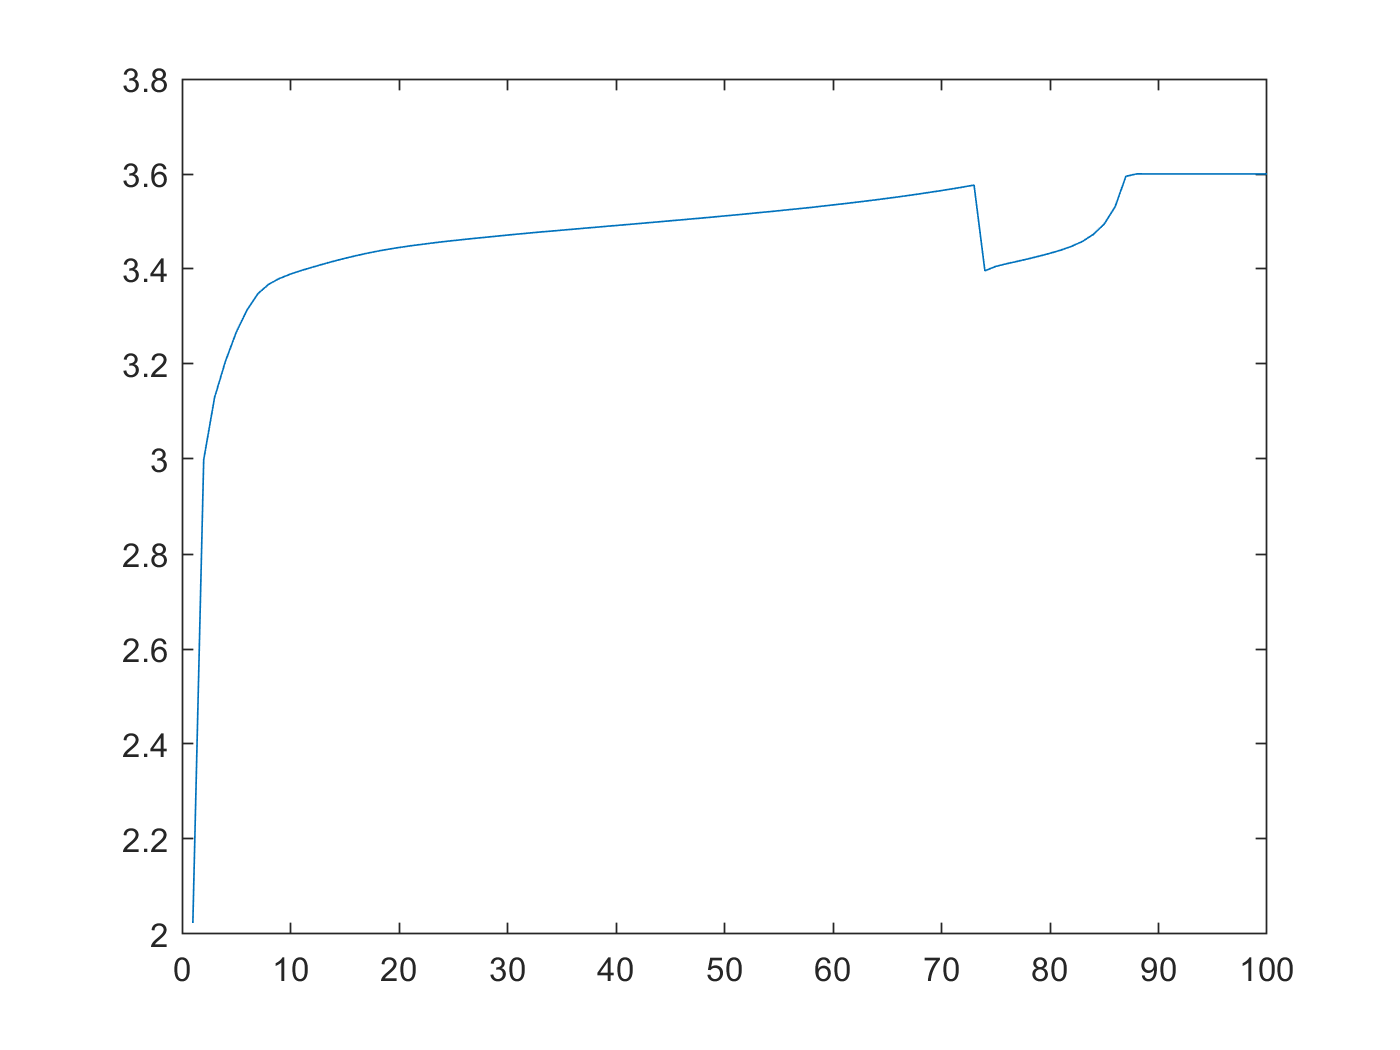

plot(new_y_c_fix)

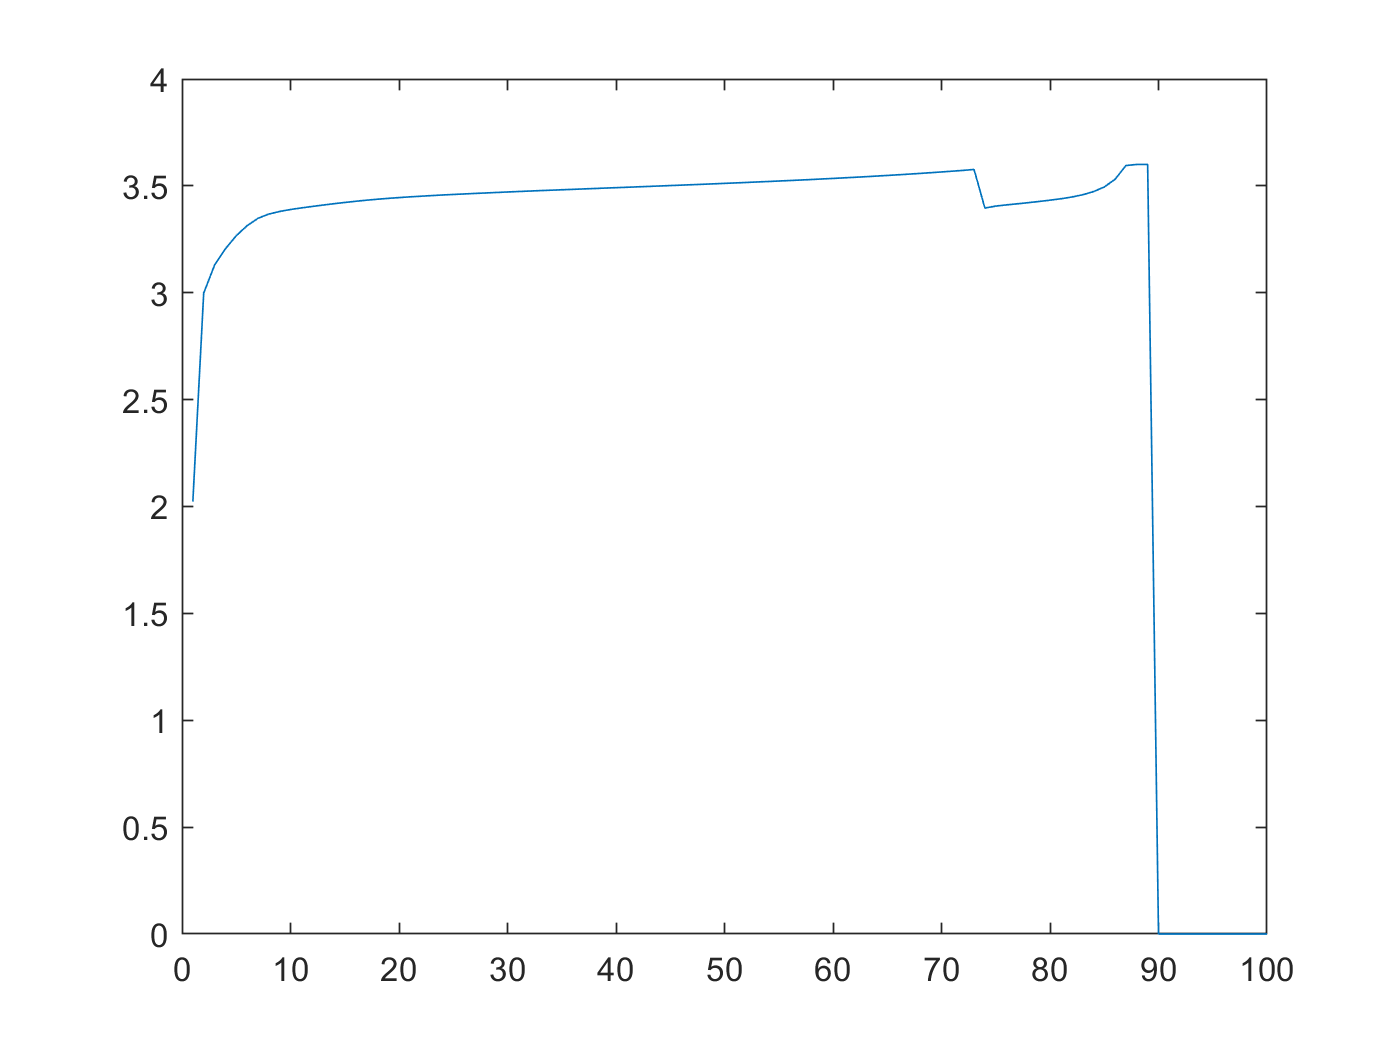


% https://kr.mathworks.com/matlabcentral/answers/6038-convert-zeros-to-nan
% https://kr.mathworks.com/matlabcentral/answers/85568-how-to-convert-nan-to-zero?s_tid=ta_ans_results

new_y_c_fix_fill_zero = new_y_c;
%% not work
%new_y_c_fix_fill_zero(new_y_c_fix_fill_zero==NaN)=0;
%new_y_c_fix_fill_zeroA(find(new_y_c_fix_fill_zero==NaN)) = 0;

%% work
new_y_c_fix_fill_zero(isnan(new_y_c_fix_fill_zero)) = 0;
plot(new_y_c_fix_fill_zero)

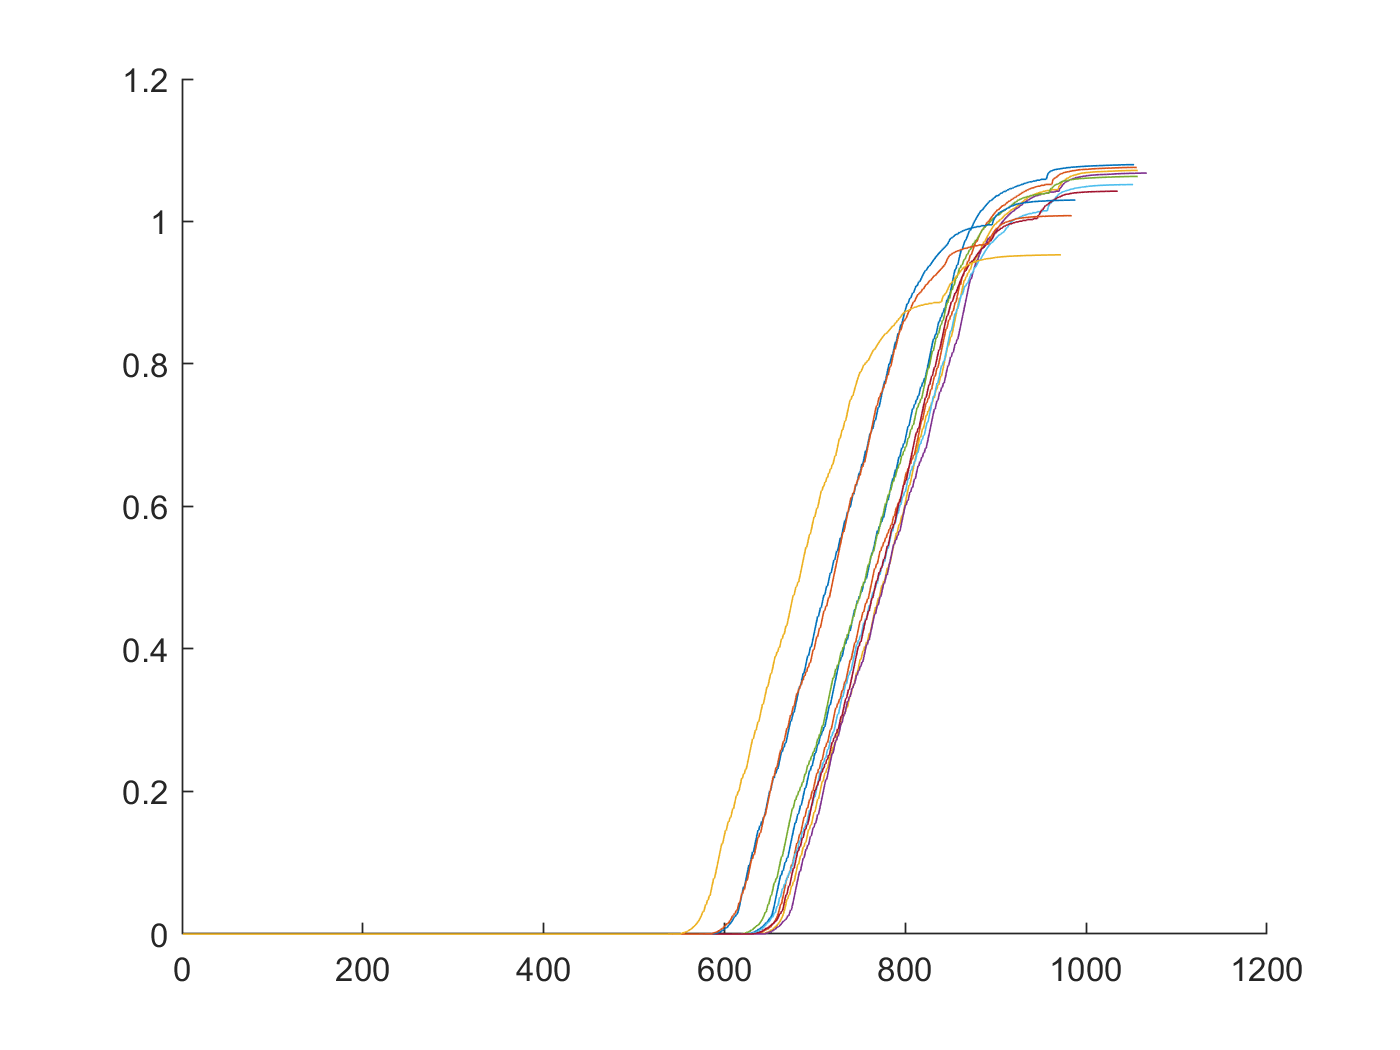

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
        plot(trainData(test_bat).cycles(i).Qd)
    end
end 
hold off 

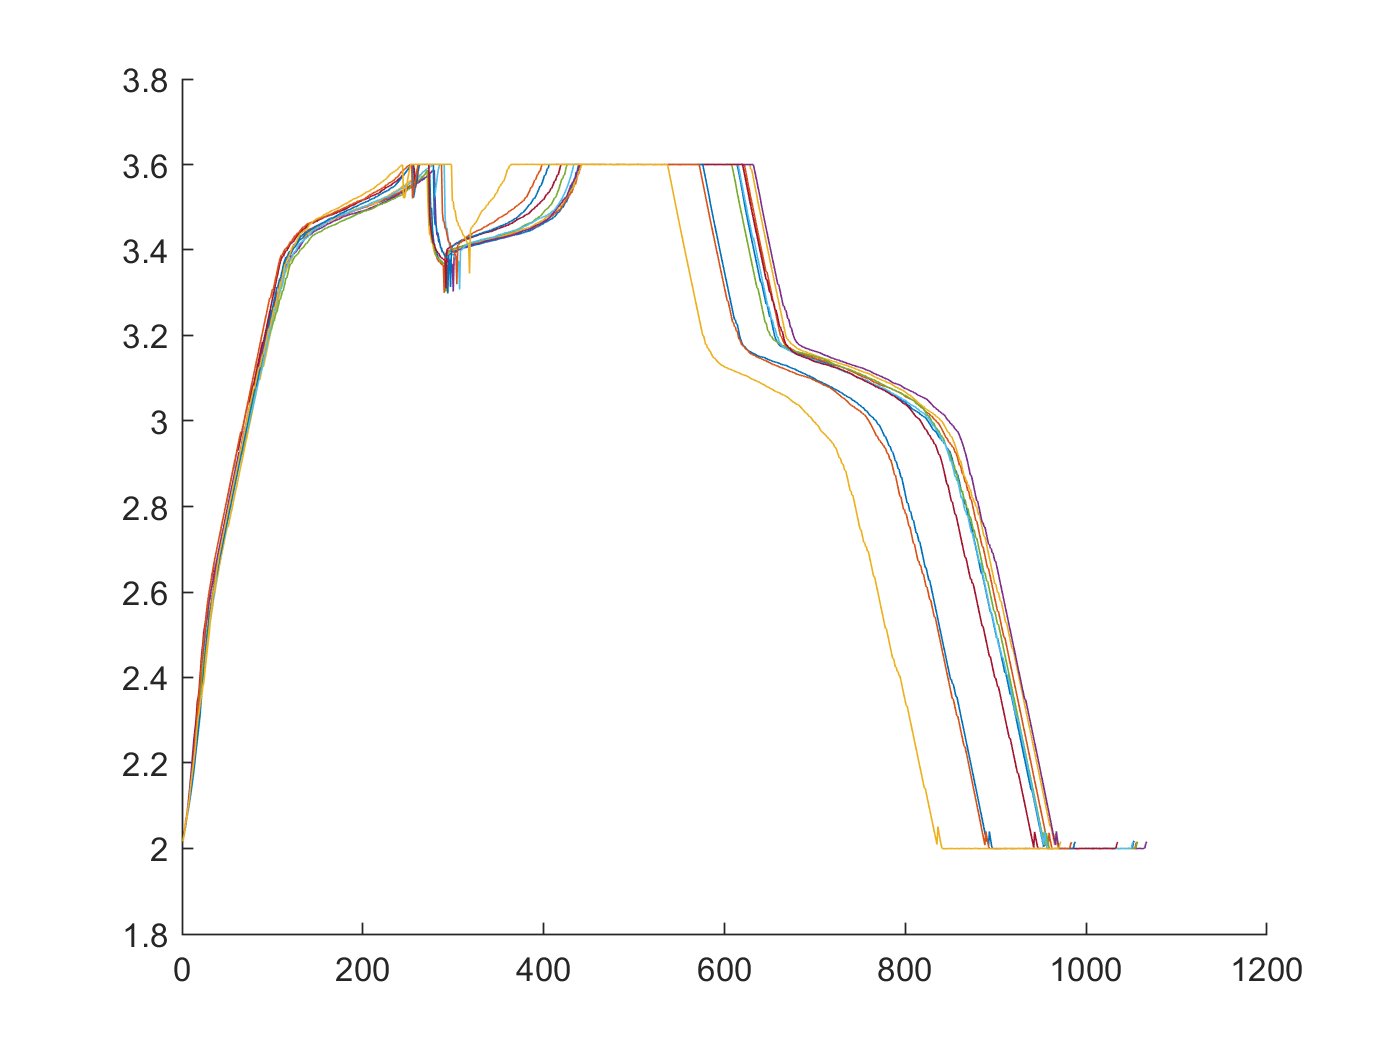

figure
hold on
for i=1:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    plot(trainData(test_bat).cycles(i).V')
    end
end 
hold off 

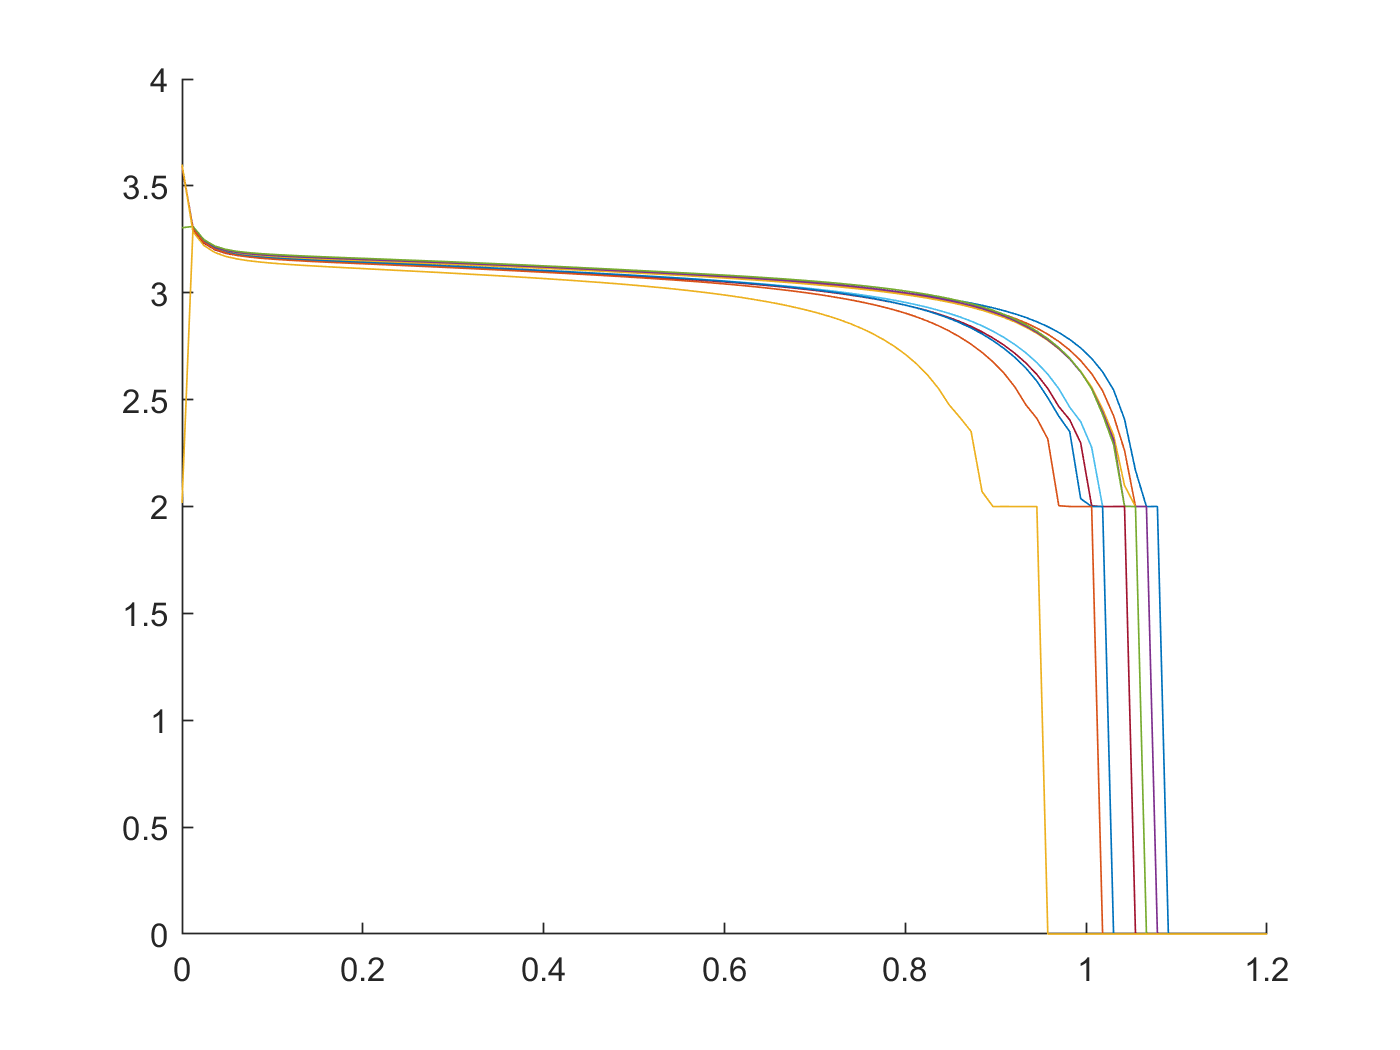

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [x_d, index] = unique(trainData(test_bat).cycles(i).Qd,"last");
    
    y_d = trainData(test_bat).cycles(i).V(index);
    new_x_d = linspace(0,1.2,100);
    new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
    new_y_d(isnan(new_y_d)) = 0;
    plot(new_x_d,new_y_d);
    end
end 
hold off

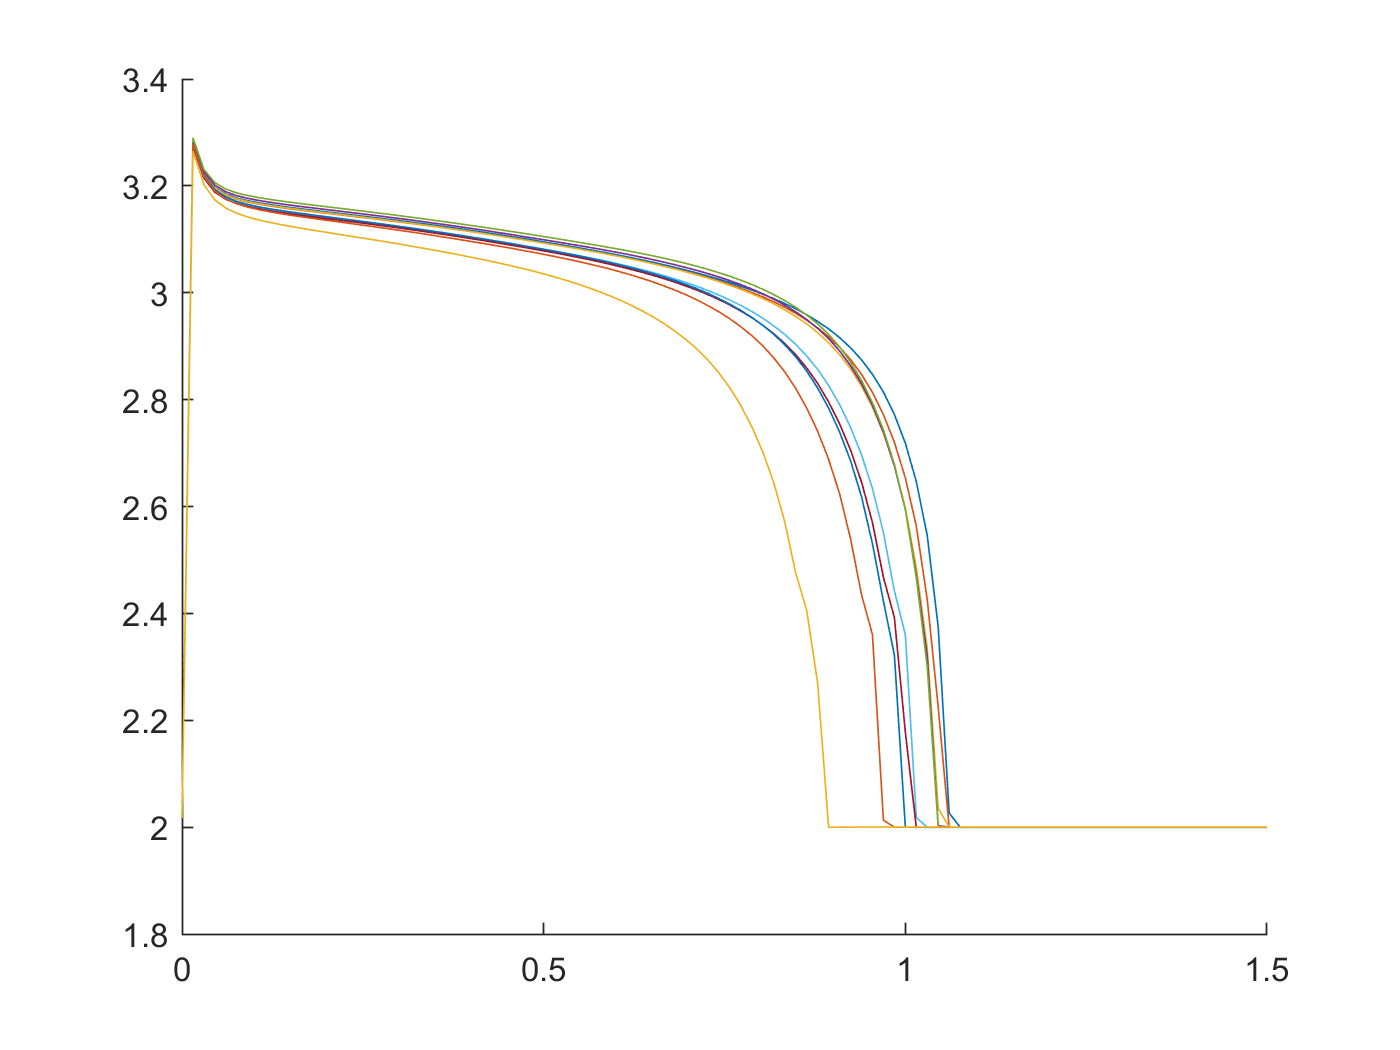

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.5,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

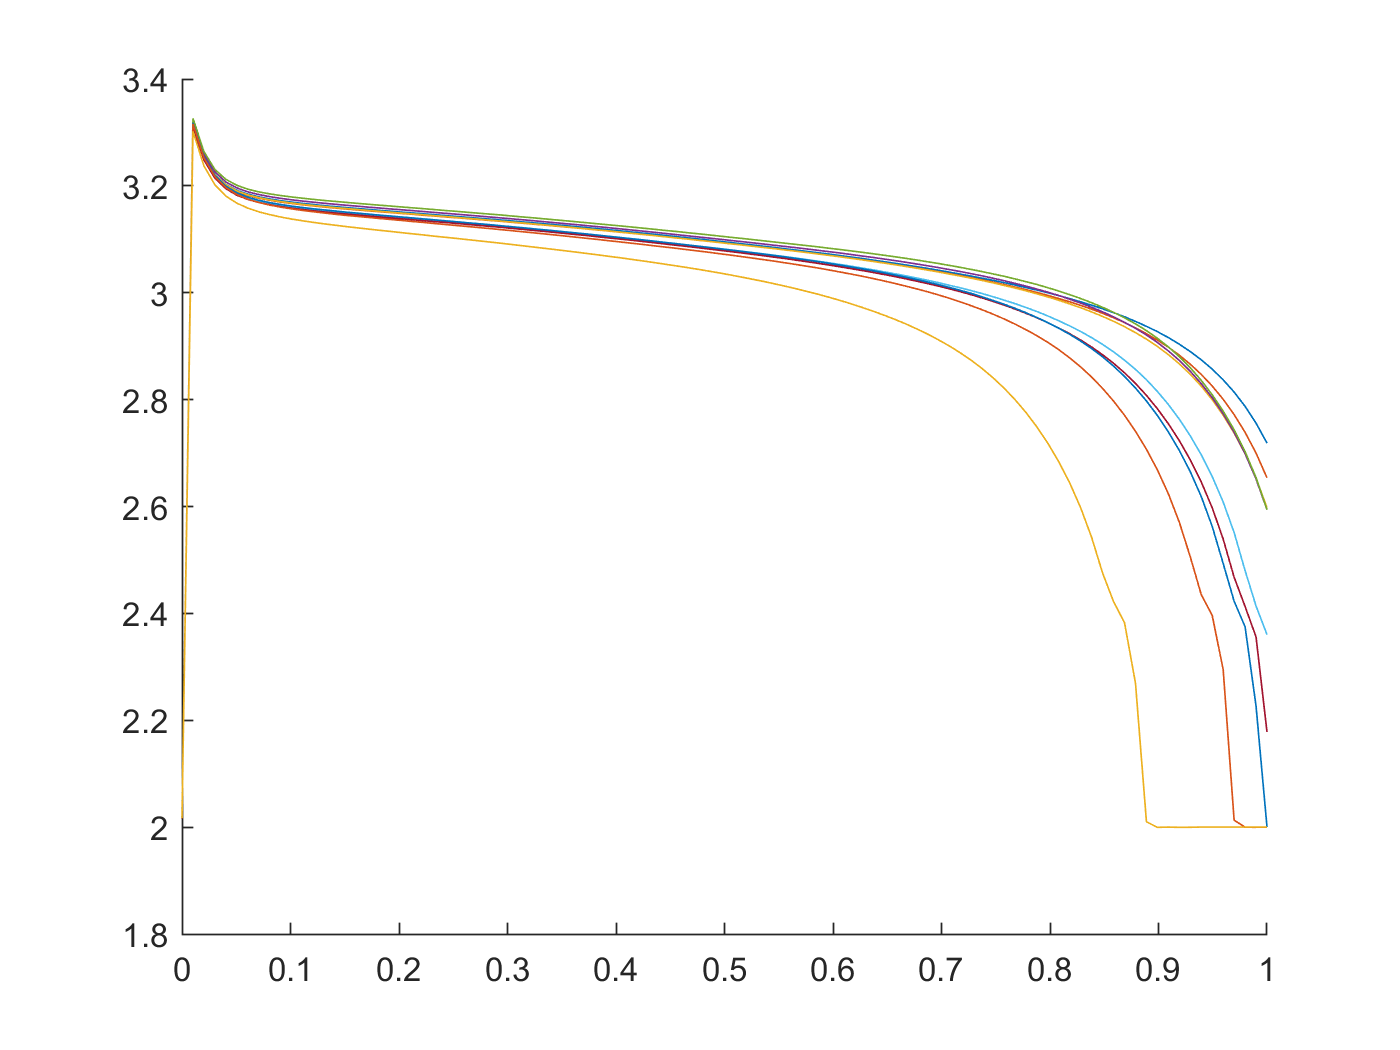

figure
hold on

for i=3:trainData(test_bat).cycle_life-3
    if rem(i,100) == 0
    Qd_tmp = trainData(test_bat).cycles(i).Qd;
    Qd_tmp(Qd_tmp<0) = 0;
    %[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
    [xq, index] = unique(Qd_tmp,"first");
    
    yV = trainData(test_bat).cycles(i).V(index);
    xq_new = linspace(0,1.0,100);
    yV = interp1(xq,yV,xq_new,'linear'); 
    yV = fillmissing(yV,'nearest');
    %new_y_d(isnan(new_y_d)) = 0;
    plot(xq_new,yV);
    end
end 
hold off

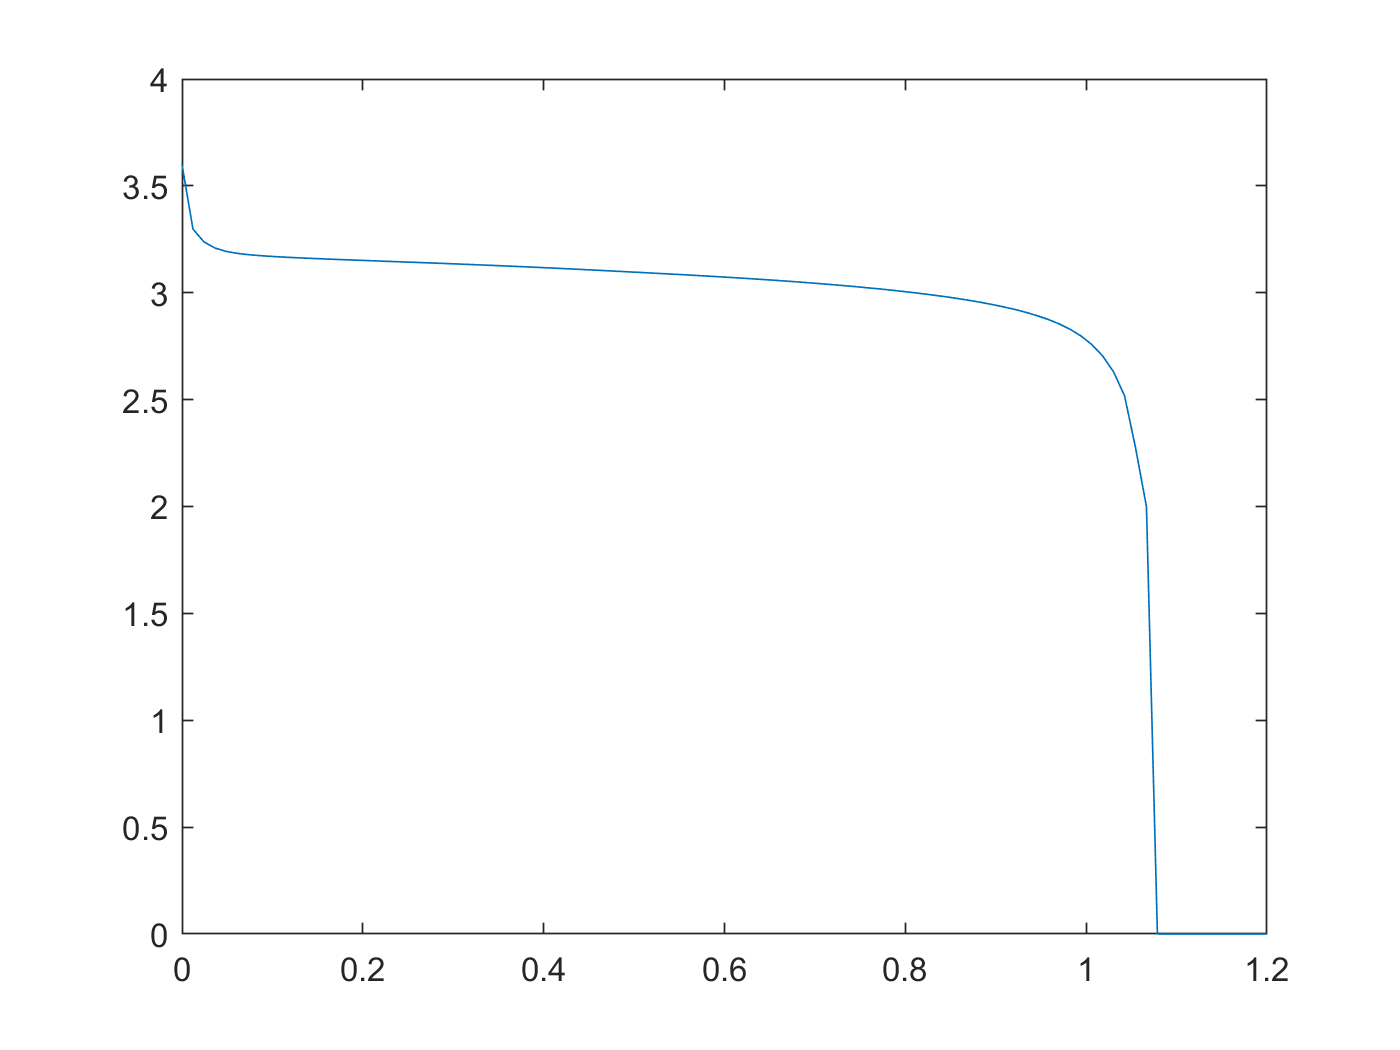


%[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd);
[x_d, index] = unique(trainData(test_bat).cycles(cycleNum).Qd,"last");

y_d = trainData(test_bat).cycles(cycleNum).V(index);
new_x_d = linspace(0,1.2,100);
new_y_d = interp1(x_d,y_d,new_x_d,'linear'); 
new_y_d(isnan(new_y_d)) = 0;
plot(new_x_d,new_y_d);

%{
x_indexs = find(trainData(test_bat).cycles(2).Qd')
x_index = x_indexs(1)
x = trainData(test_bat).cycles(2).Qd';
x = x(x_index : end)
y = trainData(test_bat).cycles(2).V';
y = y(x_index : end)
new_x = linspace(0,1.2,100);
new_y = interp1(x,y,new_x,'linear'); 
plot(new_y)
%}   

# 다시 실험 시작 - 전류는 했으니 전압과 온도에 대해서 하자.

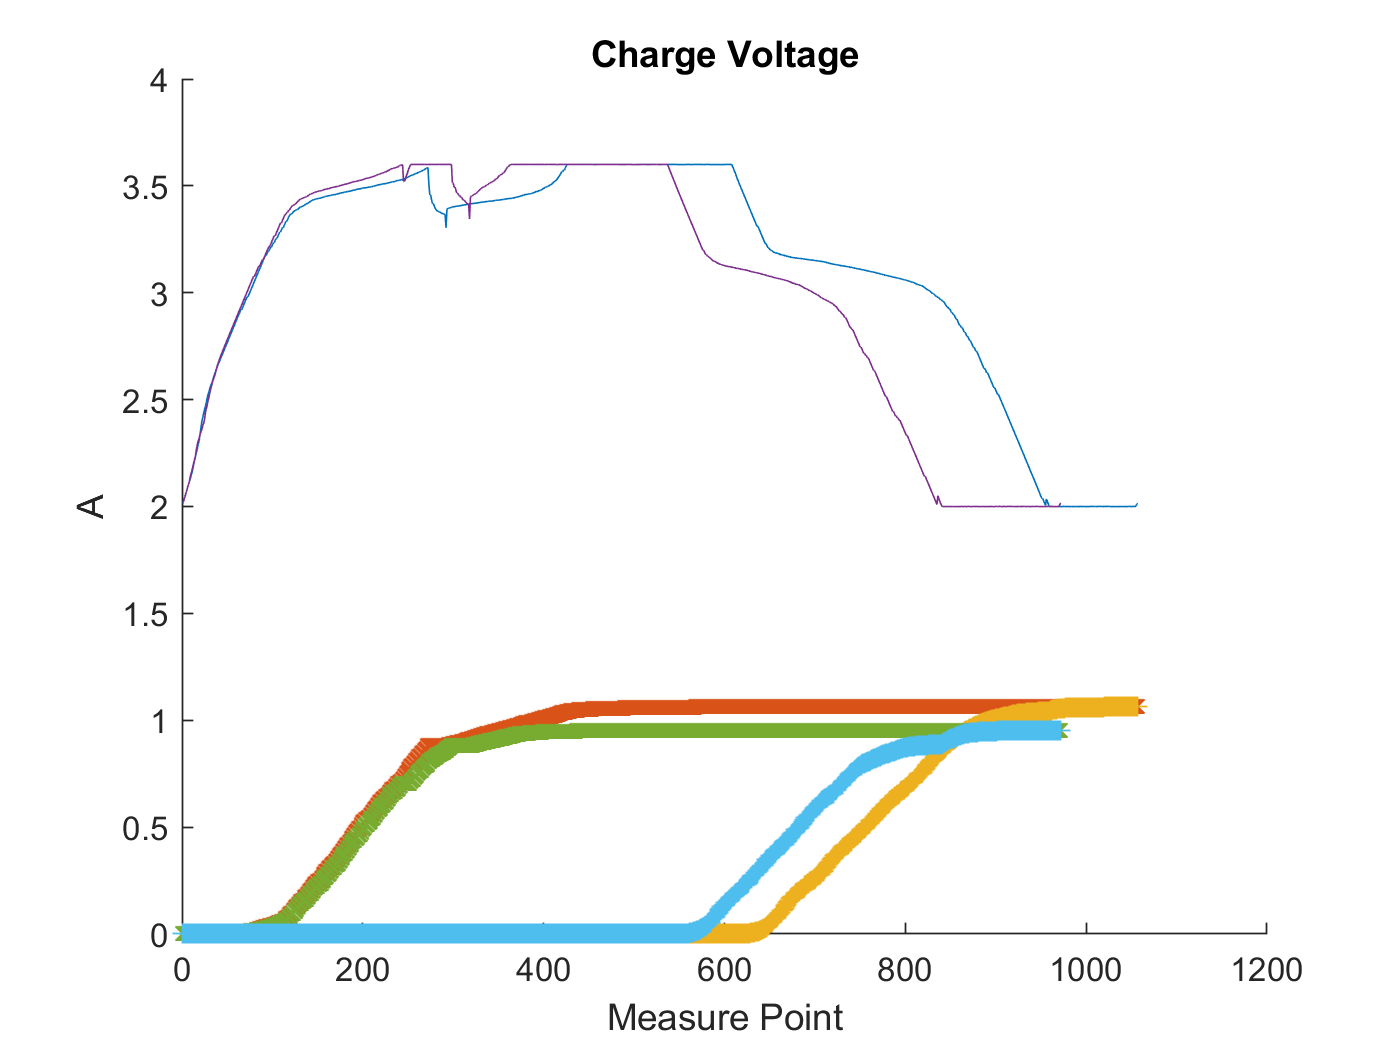

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Voltage'

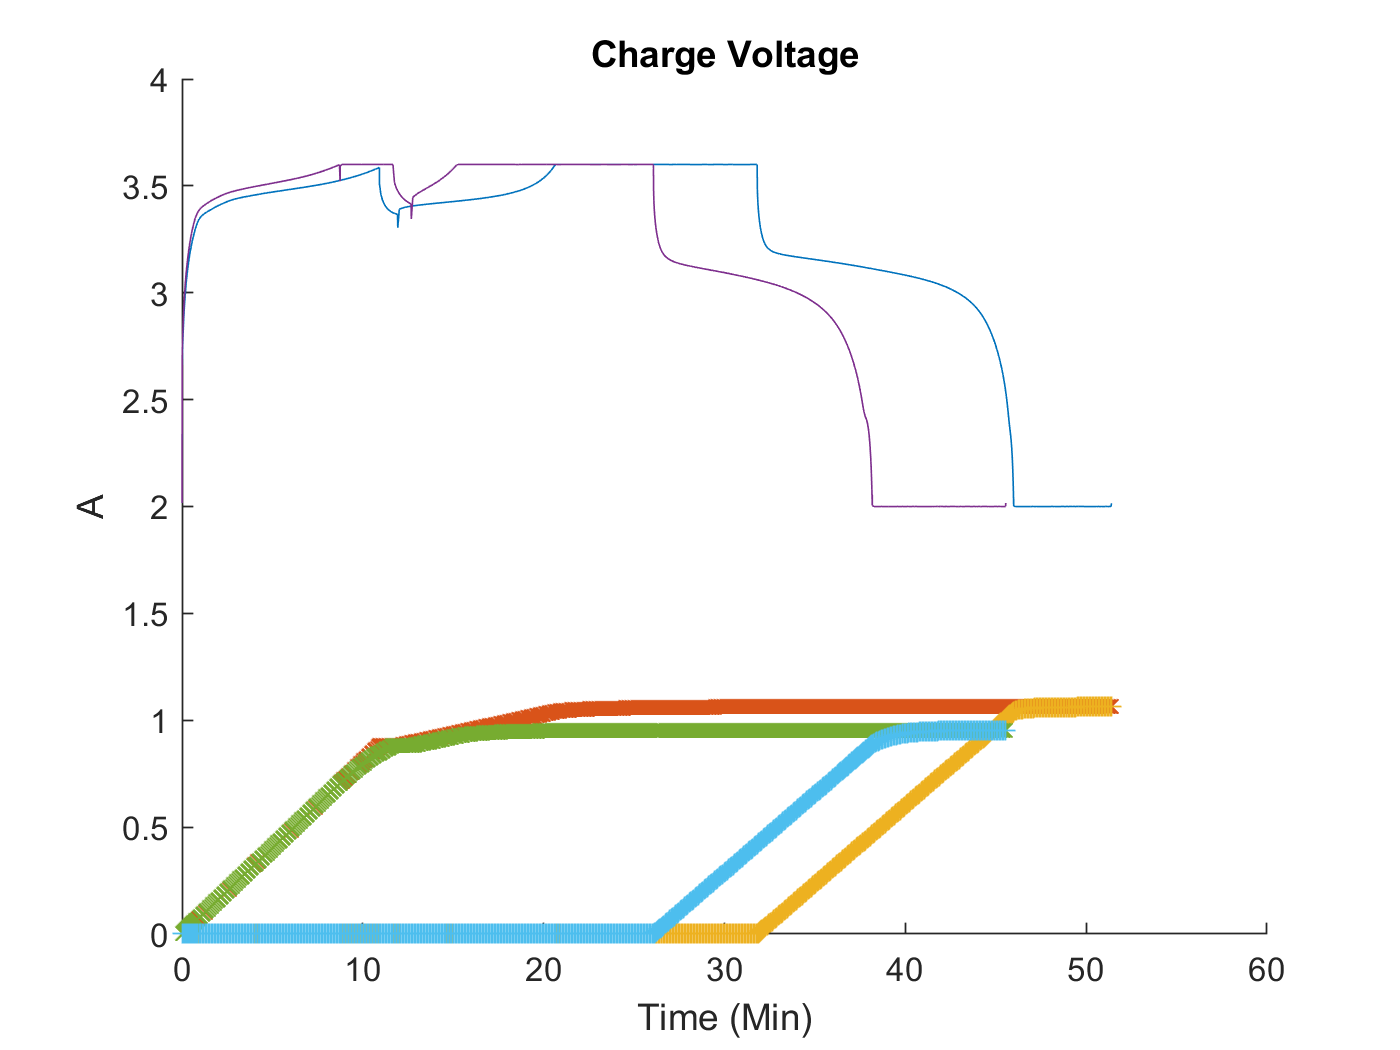

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).V)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Voltage'

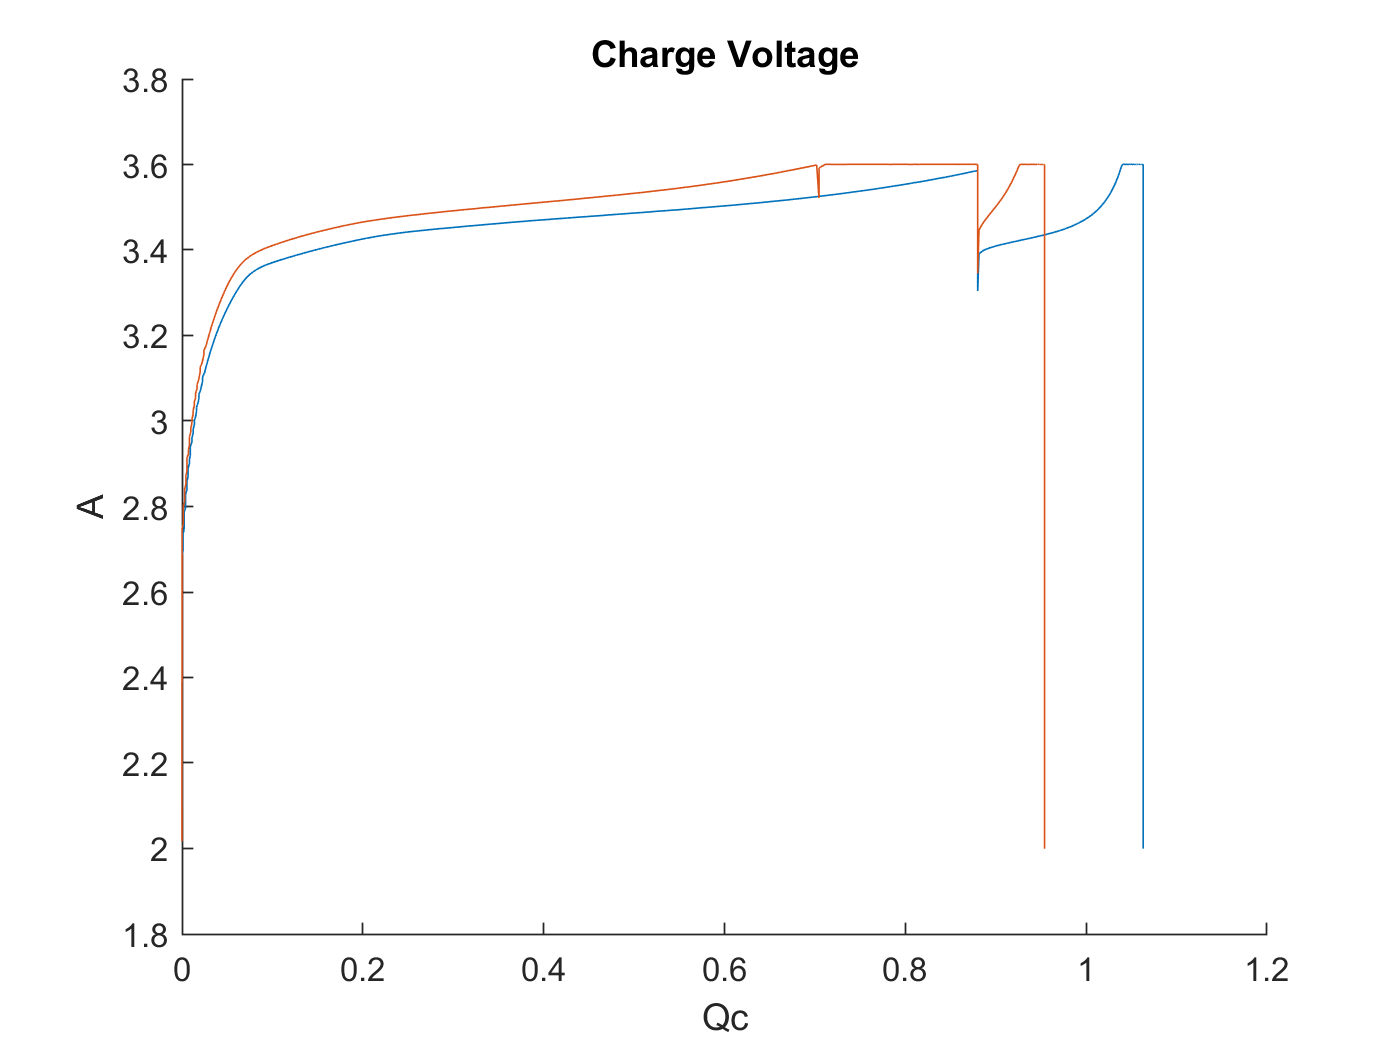


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Voltage'

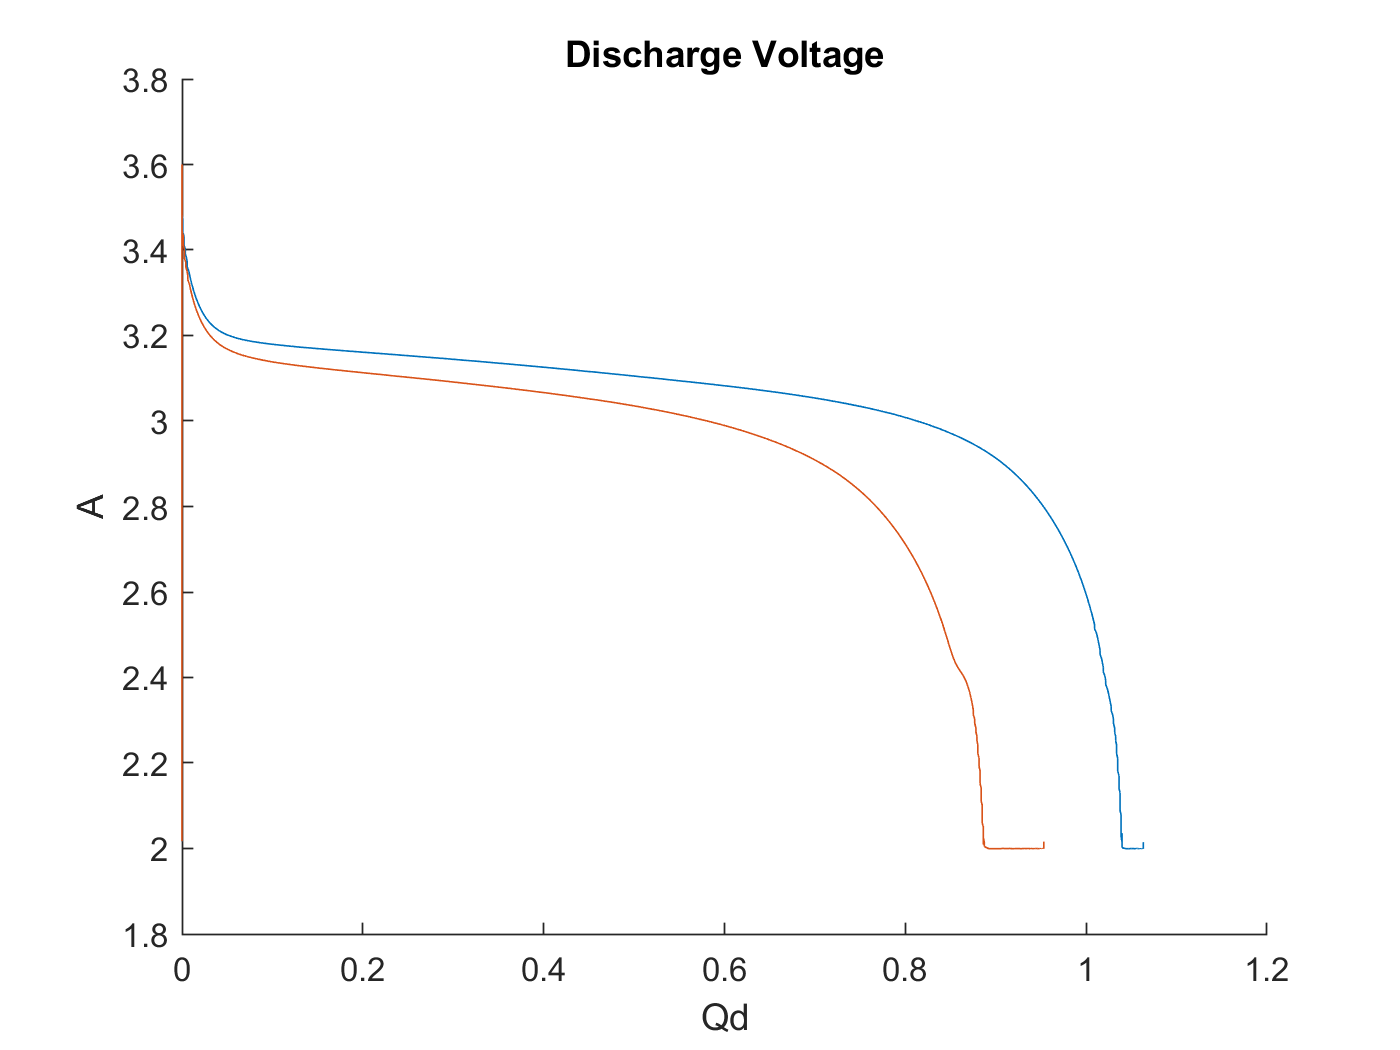


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).V)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Voltage'

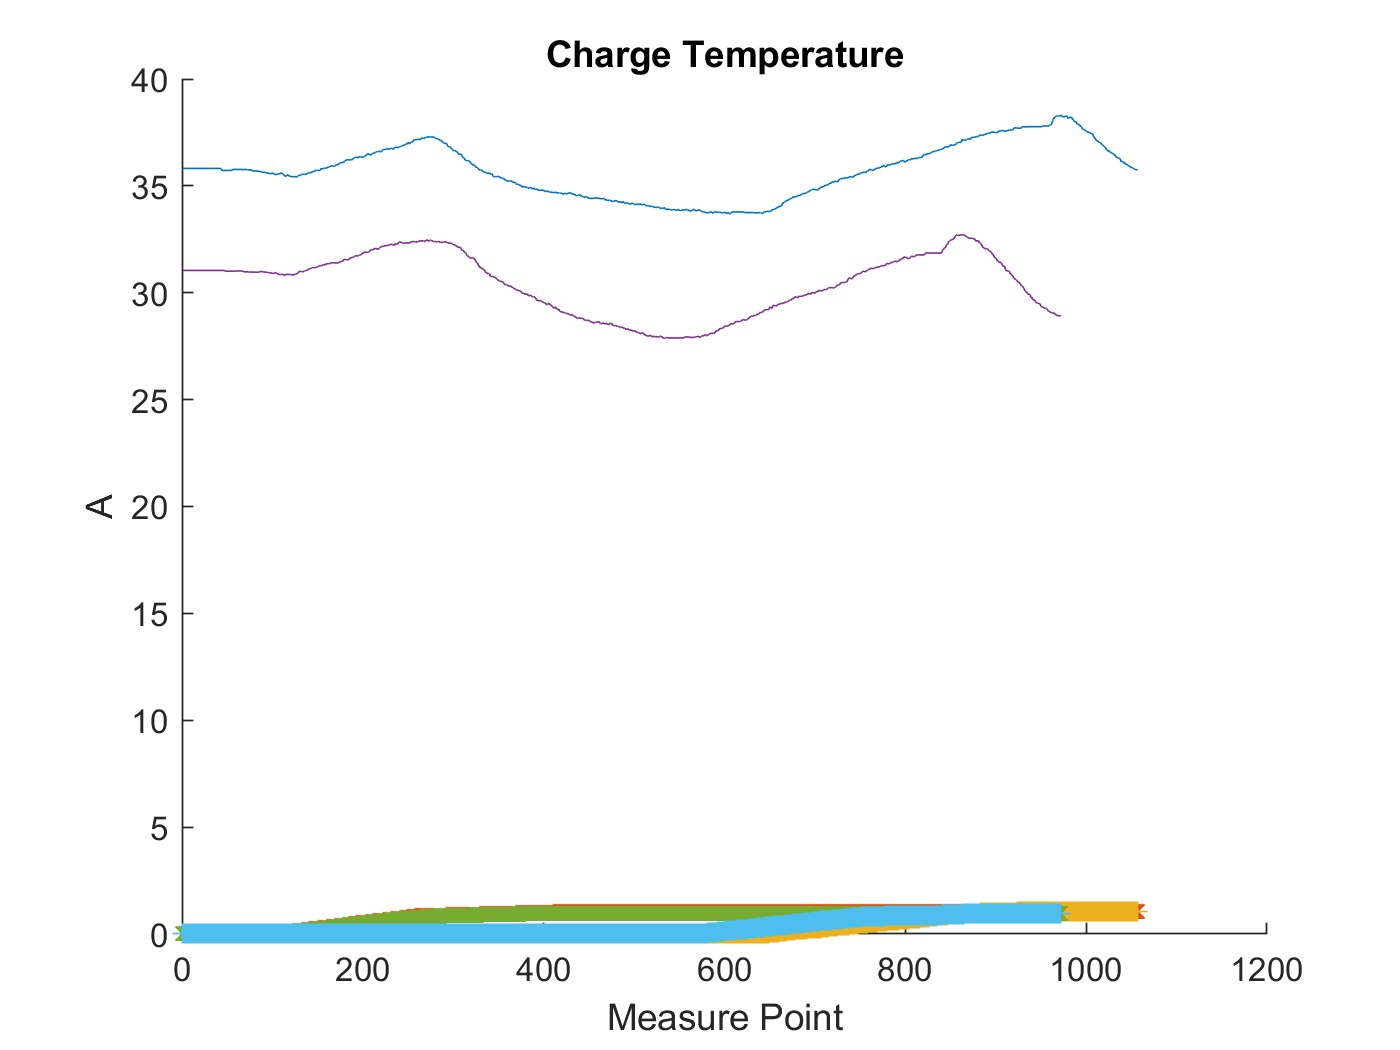

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).Qd,'+')
    end
end
hold off , xlabel 'Measure Point' , ylabel 'A' , title 'Charge Temperature'

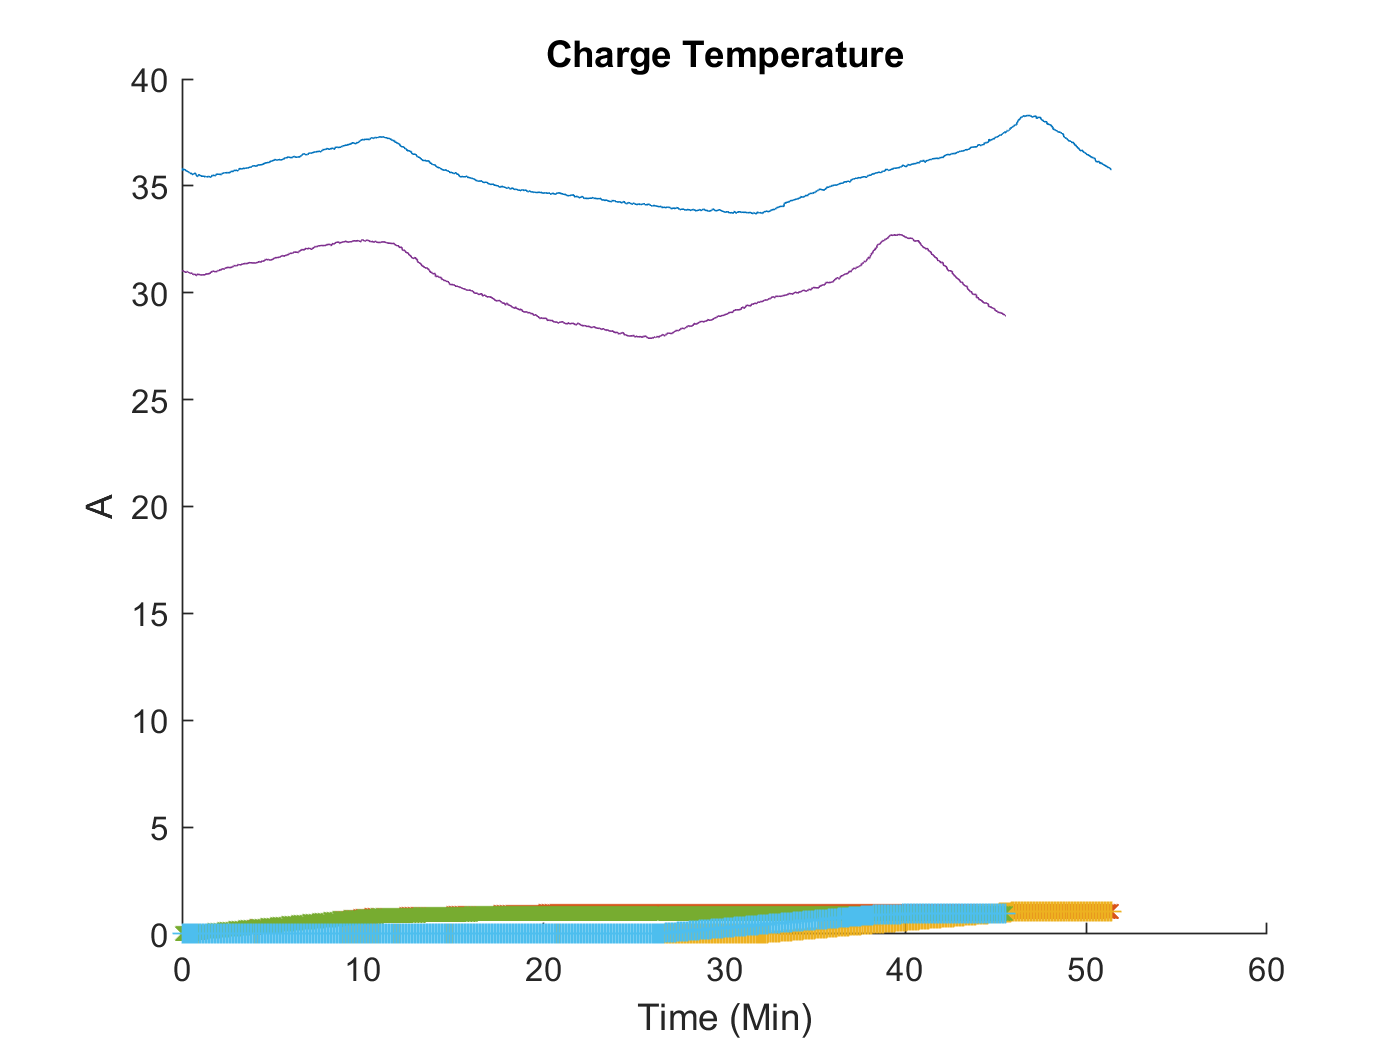

figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).T)
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qc,'x')
        plot(trainData(test_bat).cycles(i).t,trainData(test_bat).cycles(i).Qd,'+')        
    end
end
hold off , xlabel 'Time (Min)' , ylabel 'A' , title 'Charge Temperature'

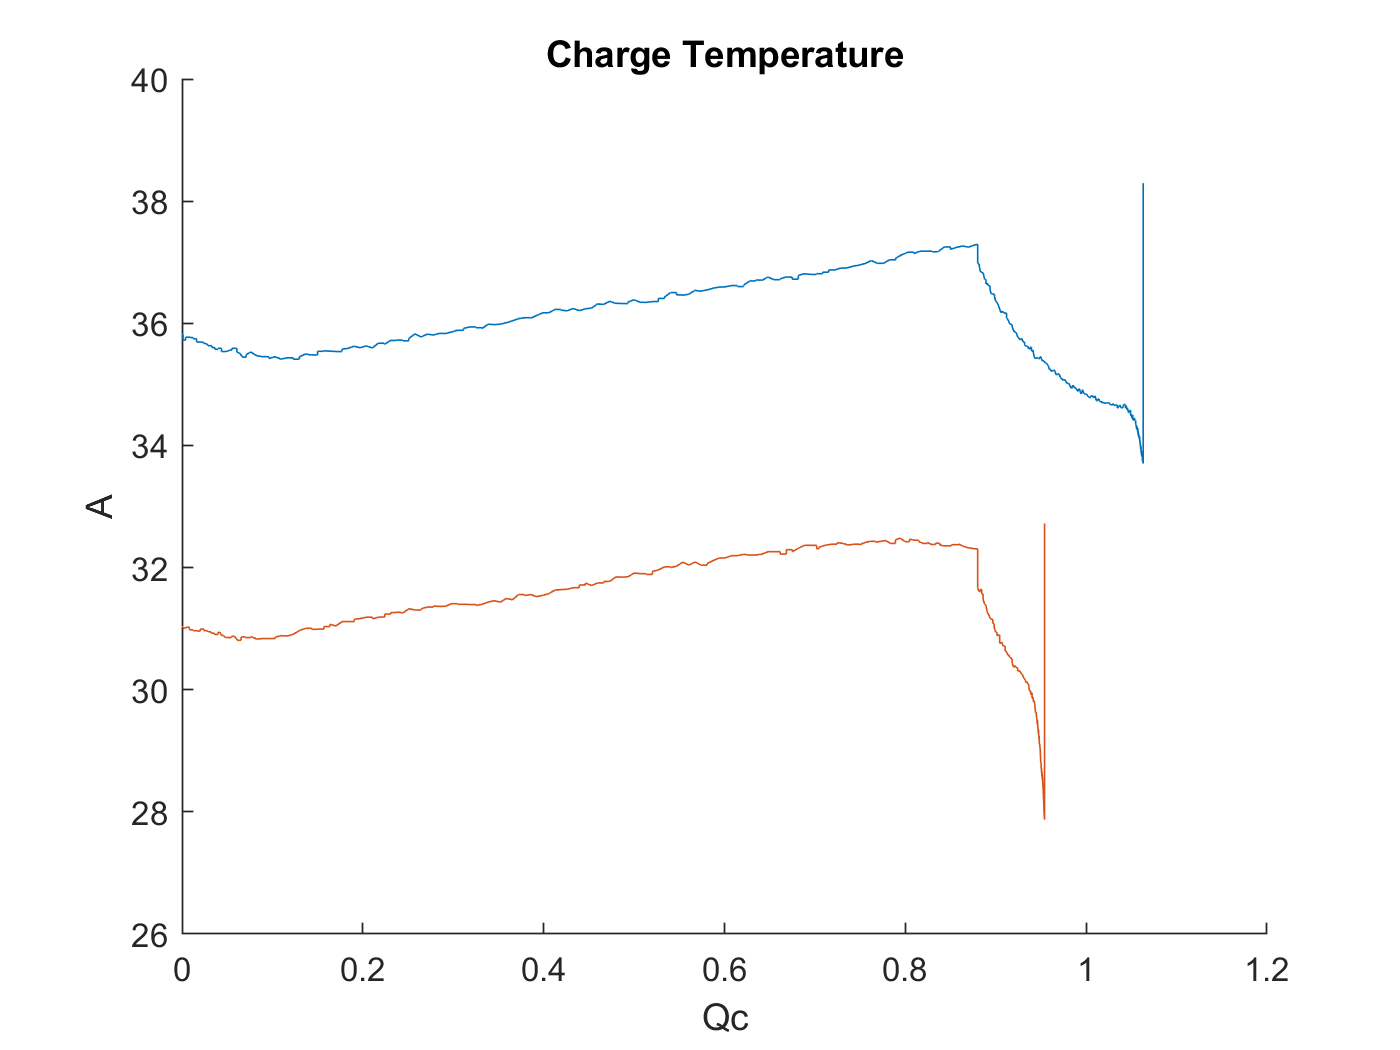


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qc,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qc' , ylabel 'A' , title 'Charge Temperature'

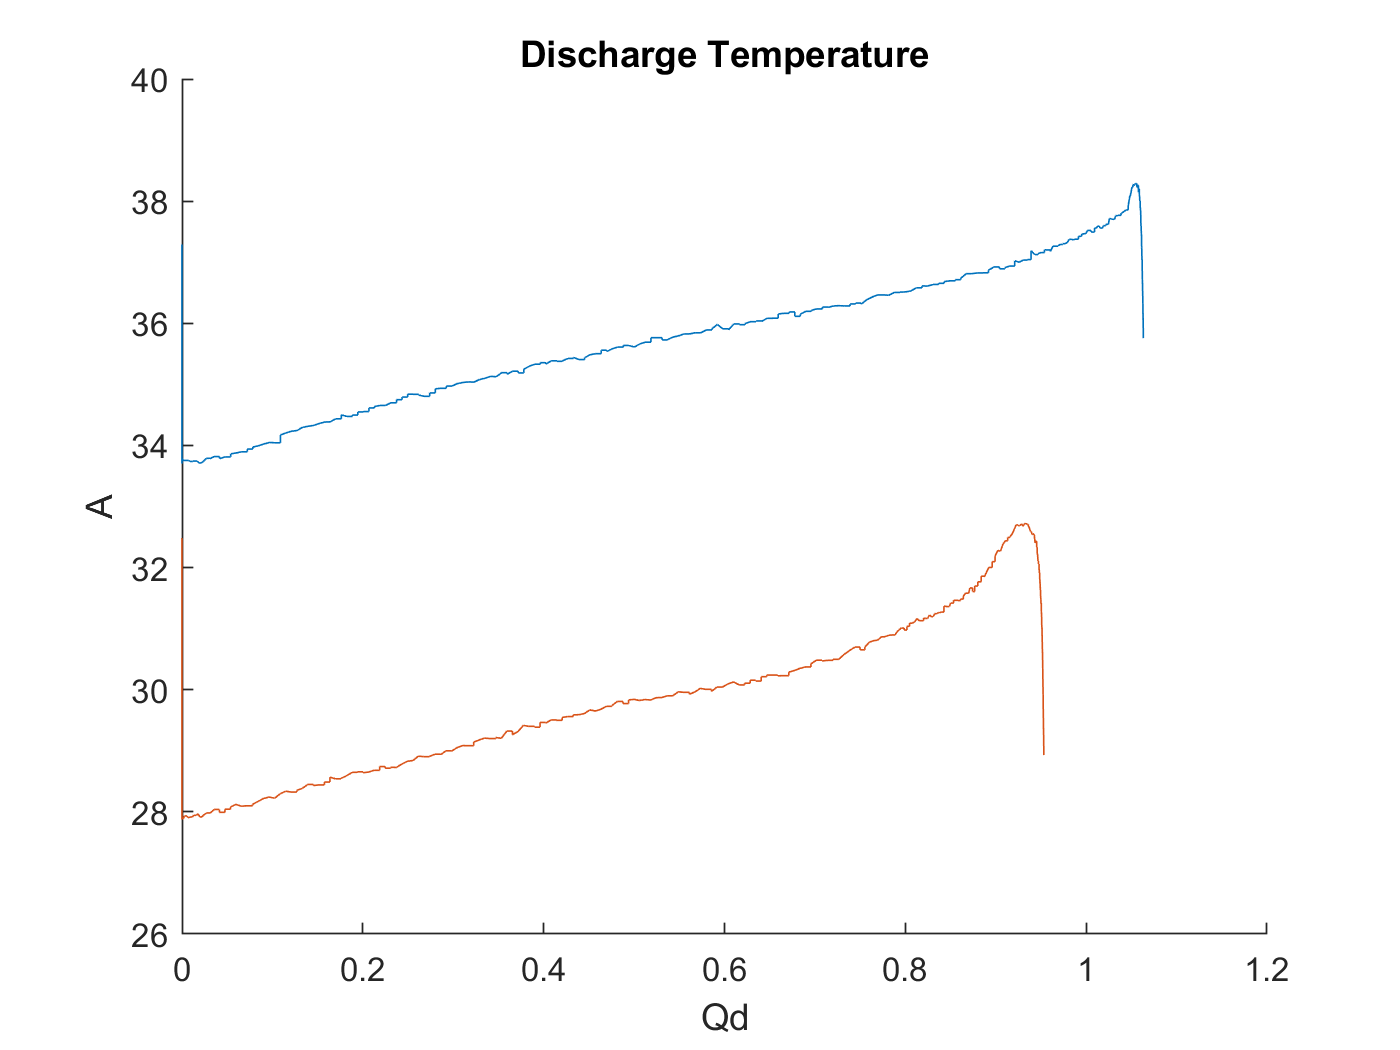


figure , hold on
for i=1:trainData(test_bat).cycle_life
    if rem(i,cycle_div) == 0
        plot(trainData(test_bat).cycles(i).Qd,trainData(test_bat).cycles(i).T)     
    end
end
hold off , xlabel 'Qd' , ylabel 'A' , title 'Discharge Temperature'

데이타중 첫번째 batch에서 하나를 선택해서 데이타 확인



%batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"]
%batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"]
% src = trainData(1); % src has invaild item on index 1
% dest = trainData2(8); % dest has vaild item on index 1
% merge = merge_struct(trainData(1),trainData2(8));

src = trainData(1); % src has invaild item on index 1
dest = trainData2(8); % dest has vaild item on index 1

특정데이타는 다른 batch에 나눠져 있는 경우가 있어서 이를 합쳐야 한다.

merge = merge_struct(trainData(1),trainData2(8));

% verify
src.cycle_life

ans = 1190

dest.cycle_life

ans = 663

src.cycle_life + dest.cycle_life - 1

ans = 1852

merge.cycle_life

ans = 1852

length(src.summary.QDischarge)

ans = 1189

length(dest.summary.QDischarge)

ans = 662

length(merge.summary.QDischarge)

ans = 1851

%%%%%%%%%%%
src.summary.QDischarge(1)

ans = 0

src.summary.QDischarge(2)

ans = 1.0707

src.summary.QDischarge(end-1)

ans = 1.0267

src.summary.QDischarge(end)

ans = 1.0262

%%%%
dest.summary.QDischarge(1)

ans = 1.0219

dest.summary.QDischarge(2)

ans = 1.0233

dest.summary.QDischarge(end-1)

ans = 0.8843

dest.summary.QDischarge(end)

ans = 0.8828

%%%%
merge.summary.QDischarge(1)

ans = 0

merge.summary.QDischarge(2)

ans = 1.0707

merge.summary.QDischarge(length(src.summary.QDischarge)-1)

ans = 1.0267

merge.summary.QDischarge(length(src.summary.QDischarge))

ans = 1.0262

merge.summary.QDischarge(length(src.summary.QDischarge)+1)

ans = 1.0219

merge.summary.QDischarge(length(src.summary.QDischarge)+2)

ans = 1.0233

merge.summary.QDischarge(end-1)

ans = 0.8843

merge.summary.QDischarge(end)

ans = 0.8828

test = zeros();
test = extract_feature_all_new_bat_soc_v4(1,1,merge);

#batch1 = pickle.load(open(r'.\Data\batch1.pkl', 'rb'))

batch1 = pickle.load(open(r'.\batch1.pkl', 'rb'))

#remove batteries that do not reach 80% capacity

del batch1['b1c8']

del batch1['b1c10']

del batch1['b1c12']

del batch1['b1c13']

del batch1['b1c22']

///////////

# There are four cells from batch1 that carried into batch2, we'll remove the data from batch2

# and put it with the correct cell from batch1

batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']

batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']

add_len = [662, 981, 1060, 208, 482];

for i, bk in enumerate(batch1_keys):

    batch1[bk]['cycle_life'] = batch1[bk]['cycle_life'] + add_len[i]

    for j in batch1[bk]['summary'].keys():

        if j == 'cycle':

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j] + len(batch1[bk]['summary'][j])))

        else:

            batch1[bk]['summary'][j] = np.hstack((batch1[bk]['summary'][j], batch2[batch2_keys[i]]['summary'][j]))

    last_cycle = len(batch1[bk]['cycles'].keys())

    for j, jk in enumerate(batch2[batch2_keys[i]]['cycles'].keys()):

        batch1[bk]['cycles'][str(last_cycle + j)] = batch2[batch2_keys[i]]['cycles'][jk]

del batch2['b2c7']

del batch2['b2c8']

del batch2['b2c9']

del batch2['b2c15']

del batch2['b2c16']

new_index = 1;
battery_dataset_v1 = zeros();
% 이 코드가 중요함. battery_dataset_v1 이 structure를 가짐을 알려주어야 함.
battery_dataset_v1 = extract_feature_all_new_bat_soc_v4(1,1,trainData(1));



% 1.1 * 0.8 = 0.88 Ah = EOL
% batch 2 = get data under 0.88 Ah - to remove this data under EOL
test2 = extract_feature_all_new_bat_soc_v4(2,1,trainData2(1));
test1 = extract_feature_all_new_bat_soc_v4(1,1,trainData(1));
test3 = extract_feature_all_new_bat_soc_v4(3,1,trainData3(1));
skip_bat1 = [8 10 12 13 22 ]; % base 0 index
skip_bat1 = skip_bat1 +1; % to 1 index

% # There are four cells from batch1 that carried into batch2, we'll remove the data from batch2
% # and put it with the correct cell from batch1
% batch2_keys = ['b2c7', 'b2c8', 'b2c9', 'b2c15', 'b2c16']
% batch1_keys = ['b1c0', 'b1c1', 'b1c2', 'b1c3', 'b1c4']
% add_len = [662, 981, 1060, 208, 482];

skip_bat2 = [7 8 9 15 16 ]; % base 0 index
skip_bat2 = skip_bat2 +1; % to 1 index

batch2_keys = ["b2c8", "b2c9", "b2c10", "b2c16", "b2c17"];
batch2_fix = [8 9 10 16 17];
batch1_keys = ["b1c1","b1c2","b1c3","b1c4","b1c5"];
batch1_fix = [1 2 3 4 5];

batchNum =1;
for batNum = 1:size(trainData,2)
    if numel(trainData(batNum).summary.cycle) == numel(unique(trainData(batNum).summary.cycle))
        if ismember(batNum,skip_bat1) 
            batNum;
        elseif ismember(batNum,batch1_fix) 
            %ismember(batNum,batch1_fix) % true or fale
            idx = find(batch1_fix==batNum);
            % find(strcmp
%             batch1_fix(idx)
%             batch2_fix(idx)
            src = trainData(batch1_fix(idx));
            dest = trainData2(batch2_fix(idx));
            merge = merge_struct(trainData(batch1_fix(idx)),trainData2(batch2_fix(idx)));
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,merge);
            batNum;      
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

%%%%%%%%%%%%%
batchNum = 2;
for batNum = 1:size(trainData2,2)
    if numel(trainData2(batNum).summary.cycle) == numel(unique(trainData2(batNum).summary.cycle))
        if ismember(batNum,batch2_fix) 
            batNum;
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData2(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end


%%%%%%%%%%%%%%%
batchNum = 3;
skip_bat3 = [37 2 23 32 42 43 ]; % base 0 index
skip_bat3 = skip_bat3 +1; % to 1 index

% # remove noisy channels from batch3
% del batch3['b3c37']
% del batch3['b3c2']
% del batch3['b3c23']
% del batch3['b3c32']
% del batch3['b3c42']
% del batch3['b3c43']

for batNum = 1:size(trainData3,2)
    if numel(trainData3(batNum).summary.cycle) == numel(unique(trainData3(batNum).summary.cycle))
        if ismember(batNum,skip_bat3) 
            batNum;
        else
            battery_dataset_v1(new_index) = extract_feature_all_new_bat_soc_v4(batchNum,batNum,trainData3(batNum));
            new_index = new_index + 1;
            batNum;            
        end
    else
        batchNum
        batNum
    end
end

# 시작  Ah을 고정하자. 이보다 큰 데이타는 모두 지우자.

# 먼저 데이타 하나로 테스트

data_conversion_param = zeros();
data_conversion_param = [0 0 0 0 0 0];

idxAll = (1:length(battery_dataset_v1))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx = idxAll

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


i=1 

i = 1

j = idx(i)

j = 1

battery_dataset_v1(i).QDischargeSmooth(1) 

ans = 1.0795



battery_dataset = zeros()

battery_dataset = 0

battery_dataset = battery_dataset_v1(1)

battery_dataset = struct with fields:
               policy: '4_4C-80PER_4_4C'
      policy_readable: '4.4C(80%)-4.4C'
           channel_id: "7"
           cycle_life: 1072
                  key: "b1c6"
             batchNum: 1
               batNum: 6
           chargetime: [1072×1 double]
                cycle: [1072×1 double]
                   IR: [1072×1 double]
              QCharge: [1072×1 double]
           QDischarge: [1072×1 double]
                 Tavg: [1072×1 double]
                 Tmin: [1072×1 double]
                 Tmax: [1072×1 double]
                Vdlin: [1000×1 double]
                   Vc: [1072×100 double]
                   Tc: [1072×100 double]
                   Vd: [1072×100 double]
                   Td: [1072×100 double]
              VT_leng: 100
                   Ic: [1072×100 double]
                   Id: [1072×100 double]
     QDischargeSmooth: [1072×1 double]
    QDischargePolyMdl: [-9.6874e-13 1.6385e-09 -9.4860e-07 1.5422e-04 1.0742]
    Q

i=1;
for ii = 1:1000
    if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
        % skip count 
        break
    end
end
ii

ii = 644

battery_dataset(i) = battery_dataset_v1(i);
battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
battery_dataset_v1(i).cycle_life

ans = 1072

battery_dataset(i).cycle_life

ans = 428

battery_dataset(i).chargetime([1:ii],:) = [] ;

size(battery_dataset_v1(i).chargetime)

ans =         1072           1


size(battery_dataset(i).chargetime)

ans =    428     1


battery_dataset(i).cycle = [] ;
battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
battery_dataset(i).IR([1:ii],:) = [] ;
battery_dataset(i).QCharge([1:ii],:) = [] ;
battery_dataset(i).QDischarge([1:ii],:) = [] ;
battery_dataset(i).Tavg([1:ii],:) = [] ;
battery_dataset(i).Tmin([1:ii],:) = [] ;
battery_dataset(i).Tmax([1:ii],:) = [] ;
battery_dataset(i).Vc([1:ii],:) = [] ;
battery_dataset(i).Vd([1:ii],:) = [] ;
battery_dataset(i).Tc([1:ii],:) = [] ;
battery_dataset(i).Td([1:ii],:) = [] ;
battery_dataset(i).Ic([1:ii],:) = [] ;
battery_dataset(i).Id([1:ii],:) = [] ;
battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
battery_dataset(i).QDischargePolyMdl = [];
battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
battery_dataset(i).QDischargePolyfit = [];
battery_dataset(i).QDischargePolyfit = polyval(battery_dataset.QDischargePolyMdl,battery_dataset.cycle')';

# 전체 데이타에 대해 특정 Ah보다 큰 것은 모두 지우자 

%%%%%%%%%%%%%%%%%%
% get first capacity
for i = 1:length(idxAll)
    %j = idx(i);
    initC = battery_dataset_v1(i).QDischargeSmooth(1) ;

    for ii = 1:battery_dataset_v1(i).cycle_life
        if battery_dataset_v1(i).QDischargeSmooth(ii) <= 1.048
            % skip count 
            break
        end
        if ii == battery_dataset_v1(i).cycle_life
            error_is = true;
        end
    end
    %              bat_num        new_start_index  
    
    battery_dataset(i) = battery_dataset_v1(i);
    battery_dataset(i).cycle_life = battery_dataset_v1(i).cycle_life - ii;
    %battery_dataset_v1(i).cycle_life
    %battery_dataset(i).cycle_life
    battery_dataset(i).chargetime([1:ii],:) = [] ;

    data_conversion_param(i,:) = [ i      initC  ii   battery_dataset_v1(i).QDischargeSmooth(ii)   battery_dataset_v1(i).cycle_life battery_dataset(i).cycle_life    ];
    
    %size(battery_dataset_v1(i).chargetime)
    %size(battery_dataset(i).chargetime)
    battery_dataset(i).cycle = [] ;
    battery_dataset(i).cycle = battery_dataset_v1(i).cycle(1:end-ii,:);
    battery_dataset(i).IR([1:ii],:) = [] ;
    battery_dataset(i).QCharge([1:ii],:) = [] ;
    battery_dataset(i).QDischarge([1:ii],:) = [] ;
    battery_dataset(i).Tavg([1:ii],:) = [] ;
    battery_dataset(i).Tmin([1:ii],:) = [] ;
    battery_dataset(i).Tmax([1:ii],:) = [] ;
    battery_dataset(i).Vc([1:ii],:) = [] ;
    battery_dataset(i).Vd([1:ii],:) = [] ;
    battery_dataset(i).Ic([1:ii],:) = [] ;
    battery_dataset(i).Id([1:ii],:) = [] ;    
    battery_dataset(i).Tc([1:ii],:) = [] ;
    battery_dataset(i).Td([1:ii],:) = [] ;
    battery_dataset(i).QDischargeSmooth([1:ii],:) = [] ;
    battery_dataset(i).QDischargePolyMdl = [];
    battery_dataset(i).QDischargePolyMdl = polyfit(battery_dataset(i).cycle, battery_dataset(i).QDischargeSmooth,4);
    battery_dataset(i).QDischargePolyfit = [];
    battery_dataset(i).QDischargePolyfit = polyval(battery_dataset(i).QDischargePolyMdl,battery_dataset(i).cycle')';


end
data_conversion_param 

data_conversion_param = 	1.0e+03 *

    0.0010    0.0011    0.6440    0.0010    1.0720    0.4280
    0.0020    0.0011    0.4050    0.0010    0.6340    0.2290
    0.0030    0.0011    0.6150    0.0010    0.8680    0.2530
    0.0040    0.0011    0.7140    0.0010    1.0520    0.3380
    0.0050    0.0011    0.3700    0.0010    0.7860    0.4160
    0.0060    0.0011    0.5470    0.0010    0.8780    0.3310
    0.0070    0.0011    0.4390    0.0010    0.7170    0.2780
    0.0080    0.0011    0.6250    0.0010    0.8600    0.2350
    0.0090    0.0011    0.5710    0.0010    0.8550    0.2840
    0.0100    0.0011    0.2270    0.0010    0.6890    0.4620


max(data_conversion_param(:,2))

ans = 1.0982

min(data_conversion_param(:,2))

ans = 1.0480

length(battery_dataset)

ans = 119

size(battery_dataset)

ans =      1   119


[battery_dataset.key]

ans = 1×119 string array
    "b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"   

{[battery_dataset.key]}

ans = 1×1 cell array
    {["b1c6"    "b1c7"    "b1c8"    "b1c10"    "b1c12"    "b1c15"    "b1c16"    "b1c17"    "b1c18"    "b1c19"    "b1c20"    "b1c21"    "b1c22"    "b1c24"    "b1c25"    "b1c26"    "b1c27"    "b1c28"    "b1c29"    "b1c30"    "b1c31"    "b1c32"    "b1c33"    "b1c34"    "b1c35"    "b1c36"    "b1c37"    "b1c38"    "b1c39"    "b1c40"    "b1c41"    "b1c42"    "b1c43"    "b1c44"    "b1c45"    "b1c46"    "b2c1"    "b2c2"    "b2c3"    "b2c4"    "b2c5"    "b2c6"    "b2c7"    "b2c11"    "b2c12"    "b2c13"    "b2c14"    "b2c15"    "b2c18"    "b2c19"    "b2c20"    "b2c21"    "b2c22"    "b2c23"    "b2c24"    "b2c25"    "b2c26"    "b2c27"    "b2c28"    "b2c29"    "b2c30"    "b2c31"    "b2c32"    "b2c33"    "b2c34"    "b2c35"    "b2c36"    "b2c37"    "b2c38"    "b2c39"    "b2c40"    "b2c41"    "b2c42"    "b2c43"    "b2c44"    "b2c45"    "b2c46"    "b2c47"    "b2c48"    "b3c1"    "b3c2"    "b3c4"    "b3c5"    "b3c6"    "b3c7"    "b3c8"    "b3c9"    "b3c10"    "b3c11"    "b3c12"    "

contains([battery_dataset.key],'b1','IgnoreCase',true)

ans = 1×119 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0


contains([battery_dataset.key],'b2','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1


contains([battery_dataset.key],'b3','IgnoreCase',true)

ans = 1×119 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


idx1 = find(contains([battery_dataset.key],'b1','IgnoreCase',true))

idx1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36


idx2 = find(contains([battery_dataset.key],'b2','IgnoreCase',true))

idx2 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79


idx3 = find(contains([battery_dataset.key],'b3','IgnoreCase',true))

idx3 =     80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119


idx12 = [idx1 idx2]

idx12 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx13 = [idx1 idx3]

idx13 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    80    81    82    83    84    85    86    87    88    89    90    91    92    93


idx23 = [idx2 idx3]

idx23 =     37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86


idxAll = (1:length(battery_dataset))

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx123 = [idx1 idx2 idx3]

idx123 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



key1 = [battery_dataset(idx1).key]'

key1 = 36×1 string array
    "b1c6"
    "b1c7"
    "b1c8"
    "b1c10"
    "b1c12"
    "b1c15"
    "b1c16"
    "b1c17"
    "b1c18"
    "b1c19"
    "b1c20"
    "b1c21"
    "b1c22"
    "b1c24"
    "b1c25"
    "b1c26"
    "b1c27"
    "b1c28"
    "b1c29"
    "b1c30"
    "b1c31"
    "b1c32"
    "b1c33"
    "b1c34"
    "b1c35"
    "b1c36"
    "b1c37"
    "b1c38"
    "b1c39"
    "b1c40"


key2 = [battery_dataset(idx2).key]'

key2 = 43×1 string array
    "b2c1"
    "b2c2"
    "b2c3"
    "b2c4"
    "b2c5"
    "b2c6"
    "b2c7"
    "b2c11"
    "b2c12"
    "b2c13"
    "b2c14"
    "b2c15"
    "b2c18"
    "b2c19"
    "b2c20"
    "b2c21"
    "b2c22"
    "b2c23"
    "b2c24"
    "b2c25"
    "b2c26"
    "b2c27"
    "b2c28"
    "b2c29"
    "b2c30"
    "b2c31"
    "b2c32"
    "b2c33"
    "b2c34"
    "b2c35"


key3 = [battery_dataset(idx3).key]'

key3 = 40×1 string array
    "b3c1"
    "b3c2"
    "b3c4"
    "b3c5"
    "b3c6"
    "b3c7"
    "b3c8"
    "b3c9"
    "b3c10"
    "b3c11"
    "b3c12"
    "b3c13"
    "b3c14"
    "b3c15"
    "b3c16"
    "b3c17"
    "b3c18"
    "b3c19"
    "b3c20"
    "b3c21"
    "b3c22"
    "b3c23"
    "b3c25"
    "b3c26"
    "b3c27"
    "b3c28"
    "b3c29"
    "b3c30"
    "b3c31"
    "b3c32"


cycle_life = [battery_dataset(idxAll).cycle_life]'

cycle_life =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


bat_index = [1:length(idxAll)]'

bat_index =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


index_cyclelife = [ bat_index, cycle_life]

index_cyclelife =      1   428
     2   229
     3   253
     4   338
     5   416
     6   331
     7   278
     8   235
     9   284
    10   462


% https://kr.mathworks.com/help/matlab/ref/double.sortrows.html#bt8bz9j-3
index_cyclelife_table = table(bat_index,cycle_life)

index_cyclelife_table = 119×2 table
    bat_index    cycle_life
    _________    __________

        1           428    
        2           229    
        3           253    
        4           338    
        5           416    
        6           331    
        7           278    
        8           235    
        9           284    
       10           462    
       11           269    
       12           379    
       13           300    
       14           354    
       15           405    
       16           316    


[index_cyclelife_table_sort,index] = sortrows(index_cyclelife_table,{'cycle_life'},{'ascend'})

index_cyclelife_table_sort = 119×2 table
    bat_index    cycle_life
    _________    __________

       38           109    
       78           115    
       71           118    
       69           129    
       65           137    
       76           140    
       61           146    
       74           146    
       73           152    
       66           153    
       70           153    
       64           154    
       68           155    
       75           157    
       63           161    
       48           168    


index =     38
    78
    71
    69
    65
    76
    61
    74
    73
    66



%%%%%%%%%%%%%%%%
total_index = length(idxAll)

total_index = 119

	
index_cyclelife_table_sort.Variables

ans =     38   109
    78   115
    71   118
    69   129
    65   137
    76   140
    61   146
    74   146
    73   152
    66   153


index_cyclelife_table_sort.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'bat_index'  'cycle_life'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


[~, maxrow] = max(index_cyclelife_table_sort.bat_index)

maxrow = 116

%maxrowname = index_cyclelife_table_sort.Properties.RowNames(1:maxrow-1)
%index_cyclelife_table_sort.Properties.RowNames

index_vec = [1:total_index]

index_vec =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxVal_ = index_vec(5:10:end)

idxVal_ =      5    15    25    35    45    55    65    75    85    95   105   115


idxTest_ = index_vec(6:10:end)

idxTest_ =      6    16    26    36    46    56    66    76    86    96   106   116


idxTrain_ = setdiff(index_vec,idxVal_);
idxTrain_ = setdiff(idxTrain_,idxTest_)

idxTrain_ =      1     2     3     4     7     8     9    10    11    12    13    14    17    18    19    20    21    22    23    24    27    28    29    30    31    32    33    34    37    38    39    40    41    42    43    44    47    48    49    50    51    52    53    54    57    58    59    60    61    62


idxTestTable = index_cyclelife_table_sort(idxTest_,{'bat_index'})

idxTestTable = 12×1 table
    bat_index
    _________

        76   
        48   
        62   
        28   
        26   
        47   
        16   
        99   
        92   
       106   
        84   
       119   


idxTrainTable = index_cyclelife_table_sort(idxTrain_,{'bat_index'})

idxTrainTable = 95×1 table
    bat_index
    _________

       38    
       78    
       71    
       69    
       61    
       74    
       73    
       66    
       70    
       64    
       68    
       75    
       52    
       60    
       30    
       36    


idxValTable = index_cyclelife_table_sort(idxVal_,{'bat_index'})

idxValTable = 12×1 table
    bat_index
    _________

        65   
        63   
        56   
        59   
        40   
        11   
        46   
        14   
        94   
        10   
       100   
       115   


idxTest = idxTestTable.Variables'

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxValid = idxValTable.Variables'

idxValid =     65    63    56    59    40    11    46    14    94    10   100   115


idxTrain = idxTrainTable.Variables'

idxTrain =     38    78    71    69    61    74    73    66    70    64    68    75    52    60    30    36    39    54    67    77    35    42    72    21    29    37    58    49    24    25    27    33    53     2    22     8    57    23    55    45     3    17    34    41   109    18     7     9    13    93


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTrainSort = sort(idxTrain)

idxTrainSort =      1     2     3     4     5     6     7     8     9    12    13    15    17    18    19    20    21    22    23    24    25    27    29    30    31    32    33    34    35    36    37    38    39    41    42    43    44    45    49    50    51    52    53    54    55    57    58    60    61    64


idxValidSort = sort(idxValid)

idxValidSort =     10    11    14    40    46    56    59    63    65    94   100   115


idxTestSort = sort(idxTest)

idxTestSort =     16    26    28    47    48    62    76    84    92    99   106   119



%https://kr.mathworks.com/matlabcentral/answers/101996-how-can-i-sort-a-vector-in-a-random-manner-in-matlab

idxTestRand =  idxTest(randperm(length(idxTest)))

idxTestRand =     47    62    84    16    99    26    76    48    28    92   106   119


idxTrainRand =  idxTrain(randperm(length(idxTrain)))

idxTrainRand =    112    77    49    64    42    89    81    72    34    82    20    69    31    79    17    86    54    53    90     9    88    43   108    93     4   114    55    35   116    96    37   102    18    32     5   117    25    36    61    24    22    97   107    78     2    41    19   110    85     6


idxValidRand =  idxValid(randperm(length(idxValid)))

idxValidRand =    115    40    14    11    59    10    65    63    56    94    46   100



%sortrows(idxValTable,{'cycle_life'},{'ascend'})
input_size = 100;


# 첫번째 정제된 데이타

ryan3_gen_data_raw_org_desc = 'ryan3_gen_data_raw_org_desc';
save('ryan3_data_raw_org.mat','ryan3_gen_data_raw_org_desc');
save('ryan3_data_raw_org.mat','battery_dataset_v1' ,'-append')

# 시작 Ah 를 동일하게 맞춘 데이타 

ryan3_gen_data_raw_desc = 'ryan3_gen_data_raw_desc';
save('ryan3_data_raw.mat','ryan3_gen_data_raw_desc');
save('ryan3_data_raw.mat','battery_dataset' ,'-append')

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

a = battery_dataset(idxTest(1)).QDischargeSmooth;
b = battery_dataset(idxTest(end)).QDischargeSmooth;
a1 = battery_dataset(idxTest(2)).QDischargeSmooth;
b1 = battery_dataset(idxTest(end-1)).QDischargeSmooth;

%https://kr.mathworks.com/matlabcentral/answers/146685-find-index-where-value-exceeds-threshold
[idxFirst] = find(a >= 1,1,'last')

idxFirst = 73

[idxLast] = find(b >= 1,1,'last' )

idxLast = 669

idxLast = idxLast + 1

idxLast = 670

a(idxFirst-1)

ans = 1.0019

a(idxFirst)

ans = 1.0007

a(idxFirst+1)

ans = 0.9995


b(idxLast-1)

ans = 1.0001

b(idxLast)

ans = 1.0000

b(idxLast+1)

ans = 0.9998

[idxFirst] = find(a1 >= 1,1,'last')

idxFirst = 91

[idxLast] = find(b1 >= 1,1,'last' )

idxLast = 462

idxLast = idxLast + 1

idxLast = 463

a1(idxFirst-1)

ans = 1.0013

a1(idxFirst)

ans = 1.0004

a1(idxFirst+1)

ans = 0.9995


b1(idxLast-1)

ans = 1.0000

b1(idxLast)

ans = 0.9998

b1(idxLast+1)

ans = 0.9995

idxTestCount = length(idxTest)

idxTestCount = 12

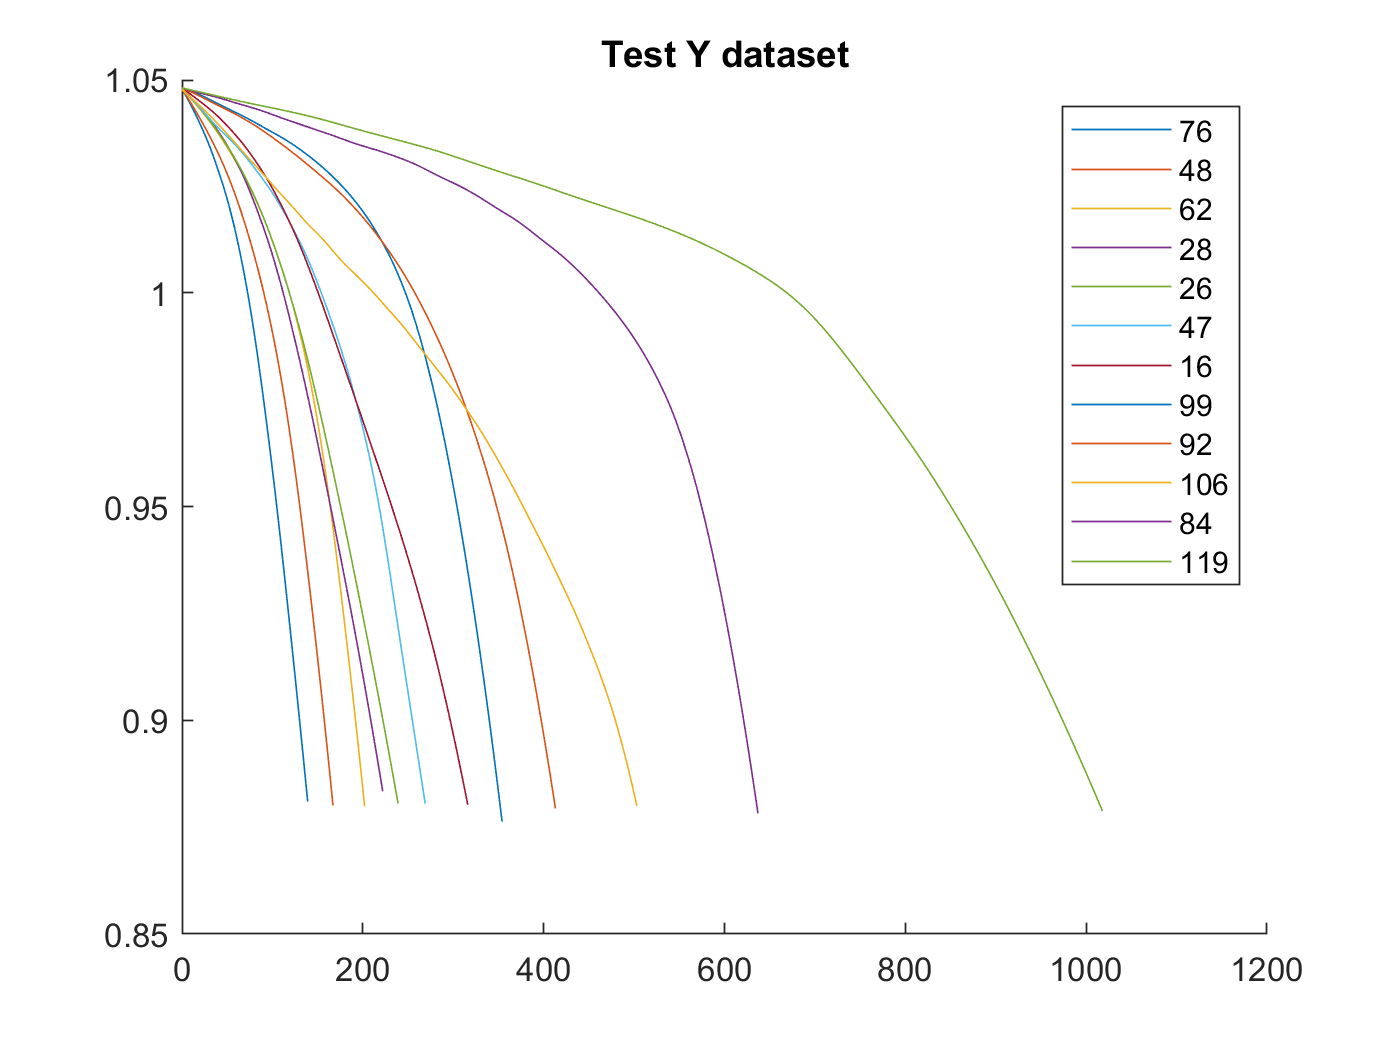


nLines = length(idxTest);
legend_str = cell(nLines,1);

figure
hold on 
for j = 1 : idxTestCount
    i = idxTest(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end
hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list

cycle_life_list =      1    76   140
     2    48   168
     3    62   203
     4    28   222
     5    26   239
     6    47   270
     7    16   316
     8    99   355
     9    92   414
    10   106   504


battery_testset_org = zeros();
battery_testset_org = battery_dataset(idxTest(1));
idxTestCount = length(idxTest)

idxTestCount = 12

idxTestStopCount = idxTestCount / 2 

idxTestStopCount = 6

idxTestReverse = idxTestCount

idxTestReverse = 12

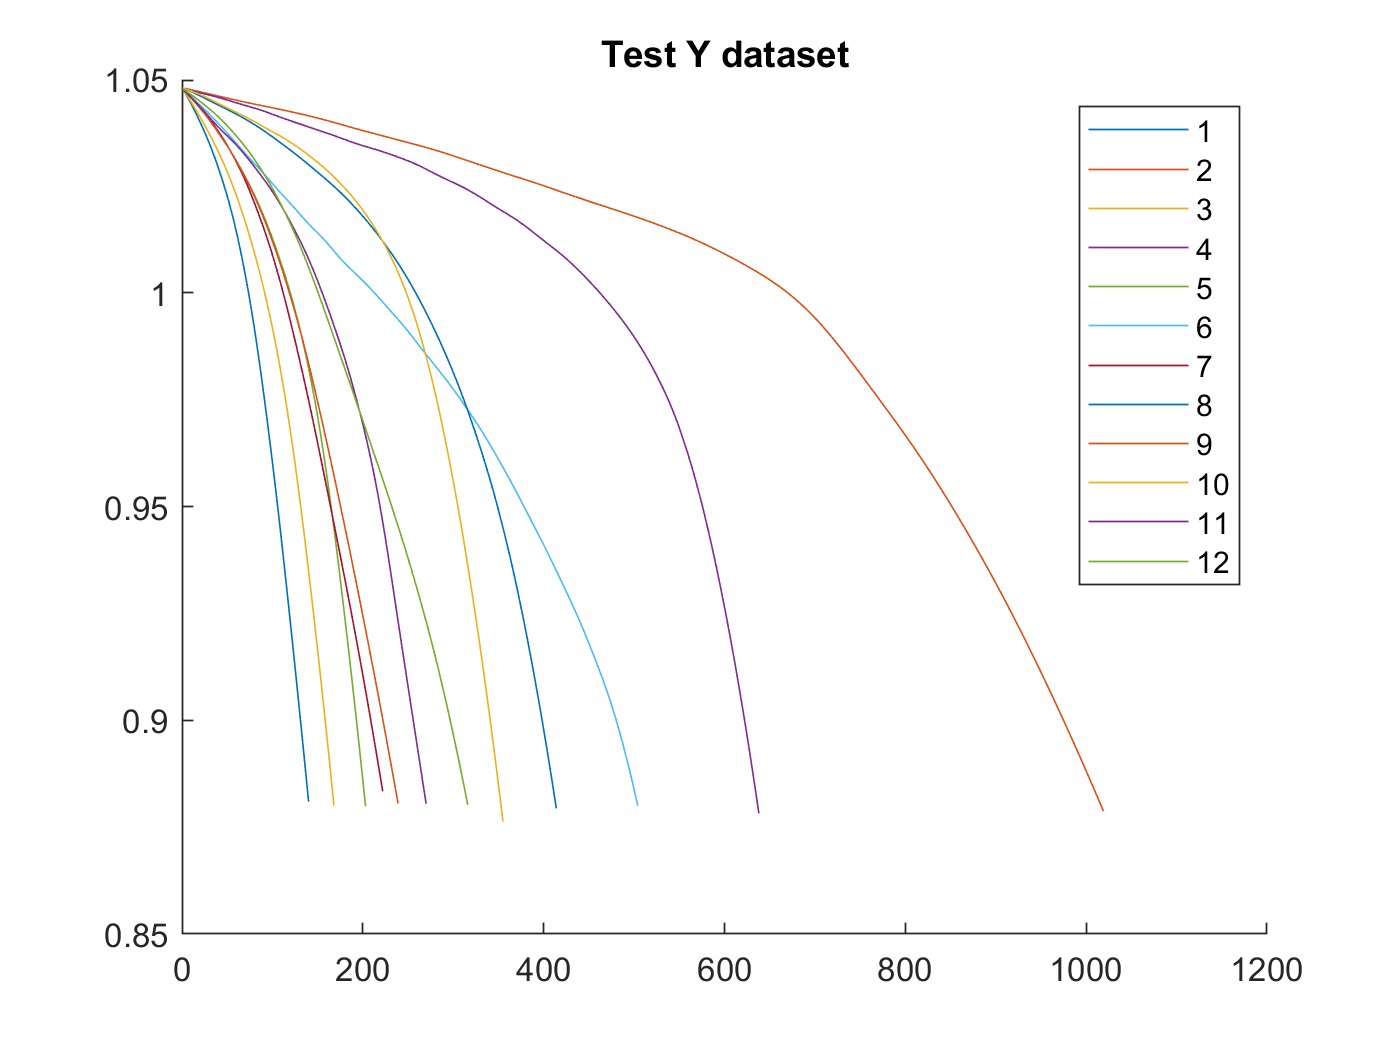

k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);
    post = idxTest(idxTestReverse);
    idxTestReverse = idxTestReverse - 1;
    battery_testset_org(k,:) = battery_dataset(pre);
    k=k+1;
    battery_testset_org(k,:) = battery_dataset(post);
    k=k+1;
end

cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset_org,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines
    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)
    plot(battery_testset_org(i).QDischargeSmooth)
    cycle_life_list(i,:) = [i i battery_testset_org(i).cycle_life];
    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list_org = cycle_life_list

cycle_life_list_org =            1           1         140
           2           2        1019
           3           3         168
           4           4         638
           5           5         203
           6           6         504
           7           7         222
           8           8         414
           9           9         239
          10          10         355


battery_testset = zeros();
battery_testset = battery_dataset(idxTest(1));
%bat_pre = battery_dataset(idxTest(1))
%bat_post = battery_dataset(idxTest(12))
%battery_testset = bat_pre

idxTestCount = length(idxTest)

idxTestCount = 12

idxTestStopCount = idxTestCount / 2 

idxTestStopCount = 6

idxTestReverse = idxTestCount

idxTestReverse = 12

k = 1;
kk = idxTestCount;
for j = 1 : idxTestStopCount
    pre = idxTest(j);
    post = idxTest(idxTestReverse);
    idxTestReverse = idxTestReverse - 1;
    
    %battery_dataset(pre).QDischargeSmooth
    %cycle_life_list(j,:) = [j pre battery_dataset(pre).cycle_life];
    %legend_str{j} = num2str(pre);
    
    [idxPre] = find(battery_dataset(pre).QDischargeSmooth >= 1,1,'last');
    [idxPost] = find(battery_dataset(post).QDischargeSmooth >= 1,1,'last' );
    idxPost = idxPost + 1;
    idxPreAfter = idxPre + 1;
    idxPreBefore = idxPre ;
    idxPostBefore = idxPost -1;
    idxPostAfter = idxPost ;
    
    battery_testset(k,:) = battery_dataset(pre);
    
    battery_testset(k).IR([idxPreAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tavg([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPreAfter:end],:) = [] ;
    battery_testset(k).Vc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPreAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPreAfter:end],:) = [] ;
    battery_testset(k).Td([idxPreAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPreAfter:end],:) = [] ;
    battery_testset(k).Id([idxPreAfter:end],:) = [] ;
    battery_testset(k).chargetime([idxPreAfter:end],:) = [] ;
    battery_testset(k).QDischargeSmooth([idxPreAfter:end],:) = [] ;
    
    battery_testset(k).IR = vertcat(battery_testset(k).IR,battery_dataset(post).IR([idxPost:end],:)) ;
    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,battery_dataset(post).QCharge([idxPost:end],:)) ;
    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,battery_dataset(post).QDischarge([idxPost:end],:)) ;
    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,battery_dataset(post).Tavg([idxPost:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,battery_dataset(post).Tmin([idxPost:end],:)) ;
    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,battery_dataset(post).Tmax([idxPost:end],:)) ;
    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,battery_dataset(post).Vc([idxPost:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,battery_dataset(post).Vd([idxPost:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,battery_dataset(post).Tc([idxPost:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,battery_dataset(post).Td([idxPost:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,battery_dataset(post).Ic([idxPost:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,battery_dataset(post).Id([idxPost:end],:)) ;
    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,battery_dataset(post).chargetime([idxPost:end],:)) ;
    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,battery_dataset(post).QDischargeSmooth([idxPost:end],:)) ;
    
    battery_testset(k).cycle_life = idxPre +  (battery_dataset(post).cycle_life - idxPost  ) + 1 ;
    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';

%%%%%%%%%%%%%%%
    k = k+1;
    battery_testset(k,:) = battery_dataset(post);
    
    battery_testset(k).IR([idxPostAfter:end],:) = [] ;
    battery_testset(k).QCharge([idxPostAfter:end],:) = [] ;
    battery_testset(k).QDischarge([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tavg([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmin([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tmax([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vc([idxPostAfter:end],:) = [] ;
    battery_testset(k).Vd([idxPostAfter:end],:) = [] ;
    battery_testset(k).Tc([idxPostAfter:end],:) = [] ;
    battery_testset(k).Td([idxPostAfter:end],:) = [] ;
    battery_testset(k).Ic([idxPostAfter:end],:) = [] ;
    battery_testset(k).Id([idxPostAfter:end],:) = [] ;
    battery_testset(k).chargetime([idxPostAfter:end],:) = [] ;
    battery_testset(k).QDischargeSmooth([idxPostAfter:end],:) = [] ;
    
    battery_testset(k).IR = vertcat(battery_testset(k).IR,battery_dataset(pre).IR([idxPreAfter:end],:)) ;
    battery_testset(k).QCharge = vertcat(battery_testset(k).QCharge,battery_dataset(pre).QCharge([idxPreAfter:end],:)) ;
    battery_testset(k).QDischarge = vertcat(battery_testset(k).QDischarge,battery_dataset(pre).QDischarge([idxPreAfter:end],:)) ;
    battery_testset(k).Tavg = vertcat(battery_testset(k).Tavg,battery_dataset(pre).Tavg([idxPreAfter:end],:)) ;
    battery_testset(k).Tmin = vertcat(battery_testset(k).Tmin,battery_dataset(pre).Tmin([idxPreAfter:end],:)) ;
    battery_testset(k).Tmax = vertcat(battery_testset(k).Tmax,battery_dataset(pre).Tmax([idxPreAfter:end],:)) ;
    battery_testset(k).Vc = vertcat(battery_testset(k).Vc,battery_dataset(pre).Vc([idxPreAfter:end],:)) ;
    battery_testset(k).Vd = vertcat(battery_testset(k).Vd,battery_dataset(pre).Vd([idxPreAfter:end],:)) ;
    battery_testset(k).Tc = vertcat(battery_testset(k).Tc,battery_dataset(pre).Tc([idxPreAfter:end],:)) ;
    battery_testset(k).Td = vertcat(battery_testset(k).Td,battery_dataset(pre).Td([idxPreAfter:end],:)) ;
    battery_testset(k).Ic = vertcat(battery_testset(k).Ic,battery_dataset(pre).Ic([idxPreAfter:end],:)) ;
    battery_testset(k).Id = vertcat(battery_testset(k).Id,battery_dataset(pre).Id([idxPreAfter:end],:)) ;
    battery_testset(k).chargetime = vertcat(battery_testset(k).chargetime,battery_dataset(pre).chargetime([idxPreAfter:end],:)) ;
    battery_testset(k).QDischargeSmooth = vertcat(battery_testset(k).QDischargeSmooth,battery_dataset(pre).QDischargeSmooth([idxPreAfter:end],:)) ;
    
    battery_testset(k).cycle_life = idxPost +  (battery_dataset(pre).cycle_life - idxPre  ) + 1 ;
    battery_testset(k).cycle = [];
    battery_testset(k).cycle = linspace(1,battery_testset(k).cycle_life,battery_testset(k).cycle_life) ;

    battery_testset(k).QDischargePolyMdl = [];
%    battery_testset(k).QDischargePolyMdl = polyfit(battery_testset(k).cycle, battery_testset(k).QDischargeSmooth,4);
    battery_testset(k).QDischargePolyfit = [];
%    battery_testset(k).QDischargePolyfit = polyval(battery_testset.QDischargePolyMdl,battery_testset.cycle')';
    k = k +1;
end
%battery_testset



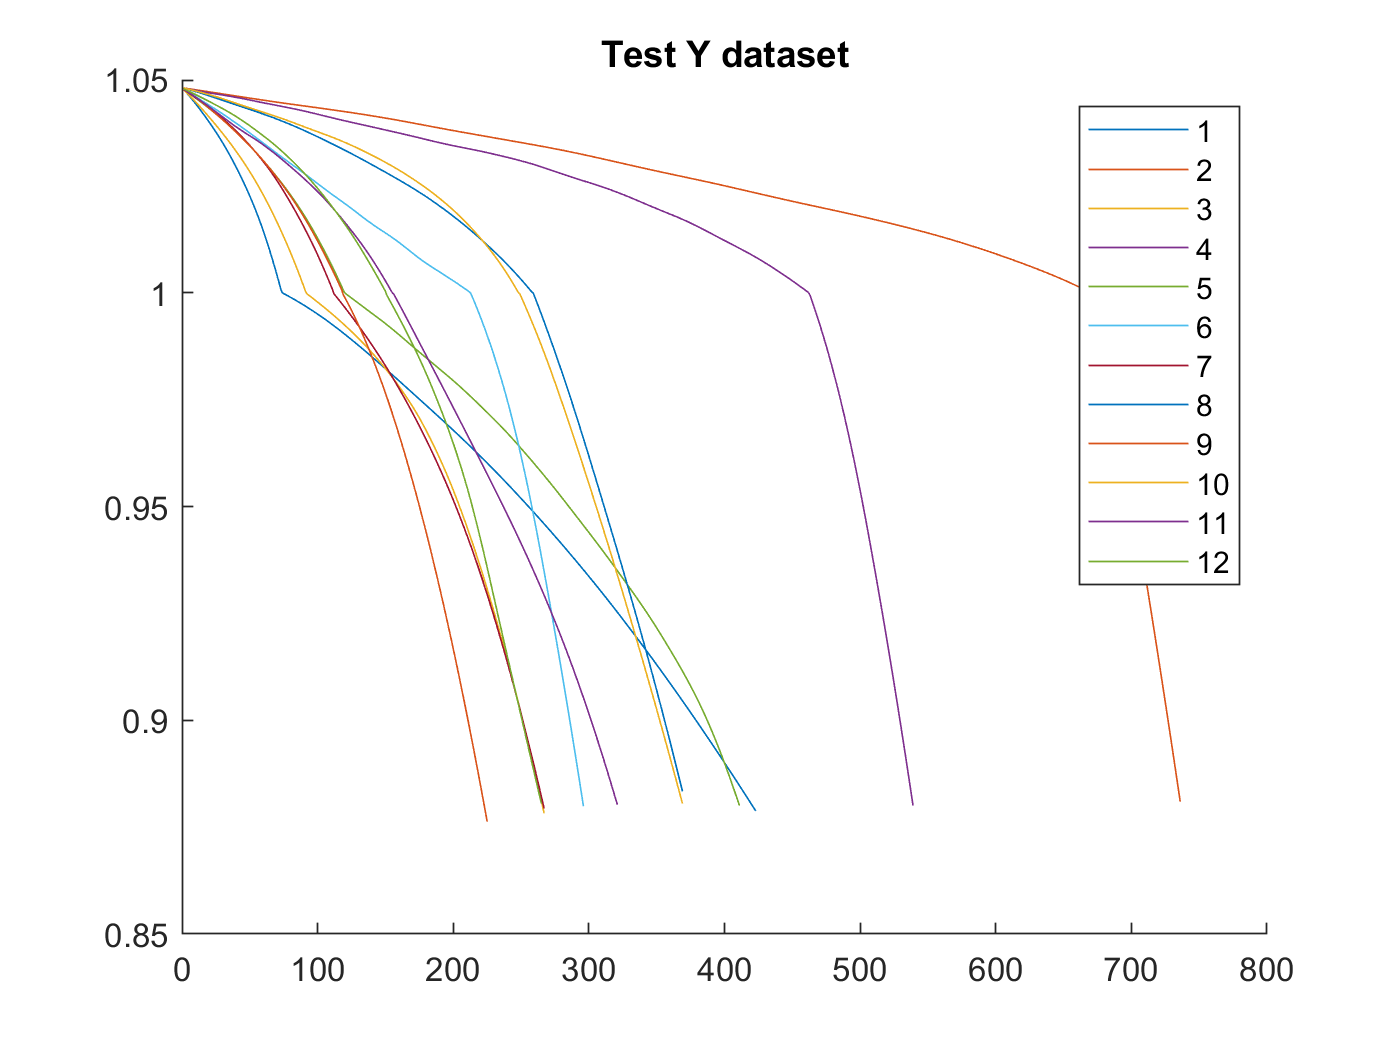


cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = size(battery_testset,1);
legend_str = cell(nLines,1);
figure
hold on 
for i = 1 : nLines
    %plot(battery_testset(i).cycle,battery_testset(i).QDischargeSmooth)
    plot(battery_testset(i).QDischargeSmooth)
    cycle_life_list(i,:) = [i i battery_testset(i).cycle_life];
    legend_str{i} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)

cycle_life_list_change = cycle_life_list

cycle_life_list_change =      1     1   423
     2     2   738
     3     3   267
     4     4   541
     5     5   411
     6     6   298
     7     7   267
     8     8   371
     9     9   225
    10    10   371


%{
cycle_life_list = zeros();
cycle_life_list =  [ 1 1 1 ] ;

nLines = length(idxTestSort);
legend_str = cell(nLines,1);
figure
hold on 
for j = 1 : length(idxTestSort)
    i = idxTestSort(j);
    plot(battery_dataset(i).cycle,battery_dataset(i).QDischargeSmooth)
    cycle_life_list(j,:) = [j i battery_dataset(i).cycle_life];
    legend_str{j} = num2str(i);
end

hold off
title 'Test Y dataset'
legend(legend_str)
cycle_life_list
%}


save('ryan3_data.mat','battery_testset' ,'-append')
save('ryan3_data.mat','battery_testset_org' ,'-append')

% load ryan3_gen_data.mat

첫번째 cycle의 충전전류를 얻는다.

idx = 1; % idxAll; 

battery_dataset(idx).Ic

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002   

battery_dataset(idx).Ic(1,:)

ans =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999


% 열벡터로 바꾼다.
Ic1 = battery_dataset(idx).Ic(1,:)'

Ic1 =          0
    4.3998
    4.4002
    4.4002
    4.4003
    4.3998
    4.3999
    4.4003
    4.4001
    4.4003


% 전체 데이타에 대해서 
IcFirstFull = zeros()

IcFirstFull = 0

IcFirstFull = battery_dataset(1).Ic(1,:)

IcFirstFull =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999



VdFirstFull = zeros()

VdFirstFull = 0

VdFirstFull = battery_dataset(1).Vd(1,:)

VdFirstFull =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549



%IcFirstFull = battery_dataset(2).Ic(1,:)
for i=1:length(battery_dataset)
    IcFirstFull(i,:) = battery_dataset(i).Ic(1,:);
    VdFirstFull(i,:) = battery_dataset(i).Vd(1,:);
end
IcFirstFull

IcFirstFull =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.7998    4.8001    4.8002    4.8000    4.8001    4.8000    4.8000    4.8001    4.8002    4.8000    4.7999    4.8002    4.8000    4.8000    4.8002    4.7998    4.8001    4.7998    4.8000    4.7997    4.7998    4.8000    4.8002    4.8000    4.7999    4.8000    4.8002    4.8001    4.8000    4.8001    4.8001    4.8000    4.8000    4.7999    4.8000    4.8003    4.8000    4.8001    4.8001    4.7998    4.7999    4.7999    4.8001    4.8002    4.8001    4.8001    4.8002    4

VdFirstFull

VdFirstFull =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0188    3.2973    3.2344    3.2033    3.1867    3.1767    3.1702    3.1653    3.1614    3.1581    3.1553    3.1527    3.1502    3.1479    3.1458    3.1435    3.1414    3.1393    3.1372    3.1351    3.1329    3.1306    3.1285    3.1262    3.1240    3.1215    3.1193    3.1167    3.1143    3.1120    3.1094    3.1068    3.1042    3.1015    3.0988    3.0961    3.0933    3.0904    3.0876    3.0849    3.0817    3.0787    3.0757    3.0727    3.0693    3.0662    3.0628    3.0593    3

%IcFirstFull = IcFirstFull'
RulFirst = [battery_dataset(idxAll).cycle_life ]'

RulFirst =    428
   229
   253
   338
   416
   331
   278
   235
   284
   462


blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


IcFirst = blockproc(IcFirstFull, blockSize, meanFilterFunction)

IcFirst =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.8400    4.8001    4.8000    4.8000    4.7999    4.8000    4.8000    4.8001    4.8000    4.8001    4.8000    4.8001    4.8000    4.4582    2.8282    1.0001    0.9867    0.0870         0         0
    3.8400    4.8000    4.7999    4.8000    4.8000    4.8000    4.8000    4.8000    4.8001    4.8000    4.7999    4.7999    4.7999    3.7292    2.8255    0.9999    0.9703    0.0923         0         0
    4.3201    5.3998    5.3999    5.3997    5.4000    5.4000    5.3997    4.3200    3.6001    3.6001    3.6000    3.6001    3.6000    3.6001    2.5600    1.0000    0.9999    0.1030         0         0
    4.3195    5.3999    5.3999    5.4003    5.3998    5.4005    5.4000    5.4000    5.4002    3.4801    2.9999    2.9999    3.0000    3.0000    2.2000    1.0001    1.0000    0.0783      

VdFirst = blockproc(VdFirstFull, blockSize, meanFilterFunction)

VdFirst =     2.9865    3.1652    3.1497    3.1389    3.1285    3.1174    3.1053    3.0921    3.0779    3.0619    3.0428    3.0185    2.9853    2.9360    2.8528    2.6893    2.2963    1.9998    1.9998    1.9998
    2.9881    3.1663    3.1504    3.1393    3.1284    3.1168    3.1042    3.0905    3.0756    3.0591    3.0390    3.0134    2.9786    2.9275    2.8438    2.6867    2.3276    1.9999    1.9999    1.9999
    2.9903    3.1685    3.1520    3.1408    3.1303    3.1191    3.1070    3.0936    3.0791    3.0625    3.0426    3.0171    2.9817    2.9267    2.8285    2.6203    2.1649    2.0000    1.9999    1.9999
    2.9909    3.1700    3.1546    3.1442    3.1341    3.1234    3.1117    3.0989    3.0849    3.0696    3.0514    3.0283    2.9967    2.9485    2.8656    2.6950    2.2574    2.0002    2.0003    2.0003
    2.9949    3.1804    3.1659    3.1554    3.1449    3.1338    3.1216    3.1085    3.0945    3.0797    3.0625    3.0412    3.0134    2.9731    2.9054    2.7688    2.3977    2.0001    2.

%RulFirst = cycleLife;
%clear cycleLife


[ynorm_IcFirst_RUL,ymax_IcFirst_RUL,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xnorm_IcFirstFull_RUL,xmax_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL] = ...
minmax_norm_new(RulFirst,IcFirstFull);
[ynorm_IcFirst_RUL1,xnorm_IcFirst_RUL] = minmax_norm_new_with_param(RulFirst,IcFirst,ymin_IcFirst_RUL,yrate_IcFirst_RUL,xmin_IcFirst_RUL,xrate_IcFirst_RUL);
% https://stackoverflow.com/questions/40053450/compare-if-two-vectors-are-the-same
returnsTrue = all(ynorm_IcFirst_RUL == ynorm_IcFirst_RUL1)

returnsTrue = logical
   1


[ynorm_VdFirst_RUL,ymax_VdFirst_RUL,ymin_VdFirst_RUL,yrate_VdFirst_RUL,xnorm_VdFirst_RUL,xmax_VdFirst_RUL,xmin_VdFirst_RUL,xrate_VdFirst_RUL] = ...
minmax_norm_new(RulFirst,VdFirst);

all(ynorm_IcFirst_RUL == ynorm_VdFirst_RUL)

ans = logical
   1


all(ymax_IcFirst_RUL == ymax_VdFirst_RUL)

ans = logical
   1


all(ymin_IcFirst_RUL == ymin_VdFirst_RUL)

ans = logical
   1


all(yrate_IcFirst_RUL == yrate_VdFirst_RUL)

ans = logical
   1



ynorm_First_RUL = ynorm_IcFirst_RUL

ynorm_First_RUL =     0.3004
    0.1130
    0.1356
    0.2156
    0.2891
    0.2090
    0.1591
    0.1186
    0.1648
    0.3324


ymax_First_RUL = ymax_IcFirst_RUL

ymax_First_RUL = 1171

ymin_First_RUL = ymin_IcFirst_RUL

ymin_First_RUL = 109

yrate_First_RUL = yrate_IcFirst_RUL

yrate_First_RUL = 1062

x_trainValid_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTrain idxValid],:);
x_test_IcFirstFull_RUL = xnorm_IcFirstFull_RUL([idxTest],:);
x_trainValid_IcFirst_RUL = xnorm_IcFirst_RUL([idxTrain idxValid],:);
x_test_IcFirst_RUL = xnorm_IcFirst_RUL([idxTest],:);

y_trainValid_IcFirst_RUL = ynorm_IcFirst_RUL([idxTrain idxValid]);
y_test_IcFirst_RUL = ynorm_IcFirst_RUL([idxTest]);
Y_trainValid_IcFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_IcFirst_RUL = RulFirst([idxTest]);


x_trainValid_VdFirst_RUL = xnorm_VdFirst_RUL([idxTrain idxValid],:);
x_test_VdFirst_RUL = xnorm_VdFirst_RUL([idxTest],:);

y_trainValid_VdFirst_RUL = ynorm_VdFirst_RUL([idxTrain idxValid]);
y_test_VdFirst_RUL = ynorm_VdFirst_RUL([idxTest]);
Y_trainValid_VdFirst_RUL = RulFirst([idxTrain idxValid]);
Y_test_VdFirst_RUL = RulFirst([idxTest]);

all(y_trainValid_IcFirst_RUL == y_trainValid_VdFirst_RUL)

ans = logical
   1


all(y_test_IcFirst_RUL == y_test_VdFirst_RUL)

ans = logical
   1


all(Y_trainValid_IcFirst_RUL == Y_trainValid_VdFirst_RUL)

ans = logical
   1


all(Y_test_IcFirst_RUL == Y_test_VdFirst_RUL)

ans = logical
   1



y_trainValid_First_RUL = y_trainValid_IcFirst_RUL ;

y_trainValid_First_RUL =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test_First_RUL = y_test_IcFirst_RUL ;

y_test_First_RUL =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719


Y_trainValid_First_RUL = Y_trainValid_IcFirst_RUL ;

Y_trainValid_First_RUL =    109
   115
   118
   129
   146
   146
   152
   153
   153
   154


Y_test_First_RUL = Y_test_IcFirst_RUL ;

Y_test_First_RUL =    140
   168
   203
   222
   239
   270
   316
   355
   414
   504


# 변수 추출

Cap = zeros();
%SOH = zeros();
% = zeeros();
VdFull = zeros();
%VdFull = [1:100];
battery_dataset(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


battery_dataset(1).Vd

ans =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582   

size(battery_dataset(1).QDischargeSmooth)

ans =    428     1


length(battery_dataset(1).QDischargeSmooth)

ans = 428


idxAll = (1:length(battery_dataset));
idxTrainValid = [ idxTrain idxValid ];
idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();
idxTrainAll_batIndex = []; %zeros();
idxValidAll_batIndex = []; %zeros();
idxTestAll_batIndex = []; %zeros();

j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = battery_dataset(i).QDischargeSmooth;
    %SOH_temp = max(cap_temp);
    RUL_temp = linspace(battery_dataset(i).cycle_life,1,battery_dataset(i).cycle_life)';
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = battery_dataset(i).Vd ;
    Ic_temp = battery_dataset(i).Ic ;
    batIndex_temp(1:leng, 1) = i;
    %VdFull = [VdFull ; Vd_temp];
    if  i == 1
        VdFull = Vd_temp;
        Cap = cap_temp; 
        IcFull = Ic_temp;
        RUL = RUL_temp;
        %SOH =
    else
        VdFull = vertcat(VdFull,Vd_temp);
        Cap = vertcat(Cap,cap_temp);
        IcFull = vertcat(IcFull,Ic_temp);
        RUL = vertcat(RUL,RUL_temp);
    end
       
    
    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
       idxTrainAll_batIndex = [idxTrainAll_batIndex batIndex_temp];
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
       idxValidAll_batIndex = [idxValidAll_batIndex batIndex_temp];
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
       idxTestAll_batIndex = [idxTestAll_batIndex batIndex_temp];
    end
    %VdFull(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


idxTrainAll

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxValidAll

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


Cap

Cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


VdFull

VdFull =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582

IcFull

IcFull =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002

% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



Ic = blockproc(IcFull, blockSize, meanFilterFunction)

Ic =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.5199    4.4002    4.3999    4.3999    4.4003    4.4001    4.4001    4.3997    4.4000    4.4001    4.3999    4.4002    4.4000    4.2403    2.9039    1.0001    1.0000    0.0985         0         0
    3.5200    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    2.8984    1.0000    1.0000    0.0986         0         0
    3.5198    4.4000    4.4000    4.4000    4.4001    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.4000    4.4002    4.1381    2.8975    0.9998    0.9999    0.0946         0         0
    3.5200    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.3998    2.8970    0.9998    1.0000    0.0949         0 

%clear IcFull  

Vd = blockproc(VdFull, blockSize, meanFilterFunction)

Vd =     2.9865    3.1652    3.1497    3.1389    3.1285    3.1174    3.1053    3.0921    3.0779    3.0619    3.0428    3.0185    2.9853    2.9360    2.8528    2.6893    2.2963    1.9998    1.9998    1.9998
    2.9859    3.1648    3.1493    3.1386    3.1282    3.1171    3.1050    3.0918    3.0776    3.0616    3.0425    3.0182    2.9851    2.9357    2.8525    2.6892    2.2980    1.9999    1.9999    1.9999
    2.9866    3.1656    3.1499    3.1392    3.1287    3.1175    3.1054    3.0922    3.0779    3.0619    3.0428    3.0184    2.9853    2.9359    2.8522    2.6877    2.2909    2.0001    2.0001    2.0001
    2.9862    3.1650    3.1495    3.1388    3.1283    3.1172    3.1051    3.0919    3.0776    3.0617    3.0425    3.0182    2.9850    2.9355    2.8519    2.6878    2.2935    1.9997    1.9996    1.9996
    2.9862    3.1649    3.1494    3.1387    3.1283    3.1173    3.1051    3.0919    3.0778    3.0618    3.0426    3.0183    2.9851    2.9357    2.8521    2.6878    2.2933    2.0001    2.0003 

%clear VdFull  

%{
ryan3_gen_data_raw_desc = "ryan3_gen_data_raw_desc";
save('ryan3_data_raw.mat','ryan3_gen_data_raw_desc');
save('ryan3_data_raw.mat','battery_dataset','-append');


% https://stackoverflow.com/questions/39149677/how-to-delete-a-variable-from-mat-file-in-matlab
rmmatvar('ryan3_gen_data.mat', 'battery_dataset');

clear battery_dataset
%}

[ynorm_Ic_RUL,ymax_Ic_RUL,ymin_Ic_RUL,yrate_Ic_RUL,xnorm_Ic_RUL,xmax_Ic_RUL,xmin_Ic_RUL,xrate_Ic_RUL] = minmax_norm_new(RUL,Ic);
[ynorm_Vd_RUL,ymax_Vd_RUL,ymin_Vd_RUL,yrate_Vd_RUL,xnorm_Vd_RUL,xmax_Vd_RUL,xmin_Vd_RUL,xrate_Vd_RUL] = minmax_norm_new(RUL,Vd);

Y_trainValid_Ic_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Ic_RUL = RUL([idxTestAll],:);
x_trainValid_Ic_RUL = xnorm_Ic_RUL([idxTrainAll idxValidAll],:)

x_trainValid_Ic_RUL =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0
    0.4398    0.5498    0.5497    0.5497    0.5498    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5298    0.3628    0.1250    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3621    0.1249    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5498    0.5170    0.3620    0.1249    0.1249    0.0118         0         0
    0.4398    0.5497    0.5498    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3620    0.1249    0.1249    

x_test_Ic_RUL = xnorm_Ic_RUL([idxTestAll],:)

x_test_Ic_RUL =     0.5997    0.7497    0.7496    0.7497    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1250    0.0132         0         0
    0.5998    0.7497    0.7496    0.7496    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0130         0         0
    0.5997    0.7496    0.7497    0.7497    0.7497    0.7496    0.7497    0.5248    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0128         0         0
    0.5998    0.7497    0.7496    0.7496    0.7497    0.7497    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2748    0.1249    0.1249    0.0124         0         0
    0.5998    0.7496    0.7497    0.7497    0.7496    0.7496    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0123

y_trainValid_Ic_RUL = ynorm_Ic_RUL([idxTrainAll idxValidAll])

y_trainValid_Ic_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Ic_RUL = ynorm_Ic_RUL([idxTestAll])

y_test_Ic_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


Y_trainValid_Vd_RUL = RUL([idxTrainAll idxValidAll],:);
Y_test_Vd_RUL = RUL([idxTestAll],:);
x_trainValid_Vd_RUL = xnorm_Vd_RUL([idxTrainAll idxValidAll],:)

x_trainValid_Vd_RUL =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019
    0.7819    0.9234    0.9111    0.9027    0.8945    0.8857    0.8761    0.8657    0.8545    0.8418    0.8267    0.8074    0.7813    0.7422    0.6764    0.5472    0.2378    0.0020    0.0020    0.0020
    0.7824    0.9240    0.9117    0.9032    0.8949    0.8860    0.8764    0.8660    0.8547    0.8420    0.8269    0.8076    0.7814    0.7423    0.6762    0.5460    0.2321    0.0021    0.0021    0.0021
    0.7821    0.9236    0.9113    0.9029    0.8946    0.8858    0.8762    0.8658    0.8545    0.8419    0.8267    0.8074    0.7812    0.7421    0.6759    0.5461    0.2342    0.0018    0.0017    0.0017
    0.7821    0.9235    0.9112    0.9028    0.8946    0.8858    0.8762    0.8658    0.8546    0.8419    0.8268    0.8075    0.7813    0.7422    0.6761    0.5461    0.2341    

x_test_Vd_RUL = xnorm_Vd_RUL([idxTestAll],:)

x_test_Vd_RUL =     0.7864    0.9287    0.9163    0.9078    0.8995    0.8906    0.8808    0.8702    0.8589    0.8461    0.8309    0.8113    0.7844    0.7436    0.6730    0.5304    0.1902    0.0018    0.0019    0.0019
    0.7861    0.9284    0.9160    0.9074    0.8990    0.8902    0.8804    0.8699    0.8585    0.8457    0.8303    0.8107    0.7837    0.7426    0.6716    0.5277    0.1846    0.0020    0.0020    0.0020
    0.7860    0.9281    0.9158    0.9072    0.8988    0.8900    0.8803    0.8697    0.8582    0.8455    0.8300    0.8105    0.7834    0.7422    0.6710    0.5268    0.1848    0.0017    0.0017    0.0017
    0.7863    0.9285    0.9161    0.9075    0.8991    0.8902    0.8805    0.8698    0.8584    0.8457    0.8303    0.8106    0.7835    0.7424    0.6708    0.5260    0.1824    0.0020    0.0020    0.0020
    0.7865    0.9287    0.9162    0.9076    0.8993    0.8904    0.8806    0.8699    0.8585    0.8458    0.8304    0.8107    0.7836    0.7422    0.6706    0.5252    0.1807    0.0021

y_trainValid_Vd_RUL = ynorm_Vd_RUL([idxTrainAll idxValidAll])

y_trainValid_Vd_RUL =     0.3650
    0.3641
    0.3632
    0.3624
    0.3615
    0.3607
    0.3598
    0.3590
    0.3581
    0.3573


y_test_Vd_RUL = ynorm_Vd_RUL([idxTestAll])

y_test_Vd_RUL =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615




all(Y_trainValid_Ic_RUL == Y_trainValid_Vd_RUL)

ans = logical
   1


all(Y_test_Ic_RUL == Y_test_Vd_RUL)

ans = logical
   1


all(y_trainValid_Ic_RUL == y_trainValid_Vd_RUL)

ans = logical
   1


all(y_test_Ic_RUL == y_test_Vd_RUL)

ans = logical
   1



all(ynorm_Ic_RUL == ynorm_Vd_RUL)

ans = logical
   1


ynorm_RUL = ynorm_Ic_RUL ;
ymax_RUL = ymax_Ic_RUL ;
ymin_RUL = ymin_Ic_RUL ;
yrate_RUL = yrate_Ic_RUL ;


Y_trainValid_RUL = Y_trainValid_Vd_RUL ;
Y_test_RUL = Y_test_Vd_RUL ;
y_trainValid_RUL = y_trainValid_Vd_RUL ;
y_test_RUL = y_test_Vd_RUL ;

[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Ic_SOH,xmax_Ic_SOH,xmin_Ic_SOH,xrate_Ic_SOH] = minmax_norm_new(Cap,Ic);
[ynorm_SOH,ymax_SOH,ymin_SOH,yrate_SOH,xnorm_Vd_SOH,xmax_Vd_SOH,xmin_Vd_SOH,xrate_Vd_SOH] = minmax_norm_new(Cap,Vd);


Y_trainValid_SOH = Cap([idxTrainAll idxValidAll],:)

Y_trainValid_SOH =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Y_test_SOH = Cap([idxTestAll],:)

Y_test_SOH =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


y_trainValid_SOH = ynorm_SOH([idxTrainAll idxValidAll])

y_trainValid_SOH =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test_SOH = ynorm_SOH([idxTestAll])

y_test_SOH =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791



x_trainValid_Ic_SOH = xnorm_Ic_SOH([idxTrainAll idxValidAll],:)

x_trainValid_Ic_SOH =     0.4398    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.3625    0.1249    0.1249    0.0124         0         0
    0.4398    0.5498    0.5497    0.5497    0.5498    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5298    0.3628    0.1250    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3621    0.1249    0.1249    0.0123         0         0
    0.4398    0.5497    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5497    0.5498    0.5497    0.5497    0.5498    0.5170    0.3620    0.1249    0.1249    0.0118         0         0
    0.4398    0.5497    0.5498    0.5497    0.5498    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.5497    0.3620    0.1249    0.1249    

x_test_Ic_SOH = xnorm_Ic_SOH([idxTestAll],:)

x_test_Ic_SOH =     0.5997    0.7497    0.7496    0.7497    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1250    0.0132         0         0
    0.5998    0.7497    0.7496    0.7496    0.7496    0.7497    0.7496    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0130         0         0
    0.5997    0.7496    0.7497    0.7497    0.7497    0.7496    0.7497    0.5248    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0128         0         0
    0.5998    0.7497    0.7496    0.7496    0.7497    0.7497    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2748    0.1249    0.1249    0.0124         0         0
    0.5998    0.7496    0.7497    0.7497    0.7496    0.7496    0.7497    0.5247    0.3748    0.3748    0.3748    0.3748    0.3748    0.3748    0.2749    0.1249    0.1249    0.0123

x_trainValid_Vd_SOH = xnorm_Vd_SOH([idxTrainAll idxValidAll],:)

x_trainValid_Vd_SOH =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019
    0.7819    0.9234    0.9111    0.9027    0.8945    0.8857    0.8761    0.8657    0.8545    0.8418    0.8267    0.8074    0.7813    0.7422    0.6764    0.5472    0.2378    0.0020    0.0020    0.0020
    0.7824    0.9240    0.9117    0.9032    0.8949    0.8860    0.8764    0.8660    0.8547    0.8420    0.8269    0.8076    0.7814    0.7423    0.6762    0.5460    0.2321    0.0021    0.0021    0.0021
    0.7821    0.9236    0.9113    0.9029    0.8946    0.8858    0.8762    0.8658    0.8545    0.8419    0.8267    0.8074    0.7812    0.7421    0.6759    0.5461    0.2342    0.0018    0.0017    0.0017
    0.7821    0.9235    0.9112    0.9028    0.8946    0.8858    0.8762    0.8658    0.8546    0.8419    0.8268    0.8075    0.7813    0.7422    0.6761    0.5461    0.2341    

x_test_Vd_SOH = xnorm_Vd_SOH([idxTestAll],:)

x_test_Vd_SOH =     0.7864    0.9287    0.9163    0.9078    0.8995    0.8906    0.8808    0.8702    0.8589    0.8461    0.8309    0.8113    0.7844    0.7436    0.6730    0.5304    0.1902    0.0018    0.0019    0.0019
    0.7861    0.9284    0.9160    0.9074    0.8990    0.8902    0.8804    0.8699    0.8585    0.8457    0.8303    0.8107    0.7837    0.7426    0.6716    0.5277    0.1846    0.0020    0.0020    0.0020
    0.7860    0.9281    0.9158    0.9072    0.8988    0.8900    0.8803    0.8697    0.8582    0.8455    0.8300    0.8105    0.7834    0.7422    0.6710    0.5268    0.1848    0.0017    0.0017    0.0017
    0.7863    0.9285    0.9161    0.9075    0.8991    0.8902    0.8805    0.8698    0.8584    0.8457    0.8303    0.8106    0.7835    0.7424    0.6708    0.5260    0.1824    0.0020    0.0020    0.0020
    0.7865    0.9287    0.9162    0.9076    0.8993    0.8904    0.8806    0.8699    0.8585    0.8458    0.8304    0.8107    0.7836    0.7422    0.6706    0.5252    0.1807    0.0021

# 실제 실험에 사용될 데이타


ryan3_gen_data_desc = 'ryan3_gen_data';
save('ryan3_data.mat','ryan3_gen_data_desc');
%save('ryan3_data.mat','battery_dataset' ,'-append')

% battery_dataset_v1 는 지워도 된다.
%save('ryan3_data.mat','battery_dataset_v1' ,'-append')
save('ryan3_data.mat','data_conversion_param' ,'-append')
save('ryan3_data.mat','idx1' ,'-append')
save('ryan3_data.mat','idx2' ,'-append')
save('ryan3_data.mat','idx3' ,'-append')
save('ryan3_data.mat','idx12' ,'-append')
save('ryan3_data.mat','idx23' ,'-append')
save('ryan3_data.mat','idx13' ,'-append')
save('ryan3_data.mat','idxAll' ,'-append')
save('ryan3_data.mat','idx123' ,'-append')
save('ryan3_data.mat','key1' ,'-append')
save('ryan3_data.mat','key2' ,'-append')
save('ryan3_data.mat','key3' ,'-append')
save('ryan3_data.mat','input_size' ,'-append')

save('ryan3_data.mat','idxTrain' ,'-append')
save('ryan3_data.mat','idxValid' ,'-append')
save('ryan3_data.mat','idxTest' ,'-append')
save('ryan3_data.mat','idxTrainRand' ,'-append')
save('ryan3_data.mat','idxValidRand' ,'-append')
save('ryan3_data.mat','idxTestRand' ,'-append')
save('ryan3_data.mat','idxTrainSort' ,'-append')
save('ryan3_data.mat','idxValidSort' ,'-append')
save('ryan3_data.mat','idxTestSort' ,'-append')

save('ryan3_data.mat','Ic','-append');
save('ryan3_data.mat','Vd','-append');
save('ryan3_data.mat','Cap','-append');
save('ryan3_data.mat','IcFull','-append');
save('ryan3_data.mat','Ic','-append');
save('ryan3_data.mat','VdFull','-append');
save('ryan3_data.mat','Vd','-append');
save('ryan3_data.mat','idxTrainAll','-append');
save('ryan3_data.mat','idxValidAll','-append');
save('ryan3_data.mat','idxTestAll','-append');


save('ryan3_data.mat','idxTrainAll_batIndex','-append');
save('ryan3_data.mat','idxValidAll_batIndex','-append');
save('ryan3_data.mat','idxTestAll_batIndex','-append');



save('ryan3_data.mat','RUL','-append');

%%%%%%%%%  First - common
save('ryan3_data.mat','RulFirst','-append');
save('ryan3_data.mat','IcFirstFull','-append');
save('ryan3_data.mat','IcFirst','-append');
save('ryan3_data.mat','VdFirstFull','-append');
save('ryan3_data.mat','VdFirst','-append');
save('ryan3_data.mat','ynorm_First_RUL','-append');
save('ryan3_data.mat','ymax_First_RUL','-append');
save('ryan3_data.mat','ymin_First_RUL','-append');
save('ryan3_data.mat','yrate_First_RUL','-append');
save('ryan3_data.mat','y_trainValid_First_RUL','-append');
save('ryan3_data.mat','y_test_First_RUL','-append');
save('ryan3_data.mat','Y_trainValid_First_RUL','-append');
save('ryan3_data.mat','Y_test_First_RUL','-append');

%%%%%%%%%%  IcFirst / RUL 
save('ryan3_data.mat','ynorm_IcFirst_RUL','-append');
save('ryan3_data.mat','ymax_IcFirst_RUL','-append');
save('ryan3_data.mat','ymin_IcFirst_RUL','-append');
save('ryan3_data.mat','yrate_IcFirst_RUL','-append');
save('ryan3_data.mat','xnorm_IcFirstFull_RUL','-append');
save('ryan3_data.mat','xmax_IcFirst_RUL','-append');
save('ryan3_data.mat','xmin_IcFirst_RUL','-append');
save('ryan3_data.mat','xmin_IcFirst_RUL','-append');
save('ryan3_data.mat','xnorm_IcFirst_RUL','-append');


save('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','-append');
save('ryan3_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan3_data.mat','x_trainValid_IcFirst_RUL','-append');
save('ryan3_data.mat','x_test_IcFirst_RUL','-append');
save('ryan3_data.mat','y_trainValid_IcFirst_RUL','-append');
save('ryan3_data.mat','y_test_IcFirst_RUL','-append');
save('ryan3_data.mat','Y_trainValid_IcFirst_RUL','-append');
save('ryan3_data.mat','Y_test_IcFirst_RUL','-append');

%%%%%%% VdFirst / RUL 
save('ryan3_data.mat','ynorm_VdFirst_RUL','-append');
save('ryan3_data.mat','ymax_VdFirst_RUL','-append');
save('ryan3_data.mat','ymin_VdFirst_RUL','-append');
save('ryan3_data.mat','yrate_VdFirst_RUL','-append');
save('ryan3_data.mat','xnorm_IcFirstFull_RUL','-append');
save('ryan3_data.mat','xmax_VdFirst_RUL','-append');
save('ryan3_data.mat','xmin_VdFirst_RUL','-append');
save('ryan3_data.mat','xmin_VdFirst_RUL','-append');
save('ryan3_data.mat','xnorm_VdFirst_RUL','-append');


save('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','-append');
save('ryan3_data.mat','x_test_IcFirstFull_RUL','-append');
save('ryan3_data.mat','x_trainValid_VdFirst_RUL','-append');
save('ryan3_data.mat','x_test_VdFirst_RUL','-append');
save('ryan3_data.mat','y_trainValid_VdFirst_RUL','-append');
save('ryan3_data.mat','y_test_VdFirst_RUL','-append');
save('ryan3_data.mat','Y_trainValid_VdFirst_RUL','-append');
save('ryan3_data.mat','Y_test_VdFirst_RUL','-append');


%%%%%%% Ic Vd RUL common
save('ryan3_data.mat','ynorm_RUL','-append');
save('ryan3_data.mat','ymax_RUL','-append');
save('ryan3_data.mat','ymin_RUL','-append');
save('ryan3_data.mat','yrate_RUL','-append');

%%%%%%%%  Ic / RUL
save('ryan3_data.mat','ynorm_Ic_RUL','-append');
save('ryan3_data.mat','ymax_Ic_RUL','-append');
save('ryan3_data.mat','ymin_Ic_RUL','-append');
save('ryan3_data.mat','yrate_Ic_RUL','-append');
save('ryan3_data.mat','xnorm_Ic_RUL','-append');
save('ryan3_data.mat','xmax_Ic_RUL','-append');
save('ryan3_data.mat','xmin_Ic_RUL','-append');
save('ryan3_data.mat','xmin_Ic_RUL','-append');

save('ryan3_data.mat','x_trainValid_Ic_RUL','-append');
save('ryan3_data.mat','x_test_Ic_RUL','-append');
save('ryan3_data.mat','y_trainValid_Ic_RUL','-append');
save('ryan3_data.mat','y_test_Ic_RUL','-append');
save('ryan3_data.mat','Y_trainValid_Ic_RUL','-append');
save('ryan3_data.mat','Y_test_Ic_RUL','-append');

%%%%%%% Vd / RUL 
save('ryan3_data.mat','ynorm_Vd_RUL','-append');
save('ryan3_data.mat','ymax_Vd_RUL','-append');
save('ryan3_data.mat','ymin_Vd_RUL','-append');
save('ryan3_data.mat','yrate_Vd_RUL','-append');
save('ryan3_data.mat','xnorm_Vd_RUL','-append');
save('ryan3_data.mat','xmax_Vd_RUL','-append');
save('ryan3_data.mat','xmin_Vd_RUL','-append');
save('ryan3_data.mat','xmin_Vd_RUL','-append');

save('ryan3_data.mat','x_trainValid_Vd_RUL','-append');
save('ryan3_data.mat','x_test_Vd_RUL','-append');
save('ryan3_data.mat','y_trainValid_Vd_RUL','-append');
save('ryan3_data.mat','y_test_Vd_RUL','-append');
save('ryan3_data.mat','Y_trainValid_Vd_RUL','-append');
save('ryan3_data.mat','Y_test_Vd_RUL','-append');



%%%%%%% SOH
save('ryan3_data.mat','ynorm_SOH','-append');
save('ryan3_data.mat','ymax_SOH','-append');
save('ryan3_data.mat','ymin_SOH','-append');
save('ryan3_data.mat','yrate_SOH','-append');
save('ryan3_data.mat','y_trainValid_SOH','-append');
save('ryan3_data.mat','y_test_SOH','-append');
save('ryan3_data.mat','Y_trainValid_SOH','-append');
save('ryan3_data.mat','Y_test_SOH','-append');
%%%%%%% Ic / SOH
save('ryan3_data.mat','xnorm_Ic_SOH','-append');
save('ryan3_data.mat','xmax_Ic_SOH','-append');
save('ryan3_data.mat','xmin_Ic_SOH','-append');
save('ryan3_data.mat','xmin_Ic_SOH','-append');
save('ryan3_data.mat','x_trainValid_Ic_SOH','-append');
save('ryan3_data.mat','x_test_Ic_SOH','-append');
%%%%%%% Vd / SOH
save('ryan3_data.mat','xnorm_Vd_SOH','-append');
save('ryan3_data.mat','xmax_Vd_SOH','-append');
save('ryan3_data.mat','xmin_Vd_SOH','-append');
save('ryan3_data.mat','xmin_Vd_SOH','-append');
save('ryan3_data.mat','x_trainValid_Vd_SOH','-append');
save('ryan3_data.mat','x_test_Vd_SOH','-append');

